# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

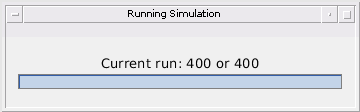

target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    42.8693       NaN       NaN       NaN       NaN
   42.7781       NaN       NaN       NaN       NaN
   42.7082       NaN       NaN       NaN       NaN
   42.8022       NaN       NaN       NaN       NaN
   46.3560       NaN       NaN       NaN       NaN
   42.0553   41.0800       NaN       NaN       NaN
   37.1658       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.8085       NaN       NaN       NaN       NaN
   34.0951       NaN       NaN       NaN       NaN


actual_ranges =    44.0000   44.0667   44.1334   44.2000   44.2667   44.3334   44.4001   44.4668   44.5335   44.6001


estimated_velocities =    -1.9889       NaN       NaN       NaN       NaN
   -1.9891       NaN       NaN       NaN       NaN
   -1.9894       NaN       NaN       NaN       NaN
   -1.9913       NaN       NaN       NaN       NaN
   -1.9866       NaN       NaN       NaN       NaN
   -2.0353  -34.3980       NaN       NaN       NaN
   -2.0029       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0054       NaN       NaN       NaN       NaN
   -2.0006       NaN       NaN       NaN       NaN


actual_velocities =     -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected =      1     1     1     1     1     1     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     1
     0
     1
     1


percent_error_ranges =     1.1307
    1.2886
    1.4252
    1.3979
    2.0893
    2.2782
         0
         0
         0
         0


percent_error_velocities =     0.0111
    0.0109
    0.0106
    0.0087
    0.0134
    0.0353
         0
         0
         0
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    58.3387       NaN       NaN       NaN       NaN
   60.6187       NaN       NaN       NaN       NaN
   59.7837       NaN       NaN       NaN       NaN
   62.0406       NaN       NaN       NaN       NaN
   61.0067       NaN       NaN       NaN       NaN
   59.4641   61.2531       NaN       NaN       NaN
   61.4972       NaN       NaN       NaN       NaN
   53.6533       NaN       NaN       NaN       NaN
   54.1240       NaN       NaN       NaN       NaN
   53.4382       NaN       NaN       NaN       NaN


actual_ranges =    58.0000   58.8002   59.6004   60.4006   61.2008   62.0010   62.8012   63.6014   64.4016   65.2018


estimated_velocities =   -24.0026       NaN       NaN       NaN       NaN
  -23.9940       NaN       NaN       NaN       NaN
  -24.0012       NaN       NaN       NaN       NaN
  -24.0022       NaN       NaN       NaN       NaN
  -24.0006       NaN       NaN       NaN       NaN
   16.5537  -23.9913       NaN       NaN       NaN
  -24.0066       NaN       NaN       NaN       NaN
  -24.0076       NaN       NaN       NaN       NaN
  -23.9863       NaN       NaN       NaN       NaN
  -24.0385       NaN       NaN       NaN       NaN


actual_velocities =    -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected =      1     1     1     1     1     1     1     0     0     0


col_detection =      1
     1
     1
     1
     1
     2
     1
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges =     0.3387
    1.8185
    0.1833
    1.6400
    0.1941
    0.7478
    1.3039
         0
         0
         0


percent_error_velocities =     0.0026
    0.0060
    0.0012
    0.0022
    0.0006
    0.0087
    0.0066
         0
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   138.0189       NaN       NaN       NaN       NaN
  140.3012       NaN       NaN       NaN       NaN
  139.2561       NaN       NaN       NaN       NaN
  141.5639       NaN       NaN       NaN       NaN
  140.6804       NaN       NaN       NaN       NaN
  141.9884       NaN       NaN       NaN       NaN
  142.9444       NaN       NaN       NaN       NaN
  142.8950       NaN       NaN       NaN       NaN
  144.9858       NaN       NaN       NaN       NaN
  145.7099       NaN       NaN       NaN       NaN


actual_ranges =   138.0000  138.7669  139.5337  140.3006  141.0674  141.8343  142.6011  143.3680  144.1348  144.9017


estimated_velocities =   -22.9996       NaN       NaN       NaN       NaN
  -23.0286       NaN       NaN       NaN       NaN
  -23.0117       NaN       NaN       NaN       NaN
  -23.0096       NaN       NaN       NaN       NaN
  -23.0115       NaN       NaN       NaN       NaN
  -23.0111       NaN       NaN       NaN       NaN
  -23.0132       NaN       NaN       NaN       NaN
  -22.9907       NaN       NaN       NaN       NaN
  -23.0389       NaN       NaN       NaN       NaN
  -23.0609       NaN       NaN       NaN       NaN


actual_velocities =    -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0189
    1.5344
    0.2777
    1.2633
    0.3870
    0.1542
    0.3433
    0.4730
    0.8509
    0.8082


percent_error_velocities =     0.0004
    0.0286
    0.0117
    0.0096
    0.0115
    0.0111
    0.0132
    0.0093
    0.0389
    0.0609


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   103.3920       NaN       NaN       NaN       NaN
  104.2779       NaN       NaN       NaN       NaN
  105.0665       NaN       NaN       NaN       NaN
  102.5250       NaN       NaN       NaN       NaN
  102.9652       NaN       NaN       NaN       NaN
  102.7769       NaN       NaN       NaN       NaN
  101.7027       NaN       NaN       NaN       NaN
  100.1815       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =   105.0000  104.4332  103.8664  103.2996  102.7328  102.1660  101.5992  101.0324  100.4656   99.8988


estimated_velocities =    17.0025       NaN       NaN       NaN       NaN
   16.9961       NaN       NaN       NaN       NaN
   17.0127       NaN       NaN       NaN       NaN
   17.0023       NaN       NaN       NaN       NaN
   16.9931       NaN       NaN       NaN       NaN
   16.9200       NaN       NaN       NaN       NaN
   17.0325       NaN       NaN       NaN       NaN
   16.9879       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     17    17    17    17    17    17    17    17    17    17


detected =      1     1     1     1     1     1     1     1     0     0


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     1.6080
    0.1553
    1.2001
    0.7746
    0.2324
    0.6109
    0.1035
    0.8508
         0
         0


percent_error_velocities =     0.0025
    0.0039
    0.0127
    0.0023
    0.0069
    0.0800
    0.0325
    0.0121
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges =    11.0000   10.0331    9.0662    8.0993    7.1324    6.1655    5.1986    4.2317    3.2648    2.2979


estimated_velocities =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities =     29    29    29    29    29    29    29    29    29    29


detected =      0     0     0     0     0     0     0     0     0     0


col_detection =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   124.5723       NaN       NaN       NaN       NaN
  124.0199       NaN       NaN       NaN       NaN
  126.9886       NaN       NaN       NaN       NaN
  126.4942       NaN       NaN       NaN       NaN
  126.2621       NaN       NaN       NaN       NaN
  127.0724       NaN       NaN       NaN       NaN
  126.1738       NaN       NaN       NaN       NaN
  126.5863  125.4849       NaN       NaN       NaN
  129.1436       NaN       NaN       NaN       NaN
  129.3125       NaN       NaN       NaN       NaN


actual_ranges =   125.0000  125.3334  125.6668  126.0002  126.3337  126.6671  127.0005  127.3339  127.6673  128.0007


estimated_velocities =    -9.9805       NaN       NaN       NaN       NaN
   -9.9871       NaN       NaN       NaN       NaN
   -9.9836       NaN       NaN       NaN       NaN
   -9.9892       NaN       NaN       NaN       NaN
   -9.9896       NaN       NaN       NaN       NaN
  -10.0792       NaN       NaN       NaN       NaN
  -10.0271       NaN       NaN       NaN       NaN
   20.2319   -9.9680       NaN       NaN       NaN
   -9.9451       NaN       NaN       NaN       NaN
  -10.0394       NaN       NaN       NaN       NaN


actual_velocities =    -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected =      1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.4277
    1.3135
    1.3218
    0.4939
    0.0716
    0.4053
    0.8267
         0
    1.4762
    1.3118


percent_error_velocities = 10×1
    0.0195
    0.0129
    0.0164
    0.0108
    0.0104
    0.0792
    0.0271
         0
    0.0549
    0.0394


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   33.9601       NaN       NaN       NaN       NaN
   33.7569       NaN       NaN       NaN       NaN
   33.5833       NaN       NaN       NaN       NaN
   33.4144       NaN       NaN       NaN       NaN
   33.0930       NaN       NaN       NaN       NaN
   28.4501       NaN       NaN       NaN       NaN
   31.7643       NaN       NaN       NaN       NaN
   23.8246       NaN       NaN       NaN       NaN
   22.7629       NaN       NaN       NaN       NaN
   34.0026       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   33.0000   33.1667   33.3334   33.5001   33.6668   33.8335   34.0002   34.1670   34.3337   34.5004


estimated_velocities = 10×5
   -4.9970       NaN       NaN       NaN       NaN
   -4.9964       NaN       NaN       NaN       NaN
   -4.9966       NaN       NaN       NaN       NaN
   -4.9967       NaN       NaN       NaN       NaN
   -4.9962       NaN       NaN       NaN       NaN
   -5.0191       NaN       NaN       NaN       NaN
   -5.0240       NaN       NaN       NaN       NaN
   -4.9769       NaN       NaN       NaN       NaN
   -5.0353       NaN       NaN       NaN       NaN
   -4.9972       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.9601
    0.5902
    0.2499
    0.0857
    0.5739
    5.3835
    2.2360
         0
         0
    0.4977


percent_error_velocities = 10×1
    0.0030
    0.0036
    0.0034
    0.0033
    0.0038
    0.0191
    0.0240
         0
         0
    0.0028


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   70.6843       NaN       NaN       NaN       NaN
   70.4756       NaN       NaN       NaN       NaN
   70.2375       NaN       NaN       NaN       NaN
   70.0661       NaN       NaN       NaN       NaN
   69.8804       NaN       NaN       NaN       NaN
   68.4004       NaN       NaN       NaN       NaN
   68.6657       NaN       NaN       NaN       NaN
   68.5876       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   59.5841       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   69.1334   69.2667   69.4001   69.5335   69.6668   69.8002   69.9336   70.0669   70.2003


estimated_velocities = 10×5
   -4.0096       NaN       NaN       NaN       NaN
   -4.0141       NaN       NaN       NaN       NaN
   -4.0146       NaN       NaN       NaN       NaN
   -4.0100       NaN       NaN       NaN       NaN
   -4.0116       NaN       NaN       NaN       NaN
   -4.0387       NaN       NaN       NaN       NaN
   -3.9613       NaN       NaN       NaN       NaN
   -4.0439       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.0295       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.6843
    1.3422
    0.9708
    0.6660
    0.3470
    1.2664
    1.1344
    1.3460
         0
         0


percent_error_velocities = 10×1
    0.0096
    0.0141
    0.0146
    0.0100
    0.0116
    0.0387
    0.0387
    0.0439
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  108.4796       NaN       NaN       NaN       NaN
  109.1784       NaN       NaN       NaN       NaN
  106.5059       NaN       NaN       NaN       NaN
  107.0878       NaN       NaN       NaN       NaN
  108.3608       NaN       NaN       NaN       NaN
  106.8155       NaN       NaN       NaN       NaN
  105.7992       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  109.0000  108.4332  107.8664  107.2996  106.7328  106.1660  105.5992  105.0324  104.4656  103.8988


estimated_velocities = 10×5
   17.0012       NaN       NaN       NaN       NaN
   17.0012       NaN       NaN       NaN       NaN
   17.0057       NaN       NaN       NaN       NaN
   17.0067       NaN       NaN       NaN       NaN
   16.9795       NaN       NaN       NaN       NaN
   17.0508       NaN       NaN       NaN       NaN
   16.9664       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5204
    0.7452
    1.3605
    0.2118
    1.6280
    0.6496
    0.2000
         0
         0
         0


percent_error_velocities = 10×1
    0.0012
    0.0012
    0.0057
    0.0067
    0.0205
    0.0508
    0.0336
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   95.9882       NaN       NaN       NaN       NaN
   97.9808       NaN       NaN       NaN       NaN
   99.8986       NaN       NaN       NaN       NaN
   98.3081       NaN       NaN       NaN       NaN
  100.4813       NaN       NaN       NaN       NaN
   99.8447       NaN       NaN       NaN       NaN
  100.3632  101.8830       NaN       NaN       NaN
  102.3589       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   97.0669   98.1339   99.2008  100.2677  101.3346  102.4016  103.4685  104.5354  105.6023


estimated_velocities = 10×5
  -32.0072       NaN       NaN       NaN       NaN
  -32.0201       NaN       NaN       NaN       NaN
  -32.0200       NaN       NaN       NaN       NaN
  -32.0109       NaN       NaN       NaN       NaN
  -32.0106       NaN       NaN       NaN       NaN
  -32.0619       NaN       NaN       NaN       NaN
   29.9737  -32.0366       NaN       NaN       NaN
  -32.0104       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0118
    0.9139
    1.7647
    0.8927
    0.2136
    1.4899
    0.5185
    1.1096
         0
         0


percent_error_velocities = 10×1
    0.0072
    0.0201
    0.0200
    0.0109
    0.0106
    0.0619
    0.0366
    0.0104
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.5720       NaN       NaN       NaN       NaN
   81.2967       NaN       NaN       NaN       NaN
   80.9367       NaN       NaN       NaN       NaN
   83.7370       NaN       NaN       NaN       NaN
   83.3367       NaN       NaN       NaN       NaN
   82.6424       NaN       NaN       NaN       NaN
   81.5888       NaN       NaN       NaN       NaN
   75.1733       NaN       NaN       NaN       NaN
   73.6793       NaN       NaN       NaN       NaN
   74.6769       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   81.3334   81.6668   82.0002   82.3337   82.6671   83.0005   83.3339   83.6673   84.0007


estimated_velocities = 10×5
   -9.9929       NaN       NaN       NaN       NaN
   -9.9942       NaN       NaN       NaN       NaN
   -9.9936       NaN       NaN       NaN       NaN
   -9.9865       NaN       NaN       NaN       NaN
   -9.9938       NaN       NaN       NaN       NaN
  -10.0091       NaN       NaN       NaN       NaN
  -10.0025       NaN       NaN       NaN       NaN
  -10.0885       NaN       NaN       NaN       NaN
   34.6501       NaN       NaN       NaN       NaN
  -10.0103       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.5720
    0.0367
    0.7301
    1.7367
    1.0030
    0.0247
    1.4117
         0
         0
         0


percent_error_velocities = 10×1
    0.0071
    0.0058
    0.0064
    0.0135
    0.0062
    0.0091
    0.0025
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   40.7245       NaN       NaN       NaN       NaN
   38.6919       NaN       NaN       NaN       NaN
   36.3464       NaN       NaN       NaN       NaN
   37.3182       NaN       NaN       NaN       NaN
   34.7794       NaN       NaN       NaN       NaN
   35.9997       NaN       NaN       NaN       NaN
   29.0646       NaN       NaN       NaN       NaN
   24.8700       NaN       NaN       NaN       NaN
   23.9354       NaN       NaN       NaN       NaN
   21.7013   33.6031       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   39.2331   38.4663   37.6994   36.9326   36.1657   35.3989   34.6320   33.8652   33.0983


estimated_velocities = 10×5
   23.0067       NaN       NaN       NaN       NaN
   23.0139       NaN       NaN       NaN       NaN
   23.0104       NaN       NaN       NaN       NaN
   23.0127       NaN       NaN       NaN       NaN
   23.0138       NaN       NaN       NaN       NaN
   23.0095       NaN       NaN       NaN       NaN
   23.0079       NaN       NaN       NaN       NaN
   22.9641       NaN       NaN       NaN       NaN
   22.9498       NaN       NaN       NaN       NaN
   23.0255   23.0143       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7245
    0.5413
    2.1199
    0.3812
    2.1532
    0.1660
         0
         0
         0
    0.5048


percent_error_velocities = 10×1
    0.0067
    0.0139
    0.0104
    0.0127
    0.0138
    0.0095
         0
         0
         0
    0.0143


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.2809       NaN       NaN       NaN       NaN
   21.8147       NaN       NaN       NaN       NaN
   19.3693       NaN       NaN       NaN       NaN
   20.0301       NaN       NaN       NaN       NaN
   21.0322       NaN       NaN       NaN       NaN
   18.4618       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   22.0000   21.3999   20.7997   20.1996   19.5994   18.9993   18.3991   17.7990   17.1988   16.5987


estimated_velocities = 10×5
   18.0144       NaN       NaN       NaN       NaN
   18.0129       NaN       NaN       NaN       NaN
   18.0141       NaN       NaN       NaN       NaN
   18.0142       NaN       NaN       NaN       NaN
   18.0118       NaN       NaN       NaN       NaN
   18.0091       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7191
    0.4148
    1.4304
    0.1695
    1.4328
    0.5375
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0144
    0.0129
    0.0141
    0.0142
    0.0118
    0.0091
         0
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   29.0748       NaN       NaN       NaN       NaN
   29.1100       NaN       NaN       NaN       NaN
   29.1506       NaN       NaN       NaN       NaN
   29.1925       NaN       NaN       NaN       NaN
   29.2337       NaN       NaN       NaN       NaN
   29.0151       NaN       NaN       NaN       NaN
   22.9396   22.0560       NaN       NaN       NaN
   29.3107       NaN       NaN       NaN       NaN
   29.4614       NaN       NaN       NaN       NaN
   29.6463       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   28.9667   28.9333   28.9000   28.8666   28.8333   28.8000   28.7666   28.7333   28.6999


estimated_velocities = 10×5
    0.9860       NaN       NaN       NaN       NaN
    0.9859       NaN       NaN       NaN       NaN
    0.9860       NaN       NaN       NaN       NaN
    0.9862       NaN       NaN       NaN       NaN
    0.9862       NaN       NaN       NaN       NaN
    0.9769       NaN       NaN       NaN       NaN
    1.0120   -6.9172       NaN       NaN       NaN
    0.9852       NaN       NaN       NaN       NaN
    0.9865       NaN       NaN       NaN       NaN
    0.9884       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0748
    0.1434
    0.2173
    0.2925
    0.3671
    0.1818
    5.8603
    0.5441
    0.7281
    0.9464


percent_error_velocities = 10×1
    0.0140
    0.0141
    0.0140
    0.0138
    0.0138
    0.0231
    0.0120
    0.0148
    0.0135
    0.0116


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   63.1713       NaN       NaN       NaN       NaN
   61.3077       NaN       NaN       NaN       NaN
   62.4856       NaN       NaN       NaN       NaN
   60.4549       NaN       NaN       NaN       NaN
   58.6554       NaN       NaN       NaN       NaN
   56.6074       NaN       NaN       NaN       NaN
   52.5642       NaN       NaN       NaN       NaN
   55.2908       NaN       NaN       NaN       NaN
   46.9377       NaN       NaN       NaN       NaN
   44.5905       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   64.0000   62.9331   61.8661   60.7992   59.7323   58.6654   57.5984   56.5315   55.4646   54.3977


estimated_velocities = 10×5
   32.0118       NaN       NaN       NaN       NaN
   32.0080       NaN       NaN       NaN       NaN
   31.9982       NaN       NaN       NaN       NaN
   32.0103       NaN       NaN       NaN       NaN
   32.0140       NaN       NaN       NaN       NaN
   31.9884       NaN       NaN       NaN       NaN
   32.0270       NaN       NaN       NaN       NaN
   31.9918       NaN       NaN       NaN       NaN
   31.9972       NaN       NaN       NaN       NaN
   31.9908       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.8287
    1.6254
    0.6194
    0.3443
    1.0769
    2.0580
    5.0343
    1.2408
         0
         0


percent_error_velocities = 10×1
    0.0118
    0.0080
    0.0018
    0.0103
    0.0140
    0.0116
    0.0270
    0.0082
         0
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   69.1185       NaN       NaN       NaN       NaN
   69.0492       NaN       NaN       NaN       NaN
   68.9383       NaN       NaN       NaN       NaN
   68.8689       NaN       NaN       NaN       NaN
   68.8067       NaN       NaN       NaN       NaN
   66.1308       NaN       NaN       NaN       NaN
   64.7916       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   60.3069       NaN       NaN       NaN       NaN
   59.6302       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   70.0000   70.0333   70.0667   70.1000   70.1334   70.1667   70.2000   70.2334   70.2667   70.3001


estimated_velocities = 10×5
   -0.9867       NaN       NaN       NaN       NaN
   -0.9921       NaN       NaN       NaN       NaN
   -0.9883       NaN       NaN       NaN       NaN
   -0.9839       NaN       NaN       NaN       NaN
   -0.9825       NaN       NaN       NaN       NaN
   -1.0338       NaN       NaN       NaN       NaN
   -1.0592       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -1.0928       NaN       NaN       NaN       NaN
   -1.0369       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.8815
    0.9842
    1.1284
    1.2311
    1.3267
    4.0359
    5.4085
         0
         0
         0


percent_error_velocities = 10×1
    0.0133
    0.0079
    0.0117
    0.0161
    0.0175
    0.0338
    0.0592
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  131.5748       NaN       NaN       NaN       NaN
  130.9375       NaN       NaN       NaN       NaN
  130.6150       NaN       NaN       NaN       NaN
  130.3996       NaN       NaN       NaN       NaN
  129.6386       NaN       NaN       NaN       NaN
  130.7812       NaN       NaN       NaN       NaN
  132.2451       NaN       NaN       NaN       NaN
  132.3464       NaN       NaN       NaN       NaN
  133.0513  133.0816       NaN       NaN       NaN
  133.7543  134.0413       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  130.3001  130.6001  130.9002  131.2003  131.5004  131.8004  132.1005  132.4006  132.7007


estimated_velocities = 10×5
   -9.0066       NaN       NaN       NaN       NaN
   -9.0141       NaN       NaN       NaN       NaN
   -9.0098       NaN       NaN       NaN       NaN
   -9.0052       NaN       NaN       NaN       NaN
   -9.0110       NaN       NaN       NaN       NaN
   -8.9796       NaN       NaN       NaN       NaN
   -8.9962       NaN       NaN       NaN       NaN
   -9.0143       NaN       NaN       NaN       NaN
   -8.9544   23.6479       NaN       NaN       NaN
   -9.0649  -27.1101       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.5748
    0.6374
    0.0148
    0.5006
    1.5617
    0.7192
    0.4447
    0.2459
    0.6507
    1.0537


percent_error_velocities = 10×1
    0.0066
    0.0141
    0.0098
    0.0052
    0.0110
    0.0204
    0.0038
    0.0143
    0.0456
    0.0649


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.5021       NaN       NaN       NaN       NaN
  133.1547       NaN       NaN       NaN       NaN
  130.8278       NaN       NaN       NaN       NaN
  131.9386       NaN       NaN       NaN       NaN
  129.0501       NaN       NaN       NaN       NaN
  131.0547       NaN       NaN       NaN       NaN
  131.4716  131.1079       NaN       NaN       NaN
  129.1130       NaN       NaN       NaN       NaN
  130.1172       NaN       NaN       NaN       NaN
  129.0298       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.2998  132.5997  131.8995  131.1993  130.4991  129.7990  129.0988  128.3986  127.6985


estimated_velocities = 10×5
   20.9910       NaN       NaN       NaN       NaN
   20.9941       NaN       NaN       NaN       NaN
   20.9948       NaN       NaN       NaN       NaN
   21.0040       NaN       NaN       NaN       NaN
   20.9806       NaN       NaN       NaN       NaN
   20.9959       NaN       NaN       NaN       NaN
   20.9602  -30.9765       NaN       NaN       NaN
   20.9978       NaN       NaN       NaN       NaN
   20.9348       NaN       NaN       NaN       NaN
   20.9630       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.4979
    0.1451
    1.7718
    0.0391
    2.1492
    0.5555
    1.6726
    0.0142
    1.7186
    1.3314


percent_error_velocities = 10×1
    0.0090
    0.0059
    0.0052
    0.0040
    0.0194
    0.0041
    0.0398
    0.0022
    0.0652
    0.0370


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   36.2603       NaN       NaN       NaN       NaN
   34.0750       NaN       NaN       NaN       NaN
   34.8590       NaN       NaN       NaN       NaN
   32.6556       NaN       NaN       NaN       NaN
   34.0294       NaN       NaN       NaN       NaN
   26.7309       NaN       NaN       NaN       NaN
   27.6874       NaN       NaN       NaN       NaN
   29.6256       NaN       NaN       NaN       NaN
   19.6473       NaN       NaN       NaN       NaN
   29.5153       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   35.1998   34.3996   33.5994   32.7992   31.9990   31.1988   30.3986   29.5984   28.7982


estimated_velocities = 10×5
   23.9999       NaN       NaN       NaN       NaN
   23.9996       NaN       NaN       NaN       NaN
   23.9971       NaN       NaN       NaN       NaN
   24.0014       NaN       NaN       NaN       NaN
   23.9988       NaN       NaN       NaN       NaN
   24.0119       NaN       NaN       NaN       NaN
   24.0035       NaN       NaN       NaN       NaN
   23.9950       NaN       NaN       NaN       NaN
   23.9522       NaN       NaN       NaN       NaN
   23.9934       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.2603
    1.1248
    0.4594
    0.9438
    1.2302
    5.2681
    3.5114
    0.7731
         0
    0.7171


percent_error_velocities = 10×1
    0.0001
    0.0004
    0.0029
    0.0014
    0.0012
    0.0119
    0.0035
    0.0050
         0
    0.0066


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  102.2285       NaN       NaN       NaN       NaN
   99.6688       NaN       NaN       NaN       NaN
  100.6815       NaN       NaN       NaN       NaN
   98.2232       NaN       NaN       NaN       NaN
   98.9708       NaN       NaN       NaN       NaN
   96.6928       NaN       NaN       NaN       NaN
   94.7600       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.2665   99.5330   98.7995   98.0660   97.3324   96.5989   95.8654   95.1319   94.3984


estimated_velocities = 10×5
   21.9619       NaN       NaN       NaN       NaN
   22.0025       NaN       NaN       NaN       NaN
   22.0101       NaN       NaN       NaN       NaN
   22.0045       NaN       NaN       NaN       NaN
   22.0191       NaN       NaN       NaN       NaN
   21.9606       NaN       NaN       NaN       NaN
   21.9431       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2285
    0.5977
    1.1485
    0.5763
    0.9048
    0.6397
    1.8389
         0
         0
         0


percent_error_velocities = 10×1
    0.0381
    0.0025
    0.0101
    0.0045
    0.0191
    0.0394
    0.0569
         0
         0
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   83.9137       NaN       NaN       NaN       NaN
   85.1858       NaN       NaN       NaN       NaN
   82.0249       NaN       NaN       NaN       NaN
   82.7517       NaN       NaN       NaN       NaN
   79.4796       NaN       NaN       NaN       NaN
   77.7087   80.2699       NaN       NaN       NaN
   76.4996       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   70.1610       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   83.4999   82.9998   82.4996   81.9995   81.4994   80.9993   80.4991   79.9990   79.4989


estimated_velocities = 10×5
   14.9890       NaN       NaN       NaN       NaN
   14.9873       NaN       NaN       NaN       NaN
   14.9925       NaN       NaN       NaN       NaN
   14.9889       NaN       NaN       NaN       NaN
   14.9908       NaN       NaN       NaN       NaN
   14.9674   -1.2238       NaN       NaN       NaN
   14.9405       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   14.9237       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0863
    1.6859
    0.9748
    0.2521
    2.5199
    3.7907
    4.4997
         0
         0
         0


percent_error_velocities = 10×1
    0.0110
    0.0127
    0.0075
    0.0111
    0.0092
    0.0326
    0.0595
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  109.2039       NaN       NaN       NaN       NaN
  113.2005       NaN       NaN       NaN       NaN
  113.1766       NaN       NaN       NaN       NaN
  113.2153       NaN       NaN       NaN       NaN
  113.2134       NaN       NaN       NaN       NaN
  109.7062       NaN       NaN       NaN       NaN
  110.4067       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   111   111   111   111   111   111   111   111   111   111


estimated_velocities = 10×5
   -0.0066       NaN       NaN       NaN       NaN
   -0.0088       NaN       NaN       NaN       NaN
    0.0350       NaN       NaN       NaN       NaN
    0.0030       NaN       NaN       NaN       NaN
    0.0100       NaN       NaN       NaN       NaN
   -0.0426       NaN       NaN       NaN       NaN
   -0.0374       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.7961
    2.2005
    2.1766
    2.2153
    2.2134
    1.2938
    0.5933
         0
         0
         0


percent_error_velocities = 10×1
    0.0066
    0.0088
    0.0350
    0.0030
    0.0100
    0.0426
    0.0374
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   68.7542       NaN       NaN       NaN       NaN
   70.8899       NaN       NaN       NaN       NaN
   69.6758       NaN       NaN       NaN       NaN
   71.6115       NaN       NaN       NaN       NaN
   73.5848       NaN       NaN       NaN       NaN
   71.9868       NaN       NaN       NaN       NaN
   73.8610       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   65.5041       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   68.0000   69.0002   70.0005   71.0007   72.0010   73.0012   74.0015   75.0017   76.0020   77.0022


estimated_velocities = 10×5
  -29.9834       NaN       NaN       NaN       NaN
  -29.9834       NaN       NaN       NaN       NaN
  -29.9755       NaN       NaN       NaN       NaN
  -29.9828       NaN       NaN       NaN       NaN
  -29.9755       NaN       NaN       NaN       NaN
  -30.0740       NaN       NaN       NaN       NaN
  -30.0214       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -29.9668       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.7542
    1.8897
    0.3247
    0.6108
    1.5838
    1.0145
    0.1404
         0
         0
         0


percent_error_velocities = 10×1
    0.0166
    0.0166
    0.0245
    0.0172
    0.0245
    0.0740
    0.0214
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   31.6462       NaN       NaN       NaN       NaN
   33.8976       NaN       NaN       NaN       NaN
   32.0751       NaN       NaN       NaN       NaN
   34.0285       NaN       NaN       NaN       NaN
   35.9157       NaN       NaN       NaN       NaN
   33.4898       NaN       NaN       NaN       NaN
   28.3710       NaN       NaN       NaN       NaN
   37.9649       NaN       NaN       NaN       NaN
   27.1055       NaN       NaN       NaN       NaN
   27.8765       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   31.1003   32.2005   33.3008   34.4011   35.5013   36.6016   37.7019   38.8021   39.9024


estimated_velocities = 10×5
  -33.0097       NaN       NaN       NaN       NaN
  -33.0078       NaN       NaN       NaN       NaN
  -33.0084       NaN       NaN       NaN       NaN
  -33.0092       NaN       NaN       NaN       NaN
  -33.0097       NaN       NaN       NaN       NaN
  -33.0114       NaN       NaN       NaN       NaN
  -33.0745       NaN       NaN       NaN       NaN
  -33.0114       NaN       NaN       NaN       NaN
  -33.0036       NaN       NaN       NaN       NaN
  -33.0131       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     0     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    1.6462
    2.7974
    0.1254
    0.7277
    1.5146
    2.0115
         0
    0.2630
         0
         0


percent_error_velocities = 10×1
    0.0097
    0.0078
    0.0084
    0.0092
    0.0097
    0.0114
         0
    0.0114
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   40.2683       NaN       NaN       NaN       NaN
   40.3160       NaN       NaN       NaN       NaN
   40.3555       NaN       NaN       NaN       NaN
   40.3859       NaN       NaN       NaN       NaN
   40.4258       NaN       NaN       NaN       NaN
   40.1412   38.3181       NaN       NaN       NaN
   38.5049       NaN       NaN       NaN       NaN
   31.2936       NaN       NaN       NaN       NaN
   30.4153       NaN       NaN       NaN       NaN
   29.6631       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   40.9667   40.9333   40.9000   40.8666   40.8333   40.8000   40.7666   40.7333   40.6999


estimated_velocities = 10×5
    0.9874       NaN       NaN       NaN       NaN
    0.9862       NaN       NaN       NaN       NaN
    0.9855       NaN       NaN       NaN       NaN
    0.9861       NaN       NaN       NaN       NaN
    0.9860       NaN       NaN       NaN       NaN
    0.9573   -5.7712       NaN       NaN       NaN
    0.9515       NaN       NaN       NaN       NaN
    0.9861       NaN       NaN       NaN       NaN
    0.9834       NaN       NaN       NaN       NaN
    0.9672       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.7317
    0.6507
    0.5778
    0.5141
    0.4408
    0.6921
    2.2951
         0
         0
         0


percent_error_velocities = 10×1
    0.0126
    0.0138
    0.0145
    0.0139
    0.0140
    0.0427
    0.0485
         0
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   44.2461       NaN       NaN       NaN       NaN
   41.0037       NaN       NaN       NaN       NaN
   41.7147       NaN       NaN       NaN       NaN
   42.1673       NaN       NaN       NaN       NaN
   42.7348       NaN       NaN       NaN       NaN
   39.4803       NaN       NaN       NaN       NaN
   34.3429   33.9162       NaN       NaN       NaN
   31.1155       NaN       NaN       NaN       NaN
   30.3252       NaN       NaN       NaN       NaN
   38.4004   28.0100       NaN       NaN       NaN


actual_ranges = 1×10
   43.0000   42.6332   42.2665   41.8997   41.5330   41.1662   40.7995   40.4327   40.0660   39.6992


estimated_velocities = 10×5
   10.9844       NaN       NaN       NaN       NaN
   10.9798       NaN       NaN       NaN       NaN
   10.9841       NaN       NaN       NaN       NaN
   10.9825       NaN       NaN       NaN       NaN
   10.9817       NaN       NaN       NaN       NaN
   10.9813       NaN       NaN       NaN       NaN
   11.0244  -34.3908       NaN       NaN       NaN
   11.0002       NaN       NaN       NaN       NaN
   10.9685       NaN       NaN       NaN       NaN
   10.9825   10.9793       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.2461
    1.6296
    0.5518
    0.2675
    1.2018
    1.6859
         0
         0
         0
    1.2988


percent_error_velocities = 10×1
    0.0156
    0.0202
    0.0159
    0.0175
    0.0183
    0.0187
         0
         0
         0
    0.0175


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.2830       NaN       NaN       NaN       NaN
   21.8120       NaN       NaN       NaN       NaN
   19.3693       NaN       NaN       NaN       NaN
   20.0314       NaN       NaN       NaN       NaN
   21.0315       NaN       NaN       NaN       NaN
   18.4405       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   22.0000   21.3999   20.7997   20.1996   19.5994   18.9993   18.3991   17.7990   17.1988   16.5987


estimated_velocities = 10×5
   18.0142       NaN       NaN       NaN       NaN
   18.0126       NaN       NaN       NaN       NaN
   18.0138       NaN       NaN       NaN       NaN
   18.0143       NaN       NaN       NaN       NaN
   18.0117       NaN       NaN       NaN       NaN
   18.0134       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7170
    0.4121
    1.4305
    0.1682
    1.4321
    0.5588
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0142
    0.0126
    0.0138
    0.0143
    0.0117
    0.0134
         0
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.2116       NaN       NaN       NaN       NaN
   80.0912       NaN       NaN       NaN       NaN
   82.1456       NaN       NaN       NaN       NaN
   81.1884       NaN       NaN       NaN       NaN
   83.3451       NaN       NaN       NaN       NaN
   81.7016       NaN       NaN       NaN       NaN
   79.0851       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   76.1320       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   79.8669   80.7338   81.6006   82.4675   83.3344   84.2013   85.0681   85.9350   86.8019


estimated_velocities = 10×5
  -25.9672       NaN       NaN       NaN       NaN
  -25.9810       NaN       NaN       NaN       NaN
  -25.9828       NaN       NaN       NaN       NaN
  -25.9860       NaN       NaN       NaN       NaN
  -25.9853       NaN       NaN       NaN       NaN
  -26.0043       NaN       NaN       NaN       NaN
  -25.9882       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -26.0793       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.2116
    0.2243
    1.4119
    0.4122
    0.8776
    1.6328
    5.1162
         0
         0
         0


percent_error_velocities = 10×1
    0.0328
    0.0190
    0.0172
    0.0140
    0.0147
    0.0043
    0.0118
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   27.1473       NaN       NaN       NaN       NaN
   27.2017       NaN       NaN       NaN       NaN
   27.2494       NaN       NaN       NaN       NaN
   27.2991       NaN       NaN       NaN       NaN
   27.3450       NaN       NaN       NaN       NaN
   27.9430       NaN       NaN       NaN       NaN
   26.8363       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   27.9667   27.9333   27.9000   27.8666   27.8333   27.8000   27.7666   27.7333   27.6999


estimated_velocities = 10×5
    0.9855       NaN       NaN       NaN       NaN
    0.9855       NaN       NaN       NaN       NaN
    0.9859       NaN       NaN       NaN       NaN
    0.9861       NaN       NaN       NaN       NaN
    0.9857       NaN       NaN       NaN       NaN
    1.0129       NaN       NaN       NaN       NaN
    0.9767       NaN       NaN       NaN       NaN
    0.9929       NaN       NaN       NaN       NaN
    0.9975       NaN       NaN       NaN       NaN
   -5.5727       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.8527
    0.7649
    0.6840
    0.6008
    0.5216
    0.1097
    0.9637
         0
         0
         0


percent_error_velocities = 10×1
    0.0145
    0.0145
    0.0141
    0.0139
    0.0143
    0.0129
    0.0233
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  121.0950       NaN       NaN       NaN       NaN
  120.6852       NaN       NaN       NaN       NaN
  120.3481       NaN       NaN       NaN       NaN
  120.0615       NaN       NaN       NaN       NaN
  119.7033       NaN       NaN       NaN       NaN
  120.8987  120.3772       NaN       NaN       NaN
  121.0214       NaN       NaN       NaN       NaN
  121.5667       NaN       NaN       NaN       NaN
  122.2215       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  120.0000  120.2334  120.4668  120.7002  120.9336  121.1670  121.4003  121.6337  121.8671  122.1005


estimated_velocities = 10×5
   -7.0116       NaN       NaN       NaN       NaN
   -6.9916       NaN       NaN       NaN       NaN
   -7.0076       NaN       NaN       NaN       NaN
   -7.0011       NaN       NaN       NaN       NaN
   -6.9926       NaN       NaN       NaN       NaN
   15.5320   -7.0375       NaN       NaN       NaN
   -6.9801       NaN       NaN       NaN       NaN
   -7.0538       NaN       NaN       NaN       NaN
   -6.9884       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0950
    0.4518
    0.1186
    0.6386
    1.2303
         0
    0.3790
    0.0670
    0.3544
         0


percent_error_velocities = 10×1
    0.0116
    0.0084
    0.0076
    0.0011
    0.0074
         0
    0.0199
    0.0538
    0.0116
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.1251       NaN       NaN       NaN       NaN
  100.6039       NaN       NaN       NaN       NaN
   97.5196       NaN       NaN       NaN       NaN
   98.2037       NaN       NaN       NaN       NaN
   98.4770       NaN       NaN       NaN       NaN
   98.5279       NaN       NaN       NaN       NaN
   97.1973       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.1436       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000   99.6666   99.3332   98.9998   98.6663   98.3329   97.9995   97.6661   97.3327   96.9993


estimated_velocities = 10×5
    9.9935       NaN       NaN       NaN       NaN
    9.9971       NaN       NaN       NaN       NaN
    9.9984       NaN       NaN       NaN       NaN
    9.9981       NaN       NaN       NaN       NaN
    9.9961       NaN       NaN       NaN       NaN
    9.9713       NaN       NaN       NaN       NaN
   10.0205       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.9762       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1251
    0.9373
    1.8136
    0.7961
    0.1894
    0.1949
    0.8022
         0
         0
         0


percent_error_velocities = 10×1
    0.0065
    0.0029
    0.0016
    0.0019
    0.0039
    0.0287
    0.0205
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   60.2658       NaN       NaN       NaN       NaN
   58.3229       NaN       NaN       NaN       NaN
   59.8589       NaN       NaN       NaN       NaN
   57.6857       NaN       NaN       NaN       NaN
   55.7779       NaN       NaN       NaN       NaN
   53.8703       NaN       NaN       NaN       NaN
   54.7838       NaN       NaN       NaN       NaN
   46.2195       NaN       NaN       NaN       NaN
   43.7579       NaN       NaN       NaN       NaN
   41.4879       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   59.9664   58.9328   57.8992   56.8657   55.8321   54.7985   53.7649   52.7313   51.6977


estimated_velocities = 10×5
   30.9891       NaN       NaN       NaN       NaN
   30.9875       NaN       NaN       NaN       NaN
   30.9891       NaN       NaN       NaN       NaN
   30.9859       NaN       NaN       NaN       NaN
   30.9865       NaN       NaN       NaN       NaN
   30.9565       NaN       NaN       NaN       NaN
   30.9756       NaN       NaN       NaN       NaN
   30.9598       NaN       NaN       NaN       NaN
   30.9401       NaN       NaN       NaN       NaN
   30.9894       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.7342
    1.6435
    0.9261
    0.2136
    1.0878
    1.9617
    0.0147
         0
         0
         0


percent_error_velocities = 10×1
    0.0109
    0.0125
    0.0109
    0.0141
    0.0135
    0.0435
    0.0244
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  124.6890       NaN       NaN       NaN       NaN
  127.1360       NaN       NaN       NaN       NaN
  126.2802       NaN       NaN       NaN       NaN
  128.6552       NaN       NaN       NaN       NaN
  127.8358       NaN       NaN       NaN       NaN
  127.8958       NaN       NaN       NaN       NaN
  129.9130       NaN       NaN       NaN       NaN
  129.6490  129.0437       NaN       NaN       NaN
  131.6142       NaN       NaN       NaN       NaN
  132.4133       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  125.7335  126.4670  127.2005  127.9340  128.6676  129.4011  130.1346  130.8681  131.6016


estimated_velocities = 10×5
  -22.0083       NaN       NaN       NaN       NaN
  -21.9992       NaN       NaN       NaN       NaN
  -22.0080       NaN       NaN       NaN       NaN
  -21.9907       NaN       NaN       NaN       NaN
  -22.0071       NaN       NaN       NaN       NaN
  -22.0159       NaN       NaN       NaN       NaN
  -22.0291       NaN       NaN       NaN       NaN
    6.3512  -22.0068       NaN       NaN       NaN
  -21.9459       NaN       NaN       NaN       NaN
  -22.0640       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.3110
    1.4025
    0.1868
    1.4547
    0.0983
    0.7717
    0.5119
         0
    0.7461
    0.8117


percent_error_velocities = 10×1
    0.0083
    0.0008
    0.0080
    0.0093
    0.0071
    0.0159
    0.0291
         0
    0.0541
    0.0640


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.6718       NaN       NaN       NaN       NaN
  101.4815       NaN       NaN       NaN       NaN
   99.0125       NaN       NaN       NaN       NaN
  100.1181       NaN       NaN       NaN       NaN
   97.7279       NaN       NaN       NaN       NaN
   98.4367       NaN       NaN       NaN       NaN
   99.1758       NaN       NaN       NaN       NaN
   96.4849       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  101.2998  100.5997   99.8995   99.1993   98.4991   97.7990   97.0988   96.3986   95.6985


estimated_velocities = 10×5
   20.9819       NaN       NaN       NaN       NaN
   20.9838       NaN       NaN       NaN       NaN
   20.9845       NaN       NaN       NaN       NaN
   20.9801       NaN       NaN       NaN       NaN
   20.9841       NaN       NaN       NaN       NaN
   21.0142       NaN       NaN       NaN       NaN
   20.9987       NaN       NaN       NaN       NaN
   20.9679       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.3282
    0.1816
    1.5871
    0.2186
    1.4714
    0.0624
    1.3768
    0.6139
         0
         0


percent_error_velocities = 10×1
    0.0181
    0.0162
    0.0155
    0.0199
    0.0159
    0.0142
    0.0013
    0.0321
         0
         0


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   77.1895       NaN       NaN       NaN       NaN
   79.2126       NaN       NaN       NaN       NaN
   77.5941       NaN       NaN       NaN       NaN
   80.1203       NaN       NaN       NaN       NaN
   82.0061       NaN       NaN       NaN       NaN
   79.7518       NaN       NaN       NaN       NaN
   78.3212       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   74.6684       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   77.0000   77.9669   78.9338   79.9007   80.8676   81.8345   82.8014   83.7683   84.7352   85.7021


estimated_velocities = 10×5
  -28.9937       NaN       NaN       NaN       NaN
  -28.9933       NaN       NaN       NaN       NaN
  -29.0009       NaN       NaN       NaN       NaN
  -28.9934       NaN       NaN       NaN       NaN
  -28.9988       NaN       NaN       NaN       NaN
  -29.0497       NaN       NaN       NaN       NaN
  -29.1133       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -29.0193       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1895
    1.2457
    1.3397
    0.2195
    1.1385
    2.0827
    4.4802
         0
         0
         0


percent_error_velocities = 10×1
    0.0063
    0.0067
    0.0009
    0.0066
    0.0012
    0.0497
    0.1133
         0
         0
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.8296       NaN       NaN       NaN       NaN
   82.0151       NaN       NaN       NaN       NaN
   81.1592       NaN       NaN       NaN       NaN
   83.3811       NaN       NaN       NaN       NaN
   82.1216       NaN       NaN       NaN       NaN
   83.5262       NaN       NaN       NaN       NaN
   82.6983       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   77.3580       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   80.8002   81.6004   82.4006   83.2008   84.0010   84.8012   85.6014   86.4016   87.2018


estimated_velocities = 10×5
  -24.0032       NaN       NaN       NaN       NaN
  -23.9971       NaN       NaN       NaN       NaN
  -23.9936       NaN       NaN       NaN       NaN
  -24.0030       NaN       NaN       NaN       NaN
  -23.9959       NaN       NaN       NaN       NaN
  -23.9902       NaN       NaN       NaN       NaN
  -24.0306       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -24.0101       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1704
    1.2149
    0.4411
    0.9805
    1.0791
    0.4747
    2.1028
         0
         0
         0


percent_error_velocities = 10×1
    0.0032
    0.0029
    0.0064
    0.0030
    0.0041
    0.0098
    0.0306
         0
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  129.2758       NaN       NaN       NaN       NaN
  129.1067       NaN       NaN       NaN       NaN
  129.0008       NaN       NaN       NaN       NaN
  128.9017       NaN       NaN       NaN       NaN
  128.7254       NaN       NaN       NaN       NaN
  130.2114       NaN       NaN       NaN       NaN
  129.8827       NaN       NaN       NaN       NaN
  129.7363       NaN       NaN       NaN       NaN
  130.1318       NaN       NaN       NaN       NaN
  130.7328       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  129.1000  129.2000  129.3001  129.4001  129.5001  129.6001  129.7002  129.8002  129.9002


estimated_velocities = 10×5
   -3.0130       NaN       NaN       NaN       NaN
   -3.0170       NaN       NaN       NaN       NaN
   -3.0105       NaN       NaN       NaN       NaN
   -3.0237       NaN       NaN       NaN       NaN
   -3.0127       NaN       NaN       NaN       NaN
   -3.0470       NaN       NaN       NaN       NaN
   -3.0948       NaN       NaN       NaN       NaN
   -2.9902       NaN       NaN       NaN       NaN
   -2.9789       NaN       NaN       NaN       NaN
   -3.0036       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2758
    0.0067
    0.1992
    0.3984
    0.6747
    0.7113
    0.2825
    0.0361
    0.3316
    0.8326


percent_error_velocities = 10×1
    0.0130
    0.0170
    0.0105
    0.0237
    0.0127
    0.0470
    0.0948
    0.0098
    0.0211
    0.0036


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   60.3991       NaN       NaN       NaN       NaN
   59.4753       NaN       NaN       NaN       NaN
   61.4741       NaN       NaN       NaN       NaN
   63.3341       NaN       NaN       NaN       NaN
   62.1688       NaN       NaN       NaN       NaN
   59.4000   59.3472       NaN       NaN       NaN
   63.8917       NaN       NaN       NaN       NaN
   56.7118       NaN       NaN       NaN       NaN
   66.0200   57.2262       NaN       NaN       NaN
   56.4321       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   60.0002   61.0005   62.0007   63.0010   64.0012   65.0015   66.0017   67.0020   68.0022


estimated_velocities = 10×5
  -29.9818       NaN       NaN       NaN       NaN
  -29.9778       NaN       NaN       NaN       NaN
  -29.9853       NaN       NaN       NaN       NaN
  -29.9828       NaN       NaN       NaN       NaN
  -29.9796       NaN       NaN       NaN       NaN
  -18.3661  -29.9562       NaN       NaN       NaN
  -29.9823       NaN       NaN       NaN       NaN
  -29.9960       NaN       NaN       NaN       NaN
   -4.9774   -4.9755       NaN       NaN       NaN
  -29.9965       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.3991
    0.5249
    0.4736
    1.3333
    0.8322
         0
    1.1097
         0
         0
         0


percent_error_velocities = 10×1
    0.0182
    0.0222
    0.0147
    0.0172
    0.0204
         0
    0.0177
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  129.7410       NaN       NaN       NaN       NaN
  130.7107       NaN       NaN       NaN       NaN
  128.4928       NaN       NaN       NaN       NaN
  129.5815       NaN       NaN       NaN       NaN
  127.0994       NaN       NaN       NaN       NaN
  128.5409       NaN       NaN       NaN       NaN
  127.3861       NaN       NaN       NaN       NaN
  126.3494       NaN       NaN       NaN       NaN
  125.8063       NaN       NaN       NaN       NaN
  126.1947       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  130.1998  129.3996  128.5994  127.7992  126.9990  126.1988  125.3986  124.5984  123.7982


estimated_velocities = 10×5
   24.0007       NaN       NaN       NaN       NaN
   24.0070       NaN       NaN       NaN       NaN
   24.0036       NaN       NaN       NaN       NaN
   24.0191       NaN       NaN       NaN       NaN
   24.0040       NaN       NaN       NaN       NaN
   23.8853       NaN       NaN       NaN       NaN
   24.0019       NaN       NaN       NaN       NaN
   24.0141       NaN       NaN       NaN       NaN
   24.0051       NaN       NaN       NaN       NaN
   24.0070       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2590
    0.5109
    0.9068
    0.9821
    0.6998
    1.5419
    1.1873
    0.9508
    1.2079
    2.3965


percent_error_velocities = 10×1
    0.0007
    0.0070
    0.0036
    0.0191
    0.0040
    0.1147
    0.0019
    0.0141
    0.0051
    0.0070


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   60.3065       NaN       NaN       NaN       NaN
   58.2167       NaN       NaN       NaN       NaN
   59.7308       NaN       NaN       NaN       NaN
   57.5652       NaN       NaN       NaN       NaN
   55.4777       NaN       NaN       NaN       NaN
   53.1950   54.6621       NaN       NaN       NaN
   49.0647       NaN       NaN       NaN       NaN
   52.6380       NaN       NaN       NaN       NaN
   43.6350       NaN       NaN       NaN       NaN
   51.8479       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   60.0331   59.0662   58.0993   57.1324   56.1655   55.1986   54.2317   53.2648   52.2979


estimated_velocities = 10×5
   28.9960       NaN       NaN       NaN       NaN
   28.9958       NaN       NaN       NaN       NaN
   29.0024       NaN       NaN       NaN       NaN
   29.0004       NaN       NaN       NaN       NaN
   28.9966       NaN       NaN       NaN       NaN
   28.9423  -32.1921       NaN       NaN       NaN
   28.9449       NaN       NaN       NaN       NaN
   29.0023       NaN       NaN       NaN       NaN
   28.9982       NaN       NaN       NaN       NaN
   28.9951       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.6935
    1.8164
    0.6646
    0.5341
    1.6547
    2.9705
    6.1339
    1.5937
         0
    0.4500


percent_error_velocities = 10×1
    0.0040
    0.0042
    0.0024
    0.0004
    0.0034
    0.0577
    0.0551
    0.0023
         0
    0.0049


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   61.0971       NaN       NaN       NaN       NaN
   62.2695       NaN       NaN       NaN       NaN
   60.5973       NaN       NaN       NaN       NaN
   58.8979       NaN       NaN       NaN       NaN
   57.3089       NaN       NaN       NaN       NaN
   58.9247   55.3021       NaN       NaN       NaN
   51.8232   50.2733       NaN       NaN       NaN
   46.0849       NaN       NaN       NaN       NaN
   45.4145       NaN       NaN       NaN       NaN
   43.1003       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   63.0000   61.8330   60.6661   59.4991   58.3322   57.1652   55.9983   54.8313   53.6644   52.4974


estimated_velocities = 10×5
   34.9778       NaN       NaN       NaN       NaN
   34.9715       NaN       NaN       NaN       NaN
   34.9777       NaN       NaN       NaN       NaN
   34.9840       NaN       NaN       NaN       NaN
   34.9833       NaN       NaN       NaN       NaN
   34.9680    2.7511       NaN       NaN       NaN
  -12.7804   34.9648       NaN       NaN       NaN
   34.9838       NaN       NaN       NaN       NaN
   35.0161       NaN       NaN       NaN       NaN
   35.0149       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9029
    0.4364
    0.0688
    0.6012
    1.0233
    1.7595
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0222
    0.0285
    0.0223
    0.0160
    0.0167
    0.0320
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  139.3156       NaN       NaN       NaN       NaN
  136.6320       NaN       NaN       NaN       NaN
  137.3289       NaN       NaN       NaN       NaN
  138.3337       NaN       NaN       NaN       NaN
  135.3558       NaN       NaN       NaN       NaN
  136.9478       NaN       NaN       NaN       NaN
  136.5304       NaN       NaN       NaN       NaN
  134.7040       NaN       NaN       NaN       NaN
  135.6704       NaN       NaN       NaN       NaN
  136.6007       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  139.0000  138.4665  137.9331  137.3996  136.8661  136.3327  135.7992  135.2658  134.7323  134.1988


estimated_velocities = 10×5
   15.9942       NaN       NaN       NaN       NaN
   15.9984       NaN       NaN       NaN       NaN
   15.9889       NaN       NaN       NaN       NaN
   15.9675       NaN       NaN       NaN       NaN
   15.9923       NaN       NaN       NaN       NaN
   16.0277       NaN       NaN       NaN       NaN
   16.0048       NaN       NaN       NaN       NaN
   15.9834       NaN       NaN       NaN       NaN
   15.9550       NaN       NaN       NaN       NaN
   15.9555       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3156
    1.8345
    0.6041
    0.9341
    1.5104
    0.6151
    0.7312
    0.5618
    0.9381
    2.4019


percent_error_velocities = 10×1
    0.0058
    0.0016
    0.0111
    0.0325
    0.0077
    0.0277
    0.0048
    0.0166
    0.0450
    0.0445


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  142.1879       NaN       NaN       NaN       NaN
  142.7566       NaN       NaN       NaN       NaN
  143.3443       NaN       NaN       NaN       NaN
  139.6503       NaN       NaN       NaN       NaN
  140.2922       NaN       NaN       NaN       NaN
  141.4436       NaN       NaN       NaN       NaN
  142.4713       NaN       NaN       NaN       NaN
  141.2411       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  142.7854       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  141.7666  141.5332  141.2998  141.0664  140.8330  140.5997  140.3663  140.1329  139.8995


estimated_velocities = 10×5
    6.9866       NaN       NaN       NaN       NaN
    6.9969       NaN       NaN       NaN       NaN
    7.0001       NaN       NaN       NaN       NaN
    6.9898       NaN       NaN       NaN       NaN
    6.9878       NaN       NaN       NaN       NaN
    6.9696       NaN       NaN       NaN       NaN
    7.0269       NaN       NaN       NaN       NaN
    6.9383       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9616       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1879
    0.9900
    1.8111
    1.6496
    0.7742
    0.6105
    1.8716
    0.8749
         0
    2.8859


percent_error_velocities = 10×1
    0.0134
    0.0031
    0.0001
    0.0102
    0.0122
    0.0304
    0.0269
    0.0617
         0
    0.0384


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   55.6333       NaN       NaN       NaN       NaN
   54.1303       NaN       NaN       NaN       NaN
   57.1068       NaN       NaN       NaN       NaN
   59.6912       NaN       NaN       NaN       NaN
   58.2630       NaN       NaN       NaN       NaN
   55.0325       NaN       NaN       NaN       NaN
   59.1649       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   51.4191       NaN       NaN       NaN       NaN
   50.6952       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   55.7669   56.5337   57.3006   58.0674   58.8343   59.6011   60.3680   61.1348   61.9017


estimated_velocities = 10×5
  -23.0111       NaN       NaN       NaN       NaN
  -23.0147       NaN       NaN       NaN       NaN
  -23.0162       NaN       NaN       NaN       NaN
  -22.9987       NaN       NaN       NaN       NaN
  -23.0155       NaN       NaN       NaN       NaN
  -23.0332       NaN       NaN       NaN       NaN
  -23.0519       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -23.0150       NaN       NaN       NaN       NaN
  -23.0194       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.6333
    1.6366
    0.5731
    2.3906
    0.1956
    3.8018
    0.4362
         0
         0
         0


percent_error_velocities = 10×1
    0.0111
    0.0147
    0.0162
    0.0013
    0.0155
    0.0332
    0.0519
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  137.2047       NaN       NaN       NaN       NaN
  134.6847       NaN       NaN       NaN       NaN
  136.3553       NaN       NaN       NaN       NaN
  134.3344       NaN       NaN       NaN       NaN
  131.5765       NaN       NaN       NaN       NaN
  134.4576       NaN       NaN       NaN       NaN
  133.8566       NaN       NaN       NaN       NaN
  132.2051       NaN       NaN       NaN       NaN
  131.3278       NaN       NaN       NaN       NaN
  132.2252       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  137.0664  136.1329  135.1993  134.2658  133.3322  132.3986  131.4651  130.5315  129.5980


estimated_velocities = 10×5
   28.0072       NaN       NaN       NaN       NaN
   28.0149       NaN       NaN       NaN       NaN
   28.0363       NaN       NaN       NaN       NaN
   28.0097       NaN       NaN       NaN       NaN
   28.0399       NaN       NaN       NaN       NaN
   27.9877       NaN       NaN       NaN       NaN
   28.0203       NaN       NaN       NaN       NaN
   27.9908       NaN       NaN       NaN       NaN
   28.0252       NaN       NaN       NaN       NaN
   28.0273       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7953
    2.3817
    0.2224
    0.8649
    2.6893
    1.1254
    1.4580
    0.7400
    0.7963
    2.6273


percent_error_velocities = 10×1
    0.0072
    0.0149
    0.0363
    0.0097
    0.0399
    0.0123
    0.0203
    0.0092
    0.0252
    0.0273


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  121.8330       NaN       NaN       NaN       NaN
  121.5983       NaN       NaN       NaN       NaN
  121.2770       NaN       NaN       NaN       NaN
  124.3435       NaN       NaN       NaN       NaN
  123.8794       NaN       NaN       NaN       NaN
  123.8408       NaN       NaN       NaN       NaN
  123.1499       NaN       NaN       NaN       NaN
  123.6826  123.4659       NaN       NaN       NaN
  123.9949       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  122.2334  122.4668  122.7002  122.9336  123.1670  123.4003  123.6337  123.8671  124.1005


estimated_velocities = 10×5
   -6.9879       NaN       NaN       NaN       NaN
   -6.9728       NaN       NaN       NaN       NaN
   -7.0159       NaN       NaN       NaN       NaN
   -6.9960       NaN       NaN       NaN       NaN
   -7.0034       NaN       NaN       NaN       NaN
   -7.0179       NaN       NaN       NaN       NaN
   -6.9975       NaN       NaN       NaN       NaN
    9.9913   -6.9676       NaN       NaN       NaN
   -6.9656       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.1670
    0.6351
    1.1898
    1.6434
    0.9459
    0.6738
    0.2505
         0
    0.1278
         0


percent_error_velocities = 10×1
    0.0121
    0.0272
    0.0159
    0.0040
    0.0034
    0.0179
    0.0025
         0
    0.0344
         0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   16.0000   14.7997   13.5994   12.3991   11.1988    9.9985    8.7982    7.5980    6.3977    5.1974


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   77.0666       NaN       NaN       NaN       NaN
   77.7846       NaN       NaN       NaN       NaN
   78.3027       NaN       NaN       NaN       NaN
   78.8818       NaN       NaN       NaN       NaN
   75.5516       NaN       NaN       NaN       NaN
   76.1758       NaN       NaN       NaN       NaN
   76.5251       NaN       NaN       NaN       NaN
   69.0553       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   65.8259       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   78.6332   78.2665   77.8997   77.5330   77.1662   76.7995   76.4327   76.0660   75.6992


estimated_velocities = 10×5
   10.9869       NaN       NaN       NaN       NaN
   10.9817       NaN       NaN       NaN       NaN
   10.9797       NaN       NaN       NaN       NaN
   10.9862       NaN       NaN       NaN       NaN
   10.9805       NaN       NaN       NaN       NaN
   10.9251       NaN       NaN       NaN       NaN
   10.9859       NaN       NaN       NaN       NaN
   10.9791       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   10.9670       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.9334
    0.8487
    0.0362
    0.9821
    1.9813
    0.9904
    0.2744
         0
         0
         0


percent_error_velocities = 10×1
    0.0131
    0.0183
    0.0203
    0.0138
    0.0195
    0.0749
    0.0141
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.3307       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   18.0000   17.0331   16.0662   15.0993   14.1324   13.1655   12.1986   11.2317   10.2648    9.2979


estimated_velocities = 10×5
   28.9402       NaN       NaN       NaN       NaN
   28.9983       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     0     0     0     0     0     0     0     0


col_detection = 10×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3307
    1.1575
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0598
    0.0017
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  121.9010       NaN       NaN       NaN       NaN
  121.4585       NaN       NaN       NaN       NaN
  124.4749       NaN       NaN       NaN       NaN
  123.8966       NaN       NaN       NaN       NaN
  123.5876       NaN       NaN       NaN       NaN
  123.7429       NaN       NaN       NaN       NaN
  122.9838       NaN       NaN       NaN       NaN
  122.8387       NaN       NaN       NaN       NaN
  125.9844       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  122.3334  122.6668  123.0002  123.3337  123.6671  124.0005  124.3339  124.6673  125.0007


estimated_velocities = 10×5
   -9.9926       NaN       NaN       NaN       NaN
   -9.9988       NaN       NaN       NaN       NaN
  -10.0005       NaN       NaN       NaN       NaN
   -9.9975       NaN       NaN       NaN       NaN
   -9.9994       NaN       NaN       NaN       NaN
  -10.0145       NaN       NaN       NaN       NaN
  -10.0290       NaN       NaN       NaN       NaN
   -9.9520       NaN       NaN       NaN       NaN
   -9.9687       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0990
    0.8749
    1.8081
    0.8963
    0.2540
    0.0758
    1.0166
    1.4952
    1.3171
         0


percent_error_velocities = 10×1
    0.0074
    0.0012
    0.0005
    0.0025
    0.0006
    0.0145
    0.0290
    0.0480
    0.0313
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   85.4732       NaN       NaN       NaN       NaN
   87.6520       NaN       NaN       NaN       NaN
   89.9041       NaN       NaN       NaN       NaN
   88.4931       NaN       NaN       NaN       NaN
   90.5012       NaN       NaN       NaN       NaN
   89.4114       NaN       NaN       NaN       NaN
   89.7414       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   84.1823       NaN       NaN       NaN       NaN
   83.6553       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   86.9336   87.8671   88.8007   89.7342   90.6678   91.6014   92.5349   93.4685   94.4020


estimated_velocities = 10×5
  -28.0108       NaN       NaN       NaN       NaN
  -28.0124       NaN       NaN       NaN       NaN
  -28.0089       NaN       NaN       NaN       NaN
  -28.0050       NaN       NaN       NaN       NaN
  -28.0150       NaN       NaN       NaN       NaN
  -28.0125       NaN       NaN       NaN       NaN
  -28.0278       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -27.9851       NaN       NaN       NaN       NaN
  -28.0128       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.5268
    0.7184
    2.0370
    0.3076
    0.7670
    1.2564
    1.8599
         0
         0
         0


percent_error_velocities = 10×1
    0.0108
    0.0124
    0.0089
    0.0050
    0.0150
    0.0125
    0.0278
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   46.7361       NaN       NaN       NaN       NaN
   44.5462       NaN       NaN       NaN       NaN
   42.3985       NaN       NaN       NaN       NaN
   43.3743       NaN       NaN       NaN       NaN
   41.3463       NaN       NaN       NaN       NaN
   42.5818       NaN       NaN       NaN       NaN
   40.2809       NaN       NaN       NaN       NaN
   31.1630       NaN       NaN       NaN       NaN
   28.7988       NaN       NaN       NaN       NaN
   26.4284       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.0664   44.1329   43.1993   42.2658   41.3322   40.3986   39.4651   38.5315   37.5980


estimated_velocities = 10×5
   28.0117       NaN       NaN       NaN       NaN
   28.0115       NaN       NaN       NaN       NaN
   28.0095       NaN       NaN       NaN       NaN
   28.0115       NaN       NaN       NaN       NaN
   28.0123       NaN       NaN       NaN       NaN
   27.9798       NaN       NaN       NaN       NaN
   28.0070       NaN       NaN       NaN       NaN
   27.9754       NaN       NaN       NaN       NaN
   27.9692       NaN       NaN       NaN       NaN
   27.9889       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.7361
    0.5202
    1.7343
    0.1750
    0.9194
    1.2496
    0.1177
         0
         0
         0


percent_error_velocities = 10×1
    0.0117
    0.0115
    0.0095
    0.0115
    0.0123
    0.0202
    0.0070
         0
         0
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   33.7151       NaN       NaN       NaN       NaN
   30.8142       NaN       NaN       NaN       NaN
   31.7074       NaN       NaN       NaN       NaN
   32.2031       NaN       NaN       NaN       NaN
   29.6587       NaN       NaN       NaN       NaN
   24.9749   26.6924       NaN       NaN       NaN
   24.9119       NaN       NaN       NaN       NaN
   27.9555       NaN       NaN       NaN       NaN
   30.1709       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   33.0000   32.4999   31.9998   31.4996   30.9995   30.4994   29.9993   29.4991   28.9990   28.4989


estimated_velocities = 10×5
   14.9905       NaN       NaN       NaN       NaN
   14.9920       NaN       NaN       NaN       NaN
   14.9918       NaN       NaN       NaN       NaN
   14.9899       NaN       NaN       NaN       NaN
   14.9893       NaN       NaN       NaN       NaN
   14.9687    1.4829       NaN       NaN       NaN
   14.9656       NaN       NaN       NaN       NaN
   14.9891       NaN       NaN       NaN       NaN
   14.9903       NaN       NaN       NaN       NaN
   14.9604       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.7151
    1.6857
    0.2923
    0.7035
    1.3408
    5.5245
    5.0874
    1.5437
    1.1718
         0


percent_error_velocities = 10×1
    0.0095
    0.0080
    0.0082
    0.0101
    0.0107
    0.0313
    0.0344
    0.0109
    0.0097
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   29.8168       NaN       NaN       NaN       NaN
   29.7802       NaN       NaN       NaN       NaN
   29.8919       NaN       NaN       NaN       NaN
   30.8075       NaN       NaN       NaN       NaN
   32.5291       NaN       NaN       NaN       NaN
   31.2167   27.3315       NaN       NaN       NaN
   23.8817       NaN       NaN       NaN       NaN
   32.2474       NaN       NaN       NaN       NaN
   21.1583       NaN       NaN       NaN       NaN
   31.8503       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   31.0667   31.1334   31.2000   31.2667   31.3334   31.4001   31.4668   31.5335   31.6001


estimated_velocities = 10×5
   -1.9872       NaN       NaN       NaN       NaN
   -1.9869       NaN       NaN       NaN       NaN
   -1.9846       NaN       NaN       NaN       NaN
   -1.9866       NaN       NaN       NaN       NaN
   -1.9863       NaN       NaN       NaN       NaN
   -2.0057  -18.3943       NaN       NaN       NaN
   -2.0313       NaN       NaN       NaN       NaN
   -1.9982       NaN       NaN       NaN       NaN
   -2.0042       NaN       NaN       NaN       NaN
   -1.9939       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     0     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     1
     0


percent_error_ranges = 10×1
    1.1832
    1.2865
    1.2414
    0.3926
    1.2624
    0.1168
         0
    0.7806
         0
    0.2501


percent_error_velocities = 10×1
    0.0128
    0.0131
    0.0154
    0.0134
    0.0137
    0.0057
         0
    0.0018
         0
    0.0061


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  113.5178       NaN       NaN       NaN       NaN
  112.8444       NaN       NaN       NaN       NaN
  115.3552       NaN       NaN       NaN       NaN
  114.5712       NaN       NaN       NaN       NaN
  117.2330       NaN       NaN       NaN       NaN
  116.1939       NaN       NaN       NaN       NaN
  115.5663  114.2186       NaN       NaN       NaN
  114.6119       NaN       NaN       NaN       NaN
  118.7738       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  113.6335  114.2670  114.9005  115.5340  116.1674  116.8009  117.4344  118.0679  118.7014


estimated_velocities = 10×5
  -19.0047       NaN       NaN       NaN       NaN
  -18.9904       NaN       NaN       NaN       NaN
  -19.0081       NaN       NaN       NaN       NaN
  -19.0084       NaN       NaN       NaN       NaN
  -19.0057       NaN       NaN       NaN       NaN
  -19.0104       NaN       NaN       NaN       NaN
  -19.0388  -33.7351       NaN       NaN       NaN
  -19.1115       NaN       NaN       NaN       NaN
  -19.0049       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.5178
    0.7891
    1.0883
    0.3293
    1.6990
    0.0264
    1.2346
    2.8225
    0.7059
         0


percent_error_velocities = 10×1
    0.0047
    0.0096
    0.0081
    0.0084
    0.0057
    0.0104
    0.0388
    0.1115
    0.0049
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  106.3724       NaN       NaN       NaN       NaN
  107.0557       NaN       NaN       NaN       NaN
  104.7742       NaN       NaN       NaN       NaN
  105.3370       NaN       NaN       NaN       NaN
  106.7786       NaN       NaN       NaN       NaN
  104.2135       NaN       NaN       NaN       NaN
  103.3716  104.3316       NaN       NaN       NaN
  102.3055       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   94.1777       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  107.3332  106.6663  105.9995  105.3327  104.6659  103.9990  103.3322  102.6654  101.9985


estimated_velocities = 10×5
   19.9786       NaN       NaN       NaN       NaN
   19.9871       NaN       NaN       NaN       NaN
   19.9886       NaN       NaN       NaN       NaN
   19.9901       NaN       NaN       NaN       NaN
   19.9859       NaN       NaN       NaN       NaN
   19.9690       NaN       NaN       NaN       NaN
  -35.1977   19.9997       NaN       NaN       NaN
   19.9514       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.9634       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    1.6276
    0.2775
    1.8921
    0.6625
    1.4460
    0.4524
    0.3326
    1.0267
         0
         0


percent_error_velocities = 10×1
    0.0214
    0.0129
    0.0114
    0.0099
    0.0141
    0.0310
    0.0003
    0.0486
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   40.2161       NaN       NaN       NaN       NaN
   40.4129       NaN       NaN       NaN       NaN
   40.5428       NaN       NaN       NaN       NaN
   40.6589       NaN       NaN       NaN       NaN
   40.8138       NaN       NaN       NaN       NaN
   36.6717       NaN       NaN       NaN       NaN
   37.5172       NaN       NaN       NaN       NaN
   29.5948   29.6775       NaN       NaN       NaN
   28.5683       NaN       NaN       NaN       NaN
   27.9446       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   40.8333   40.6666   40.4999   40.3332   40.1665   39.9998   39.8330   39.6663   39.4996


estimated_velocities = 10×5
    4.9958       NaN       NaN       NaN       NaN
    4.9975       NaN       NaN       NaN       NaN
    4.9965       NaN       NaN       NaN       NaN
    4.9965       NaN       NaN       NaN       NaN
    4.9969       NaN       NaN       NaN       NaN
    4.9751       NaN       NaN       NaN       NaN
    4.9742       NaN       NaN       NaN       NaN
   15.8461    4.9596       NaN       NaN       NaN
    4.9975       NaN       NaN       NaN       NaN
    4.9130       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.7839
    0.4203
    0.1238
    0.1590
    0.4806
    3.4947
    2.4825
         0
         0
         0


percent_error_velocities = 10×1
    0.0042
    0.0025
    0.0035
    0.0035
    0.0031
    0.0249
    0.0258
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   19.0069       NaN       NaN       NaN       NaN
   20.4006       NaN       NaN       NaN       NaN
   18.4698       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.2934       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   19.8997   18.7995   17.6992   16.5989   15.4987   14.3984   13.2981   12.1979   11.0976


estimated_velocities = 10×5
   33.0029       NaN       NaN       NaN       NaN
   33.0097       NaN       NaN       NaN       NaN
   33.0099       NaN       NaN       NaN       NaN
   33.0002       NaN       NaN       NaN       NaN
   33.0095       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.9931
    0.5009
    0.3297
    2.6315
    1.6944
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0029
    0.0097
    0.0099
    0.0002
    0.0095
         0
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  115.8585       NaN       NaN       NaN       NaN
  116.1950       NaN       NaN       NaN       NaN
  117.1537       NaN       NaN       NaN       NaN
  113.5339       NaN       NaN       NaN       NaN
  114.0808       NaN       NaN       NaN       NaN
  115.0451       NaN       NaN       NaN       NaN
  114.3268       NaN       NaN       NaN       NaN
  113.1723       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  116.0000  115.7333  115.4665  115.1998  114.9331  114.6663  114.3996  114.1329  113.8661  113.5994


estimated_velocities = 10×5
    8.0202       NaN       NaN       NaN       NaN
    8.0174       NaN       NaN       NaN       NaN
    8.0171       NaN       NaN       NaN       NaN
    7.9981       NaN       NaN       NaN       NaN
    8.0179       NaN       NaN       NaN       NaN
    7.9920       NaN       NaN       NaN       NaN
    7.9882       NaN       NaN       NaN       NaN
    7.9121       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1415
    0.4617
    1.6872
    1.6659
    0.8523
    0.3787
    0.0728
    0.9606
         0
         0


percent_error_velocities = 10×1
    0.0202
    0.0174
    0.0171
    0.0019
    0.0179
    0.0080
    0.0118
    0.0879
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   34.2476       NaN       NaN       NaN       NaN
   32.3393       NaN       NaN       NaN       NaN
   32.9096       NaN       NaN       NaN       NaN
   30.6628       NaN       NaN       NaN       NaN
   31.8857       NaN       NaN       NaN       NaN
   29.8217       NaN       NaN       NaN       NaN
   29.7864       NaN       NaN       NaN       NaN
   19.1859       NaN       NaN       NaN       NaN
   25.2871       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   34.1665   33.3329   32.4994   31.6659   30.8323   29.9988   29.1652   28.3317   27.4982


estimated_velocities = 10×5
   24.9860       NaN       NaN       NaN       NaN
   24.9797       NaN       NaN       NaN       NaN
   24.9857       NaN       NaN       NaN       NaN
   24.9848       NaN       NaN       NaN       NaN
   24.9858       NaN       NaN       NaN       NaN
   24.9806       NaN       NaN       NaN       NaN
   24.9767       NaN       NaN       NaN       NaN
   25.0182       NaN       NaN       NaN       NaN
   24.9800       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.7524
    1.8271
    0.4233
    1.8366
    0.2198
    1.0106
    0.2123
         0
    3.0446
         0


percent_error_velocities = 10×1
    0.0140
    0.0203
    0.0143
    0.0152
    0.0142
    0.0194
    0.0233
         0
    0.0200
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   92.9353       NaN       NaN       NaN       NaN
   92.1647       NaN       NaN       NaN       NaN
   94.6590       NaN       NaN       NaN       NaN
   94.1653       NaN       NaN       NaN       NaN
   96.7266       NaN       NaN       NaN       NaN
   93.1923       NaN       NaN       NaN       NaN
   94.4881       NaN       NaN       NaN       NaN
   95.6566       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   93.5335   94.0669   94.6004   95.1339   95.6673   96.2008   96.7342   97.2677   97.8012


estimated_velocities = 10×5
  -15.9785       NaN       NaN       NaN       NaN
  -15.9885       NaN       NaN       NaN       NaN
  -15.9851       NaN       NaN       NaN       NaN
  -15.9845       NaN       NaN       NaN       NaN
  -15.9772       NaN       NaN       NaN       NaN
  -16.0587       NaN       NaN       NaN       NaN
  -15.9994       NaN       NaN       NaN       NaN
  -16.0218       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0647
    1.3688
    0.5921
    0.4351
    1.5927
    2.4750
    1.7127
    1.0776
         0
         0


percent_error_velocities = 10×1
    0.0215
    0.0115
    0.0149
    0.0155
    0.0228
    0.0587
    0.0006
    0.0218
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  144.8680       NaN       NaN       NaN       NaN
  140.9710       NaN       NaN       NaN       NaN
  141.0296       NaN       NaN       NaN       NaN
  141.2722       NaN       NaN       NaN       NaN
  141.3574       NaN       NaN       NaN       NaN
  142.9714       NaN       NaN       NaN       NaN
  143.0571  143.1327       NaN       NaN       NaN
  143.0354       NaN       NaN       NaN       NaN
  143.4521       NaN       NaN       NaN       NaN
  143.6494       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  142.9000  142.8000  142.6999  142.5999  142.4999  142.3999  142.2998  142.1998  142.0998


estimated_velocities = 10×5
    2.9536       NaN       NaN       NaN       NaN
    2.9614       NaN       NaN       NaN       NaN
    3.0216       NaN       NaN       NaN       NaN
    3.0258       NaN       NaN       NaN       NaN
    3.0146       NaN       NaN       NaN       NaN
    2.9242       NaN       NaN       NaN       NaN
   27.2459    3.0226       NaN       NaN       NaN
    2.9874       NaN       NaN       NaN       NaN
    3.0113       NaN       NaN       NaN       NaN
    2.9669       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.8680
    1.9289
    1.7704
    1.4277
    1.2425
    0.4715
         0
    0.7356
    1.2523
    1.5496


percent_error_velocities = 10×1
    0.0464
    0.0386
    0.0216
    0.0258
    0.0146
    0.0758
         0
    0.0126
    0.0113
    0.0331


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   66.2321       NaN       NaN       NaN       NaN
   66.7258       NaN       NaN       NaN       NaN
   64.1677       NaN       NaN       NaN       NaN
   64.8887       NaN       NaN       NaN       NaN
   66.0553       NaN       NaN       NaN       NaN
   59.5343       NaN       NaN       NaN       NaN
   63.6345       NaN       NaN       NaN       NaN
   61.2507       NaN       NaN       NaN       NaN
   52.8698       NaN       NaN       NaN       NaN
   52.0293       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   67.0000   66.4332   65.8664   65.2996   64.7328   64.1660   63.5992   63.0324   62.4656   61.8988


estimated_velocities = 10×5
   17.0030       NaN       NaN       NaN       NaN
   17.0047       NaN       NaN       NaN       NaN
   16.9986       NaN       NaN       NaN       NaN
   17.0024       NaN       NaN       NaN       NaN
   16.9991       NaN       NaN       NaN       NaN
   16.9672       NaN       NaN       NaN       NaN
   16.9518       NaN       NaN       NaN       NaN
   16.9425       NaN       NaN       NaN       NaN
   16.9719       NaN       NaN       NaN       NaN
   17.0136       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.7679
    0.2926
    1.6987
    0.4109
    1.3226
    4.6317
    0.0353
    1.7817
         0
         0


percent_error_velocities = 10×1
    0.0030
    0.0047
    0.0014
    0.0024
    0.0009
    0.0328
    0.0482
    0.0575
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   26.0655       NaN       NaN       NaN       NaN
   26.1622       NaN       NaN       NaN       NaN
   26.2940       NaN       NaN       NaN       NaN
   26.4594       NaN       NaN       NaN       NaN
   26.7709       NaN       NaN       NaN       NaN
   27.0909       NaN       NaN       NaN       NaN
   22.8943       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.4226       NaN       NaN       NaN       NaN
   22.9695       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   26.0000   25.9000   25.8000   25.6999   25.5999   25.4999   25.3999   25.2998   25.1998   25.0998


estimated_velocities = 10×5
    3.0143       NaN       NaN       NaN       NaN
    3.0145       NaN       NaN       NaN       NaN
    3.0142       NaN       NaN       NaN       NaN
    3.0135       NaN       NaN       NaN       NaN
    3.0141       NaN       NaN       NaN       NaN
    2.9942       NaN       NaN       NaN       NaN
    3.0139       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.0134       NaN       NaN       NaN       NaN
    3.0200       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0655
    0.2622
    0.4940
    0.7595
    1.1710
    1.5910
    2.5056
         0
    1.7772
    2.1303


percent_error_velocities = 10×1
    0.0143
    0.0145
    0.0142
    0.0135
    0.0141
    0.0058
    0.0139
         0
    0.0134
    0.0200


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   31.5946       NaN       NaN       NaN       NaN
   30.1139       NaN       NaN       NaN       NaN
   32.2250       NaN       NaN       NaN       NaN
   34.1450       NaN       NaN       NaN       NaN
   36.2668       NaN       NaN       NaN       NaN
   29.4577   34.4706       NaN       NaN       NaN
   33.8114       NaN       NaN       NaN       NaN
   26.5533       NaN       NaN       NaN       NaN
   26.9462       NaN       NaN       NaN       NaN
   26.4081   26.1904       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   31.0336   32.0672   33.1008   34.1343   35.1679   36.2015   37.2351   38.2687   39.3023


estimated_velocities = 10×5
  -30.9859       NaN       NaN       NaN       NaN
  -30.9818       NaN       NaN       NaN       NaN
  -30.9867       NaN       NaN       NaN       NaN
  -30.9881       NaN       NaN       NaN       NaN
  -30.9825       NaN       NaN       NaN       NaN
    5.1302  -30.9872       NaN       NaN       NaN
  -30.9856       NaN       NaN       NaN       NaN
  -30.9826       NaN       NaN       NaN       NaN
  -31.0196       NaN       NaN       NaN       NaN
   23.7140  -31.0110       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.5946
    0.9196
    0.1578
    1.0443
    2.1325
    0.6973
    2.3901
         0
         0
         0


percent_error_velocities = 10×1
    0.0141
    0.0182
    0.0133
    0.0119
    0.0175
    0.0128
    0.0144
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  103.2170       NaN       NaN       NaN       NaN
  104.3616       NaN       NaN       NaN       NaN
  101.8052       NaN       NaN       NaN       NaN
  102.6777       NaN       NaN       NaN       NaN
  100.6788       NaN       NaN       NaN       NaN
  101.0529  101.0949       NaN       NaN       NaN
  101.3894       NaN       NaN       NaN       NaN
   99.5198       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  104.3332  103.6663  102.9995  102.3327  101.6659  100.9990  100.3322   99.6654   98.9985


estimated_velocities = 10×5
   19.9898       NaN       NaN       NaN       NaN
   19.9912       NaN       NaN       NaN       NaN
   19.9729       NaN       NaN       NaN       NaN
   19.9921       NaN       NaN       NaN       NaN
   19.9885       NaN       NaN       NaN       NaN
   -1.5638   19.9914       NaN       NaN       NaN
   19.9889       NaN       NaN       NaN       NaN
   19.9705       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.7830
    0.0284
    1.8611
    0.3218
    1.6539
    0.5710
    0.3904
    0.8124
         0
         0


percent_error_velocities = 10×1
    0.0102
    0.0088
    0.0271
    0.0079
    0.0115
    0.0086
    0.0111
    0.0295
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   98.6007       NaN       NaN       NaN       NaN
  100.6353       NaN       NaN       NaN       NaN
  102.5471       NaN       NaN       NaN       NaN
  104.7232       NaN       NaN       NaN       NaN
  102.8037       NaN       NaN       NaN       NaN
  102.6777  104.0520       NaN       NaN       NaN
  104.0662       NaN       NaN       NaN       NaN
  104.6864       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  108.7172       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000  100.1003  101.2005  102.3008  103.4011  104.5013  105.6016  106.7019  107.8021  108.9024


estimated_velocities = 10×5
  -33.0089       NaN       NaN       NaN       NaN
  -33.0093       NaN       NaN       NaN       NaN
  -33.0119       NaN       NaN       NaN       NaN
  -33.0061       NaN       NaN       NaN       NaN
  -33.0074       NaN       NaN       NaN       NaN
   35.0267  -33.0187       NaN       NaN       NaN
  -33.0074       NaN       NaN       NaN       NaN
  -32.9642       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.0023       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3993
    0.5350
    1.3466
    2.4224
    0.5974
    0.4493
    1.5354
    2.0155
         0
    0.1852


percent_error_velocities = 10×1
    0.0089
    0.0093
    0.0119
    0.0061
    0.0074
    0.0187
    0.0074
    0.0358
         0
    0.0023


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   26.6029       NaN       NaN       NaN       NaN
   27.8593       NaN       NaN       NaN       NaN
   25.6193       NaN       NaN       NaN       NaN
   23.4048       NaN       NaN       NaN       NaN
   24.5005       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.3449       NaN       NaN       NaN       NaN
   20.2469       NaN       NaN       NaN       NaN
   19.1313       NaN       NaN       NaN       NaN
   21.0362       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   27.0998   26.1996   25.2993   24.3991   23.4989   22.5987   21.6985   20.7982   19.8980


estimated_velocities = 10×5
   27.0114       NaN       NaN       NaN       NaN
   27.0075       NaN       NaN       NaN       NaN
   27.0115       NaN       NaN       NaN       NaN
   27.0061       NaN       NaN       NaN       NaN
   27.0073       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   26.9985       NaN       NaN       NaN       NaN
   26.9888       NaN       NaN       NaN       NaN
   27.0082       NaN       NaN       NaN       NaN
   27.0058       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.3971
    0.7596
    0.5803
    1.8945
    0.1014
         0
    3.2537
    1.4516
    1.6670
    1.1382


percent_error_velocities = 10×1
    0.0114
    0.0075
    0.0115
    0.0061
    0.0073
         0
    0.0015
    0.0112
    0.0082
    0.0058


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   38.6149       NaN       NaN       NaN       NaN
   38.2782       NaN       NaN       NaN       NaN
   37.8372       NaN       NaN       NaN       NaN
   40.4720       NaN       NaN       NaN       NaN
   39.7612       NaN       NaN       NaN       NaN
   35.0285       NaN       NaN       NaN       NaN
   34.3770   32.8451       NaN       NaN       NaN
   29.7571       NaN       NaN       NaN       NaN
   40.5984       NaN       NaN       NaN       NaN
   29.3329       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   37.0000   37.4668   37.9336   38.4003   38.8671   39.3339   39.8007   40.2675   40.7342   41.2010


estimated_velocities = 10×5
  -14.0033       NaN       NaN       NaN       NaN
  -14.0066       NaN       NaN       NaN       NaN
  -14.0067       NaN       NaN       NaN       NaN
  -14.0064       NaN       NaN       NaN       NaN
  -14.0074       NaN       NaN       NaN       NaN
  -14.0117       NaN       NaN       NaN       NaN
   -1.2410  -13.9944       NaN       NaN       NaN
  -13.9809       NaN       NaN       NaN       NaN
  -13.9888       NaN       NaN       NaN       NaN
  -13.9885       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     0     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     1


percent_error_ranges = 10×1
    1.6149
    0.8114
    0.0963
    2.0716
    0.8941
    4.3054
         0
         0
    0.1358
         0


percent_error_velocities = 10×1
    0.0033
    0.0066
    0.0067
    0.0064
    0.0074
    0.0117
         0
         0
    0.0112
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  128.6445       NaN       NaN       NaN       NaN
  126.7487       NaN       NaN       NaN       NaN
  124.5973       NaN       NaN       NaN       NaN
  126.3851       NaN       NaN       NaN       NaN
  124.2533       NaN       NaN       NaN       NaN
  124.8805  124.2449  125.5690       NaN       NaN
  123.8473  123.5941       NaN       NaN       NaN
  121.3240       NaN       NaN       NaN       NaN
  121.7511       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  127.9331  126.8661  125.7992  124.7323  123.6654  122.5984  121.5315  120.4646  119.3977


estimated_velocities = 10×5
   32.0151       NaN       NaN       NaN       NaN
   32.0117       NaN       NaN       NaN       NaN
   32.0183       NaN       NaN       NaN       NaN
   32.0036       NaN       NaN       NaN       NaN
   32.0150       NaN       NaN       NaN       NaN
    2.0650   32.0037    8.4028       NaN       NaN
   31.9782   18.1232       NaN       NaN       NaN
   31.9459       NaN       NaN       NaN       NaN
   32.0286       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.3555
    1.1843
    2.2688
    0.5859
    0.4790
    0.5795
    1.2489
    0.2075
    1.2866
         0


percent_error_velocities = 10×1
    0.0151
    0.0117
    0.0183
    0.0036
    0.0150
    0.0037
    0.0218
    0.0541
    0.0286
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   32.0127       NaN       NaN       NaN       NaN
   33.7326       NaN       NaN       NaN       NaN
   31.6252       NaN       NaN       NaN       NaN
   29.7760       NaN       NaN       NaN       NaN
   27.7565       NaN       NaN       NaN       NaN
   25.0519       NaN       NaN       NaN       NaN
   26.9420   20.9757       NaN       NaN       NaN
   25.1902       NaN       NaN       NaN       NaN
   23.1663       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   32.8997   31.7995   30.6992   29.5989   28.4987   27.3984   26.2981   25.1979   24.0976


estimated_velocities = 10×5
   33.0066       NaN       NaN       NaN       NaN
   33.0091       NaN       NaN       NaN       NaN
   33.0103       NaN       NaN       NaN       NaN
   33.0091       NaN       NaN       NaN       NaN
   33.0067       NaN       NaN       NaN       NaN
   33.0081       NaN       NaN       NaN       NaN
   33.0048   -6.2929       NaN       NaN       NaN
   33.0093       NaN       NaN       NaN       NaN
   33.0210       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    1.9873
    0.8328
    0.1743
    0.9232
    1.8424
    3.4468
    0.4564
    1.1080
    2.0316
         0


percent_error_velocities = 10×1
    0.0066
    0.0091
    0.0103
    0.0091
    0.0067
    0.0081
    0.0048
    0.0093
    0.0210
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  129.5501       NaN       NaN       NaN       NaN
  128.4335       NaN       NaN       NaN       NaN
  131.2377       NaN       NaN       NaN       NaN
  130.5391       NaN       NaN       NaN       NaN
  133.2198       NaN       NaN       NaN       NaN
  131.3386       NaN       NaN       NaN       NaN
  132.3229       NaN       NaN       NaN       NaN
  131.9639       NaN       NaN       NaN       NaN
  134.6431       NaN       NaN       NaN       NaN
  135.2200       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  129.6001  130.2003  130.8004  131.4006  132.0007  132.6009  133.2010  133.8012  134.4013


estimated_velocities = 10×5
  -18.0103       NaN       NaN       NaN       NaN
  -18.0358       NaN       NaN       NaN       NaN
  -18.0029       NaN       NaN       NaN       NaN
  -18.0353       NaN       NaN       NaN       NaN
  -18.0112       NaN       NaN       NaN       NaN
  -18.0066       NaN       NaN       NaN       NaN
  -17.9932       NaN       NaN       NaN       NaN
  -18.0222       NaN       NaN       NaN       NaN
  -18.0510       NaN       NaN       NaN       NaN
  -18.0342       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5501
    1.1667
    1.0374
    0.2613
    1.8192
    0.6621
    0.2780
    1.2371
    0.8419
    0.8187


percent_error_velocities = 10×1
    0.0103
    0.0358
    0.0029
    0.0353
    0.0112
    0.0066
    0.0068
    0.0222
    0.0510
    0.0342


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   40.0878       NaN       NaN       NaN       NaN
   40.5395       NaN       NaN       NaN       NaN
   40.8628       NaN       NaN       NaN       NaN
   38.5638       NaN       NaN       NaN       NaN
   38.9880       NaN       NaN       NaN       NaN
   39.9663       NaN       NaN       NaN       NaN
   36.1921       NaN       NaN       NaN       NaN
   28.1129       NaN       NaN       NaN       NaN
   27.1181       NaN       NaN       NaN       NaN
   24.7797   36.0249       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   40.4999   39.9998   39.4996   38.9995   38.4994   37.9993   37.4991   36.9990   36.4989


estimated_velocities = 10×5
   14.9902       NaN       NaN       NaN       NaN
   14.9907       NaN       NaN       NaN       NaN
   14.9861       NaN       NaN       NaN       NaN
   14.9914       NaN       NaN       NaN       NaN
   14.9902       NaN       NaN       NaN       NaN
   14.9636       NaN       NaN       NaN       NaN
   14.9887       NaN       NaN       NaN       NaN
   14.9822       NaN       NaN       NaN       NaN
   15.0560       NaN       NaN       NaN       NaN
   15.0369   15.0000       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.9122
    0.0396
    0.8631
    0.9358
    0.0116
    1.4669
    1.8071
         0
         0
    0.4740


percent_error_velocities = 10×1
    0.0098
    0.0093
    0.0139
    0.0086
    0.0098
    0.0364
    0.0113
         0
         0
    0.0000


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   59.9241       NaN       NaN       NaN       NaN
   57.5522       NaN       NaN       NaN       NaN
   58.2715       NaN       NaN       NaN       NaN
   56.0057       NaN       NaN       NaN       NaN
   53.5682       NaN       NaN       NaN       NaN
   54.4065       NaN       NaN       NaN       NaN
   48.7465       NaN       NaN       NaN       NaN
   44.8055       NaN       NaN       NaN       NaN
   43.8714       NaN       NaN       NaN       NaN
   52.1381       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   58.2331   57.4663   56.6994   55.9326   55.1657   54.3989   53.6320   52.8652   52.0983


estimated_velocities = 10×5
   23.0147       NaN       NaN       NaN       NaN
   23.0151       NaN       NaN       NaN       NaN
   22.9997       NaN       NaN       NaN       NaN
   23.0145       NaN       NaN       NaN       NaN
   23.0106       NaN       NaN       NaN       NaN
   22.9736       NaN       NaN       NaN       NaN
   22.9964       NaN       NaN       NaN       NaN
   22.9939       NaN       NaN       NaN       NaN
   22.9871       NaN       NaN       NaN       NaN
   23.0151       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.9241
    0.6809
    0.8052
    0.6937
    2.3644
    0.7593
    5.6524
         0
         0
    0.0397


percent_error_velocities = 10×1
    0.0147
    0.0151
    0.0003
    0.0145
    0.0106
    0.0264
    0.0036
         0
         0
    0.0151


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   52.1601       NaN       NaN       NaN       NaN
   49.3291       NaN       NaN       NaN       NaN
   50.2674       NaN       NaN       NaN       NaN
   50.8464       NaN       NaN       NaN       NaN
   51.3682       NaN       NaN       NaN       NaN
   46.1999       NaN       NaN       NaN       NaN
   49.2297       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   36.9776       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   52.0000   51.5332   51.0664   50.5997   50.1329   49.6661   49.1993   48.7325   48.2658   47.7990


estimated_velocities = 10×5
   14.0062       NaN       NaN       NaN       NaN
   14.0053       NaN       NaN       NaN       NaN
   14.0073       NaN       NaN       NaN       NaN
   14.0071       NaN       NaN       NaN       NaN
   14.0059       NaN       NaN       NaN       NaN
   14.0204       NaN       NaN       NaN       NaN
   13.9693       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.9781       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1601
    2.2041
    0.7990
    0.2467
    1.2353
    3.4662
    0.0304
         0
         0
         0


percent_error_velocities = 10×1
    0.0062
    0.0053
    0.0073
    0.0071
    0.0059
    0.0204
    0.0307
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  119.7296       NaN       NaN       NaN       NaN
  122.9059       NaN       NaN       NaN       NaN
  122.4194       NaN       NaN       NaN       NaN
  122.0701       NaN       NaN       NaN       NaN
  121.9439       NaN       NaN       NaN       NaN
  122.5828  123.1899       NaN       NaN       NaN
  121.6793       NaN       NaN       NaN       NaN
  121.9346       NaN       NaN       NaN       NaN
  123.0604  122.8941       NaN       NaN       NaN
  115.1218       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  121.0000  121.2334  121.4668  121.7002  121.9336  122.1670  122.4003  122.6337  122.8671  123.1005


estimated_velocities = 10×5
   -7.0132       NaN       NaN       NaN       NaN
   -6.9764       NaN       NaN       NaN       NaN
   -6.9916       NaN       NaN       NaN       NaN
   -6.9824       NaN       NaN       NaN       NaN
   -6.9873       NaN       NaN       NaN       NaN
   32.1542   -6.9934       NaN       NaN       NaN
   -6.9910       NaN       NaN       NaN       NaN
   -7.0104       NaN       NaN       NaN       NaN
   -7.0352  -28.6681       NaN       NaN       NaN
   -6.9793       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.2704
    1.6725
    0.9526
    0.3699
    0.0103
         0
    0.7210
    0.6992
    0.1933
         0


percent_error_velocities = 10×1
    0.0132
    0.0236
    0.0084
    0.0176
    0.0127
         0
    0.0090
    0.0104
    0.0352
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.0519       NaN       NaN       NaN       NaN
   46.8457       NaN       NaN       NaN       NaN
   46.6793       NaN       NaN       NaN       NaN
   46.5533       NaN       NaN       NaN       NaN
   46.3657       NaN       NaN       NaN       NaN
   41.9520       NaN       NaN       NaN       NaN
   44.6020       NaN       NaN       NaN       NaN
   37.0913       NaN       NaN       NaN       NaN
   36.3015       NaN       NaN       NaN       NaN
   36.8149       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   46.1667   46.3334   46.5001   46.6668   46.8335   47.0002   47.1670   47.3337   47.5004


estimated_velocities = 10×5
   -4.9969       NaN       NaN       NaN       NaN
   -4.9964       NaN       NaN       NaN       NaN
   -4.9975       NaN       NaN       NaN       NaN
   -4.9974       NaN       NaN       NaN       NaN
   -4.9975       NaN       NaN       NaN       NaN
   -5.0342       NaN       NaN       NaN       NaN
   -5.0019       NaN       NaN       NaN       NaN
   -5.0485       NaN       NaN       NaN       NaN
   -5.0279       NaN       NaN       NaN       NaN
   -5.0222       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.0519
    0.6790
    0.3459
    0.0532
    0.3011
    4.8816
    2.3983
         0
         0
         0


percent_error_velocities = 10×1
    0.0031
    0.0036
    0.0025
    0.0026
    0.0025
    0.0342
    0.0019
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.5312       NaN       NaN       NaN       NaN
   98.3394       NaN       NaN       NaN       NaN
  100.1317       NaN       NaN       NaN       NaN
   98.1651       NaN       NaN       NaN       NaN
   96.2336       NaN       NaN       NaN       NaN
   97.4668   97.1584       NaN       NaN       NaN
   93.2615       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   83.7768       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  100.8997   99.7995   98.6992   97.5989   96.4987   95.3984   94.2981   93.1979   92.0976


estimated_velocities = 10×5
   33.0139       NaN       NaN       NaN       NaN
   32.9986       NaN       NaN       NaN       NaN
   33.0158       NaN       NaN       NaN       NaN
   33.0099       NaN       NaN       NaN       NaN
   33.0098       NaN       NaN       NaN       NaN
   -1.9521   32.9355       NaN       NaN       NaN
   32.9945       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.0687       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.4688
    2.5603
    0.3322
    0.5341
    1.3653
    0.6598
    2.1369
         0
         0
         0


percent_error_velocities = 10×1
    0.0139
    0.0014
    0.0158
    0.0099
    0.0098
    0.0645
    0.0055
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.4253       NaN       NaN       NaN       NaN
   18.9158       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.3449       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   19.0000   18.1998   17.3996   16.5994   15.7992   14.9990   14.1988   13.3986   12.5984   11.7982


estimated_velocities = 10×5
   24.0001       NaN       NaN       NaN       NaN
   23.9937       NaN       NaN       NaN       NaN
   24.0015       NaN       NaN       NaN       NaN
   24.0002       NaN       NaN       NaN       NaN
   24.0020       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5747
    0.7160
    2.9310
    1.7455
    4.5314
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0001
    0.0063
    0.0015
    0.0002
    0.0020
         0
         0
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   23.3644       NaN       NaN       NaN       NaN
   22.0384       NaN       NaN       NaN       NaN
   24.8467       NaN       NaN       NaN       NaN
   23.5707       NaN       NaN       NaN       NaN
   25.8094       NaN       NaN       NaN       NaN
   24.9555       NaN       NaN       NaN       NaN
   23.0499       NaN       NaN       NaN       NaN
   25.4466       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.7335   22.4670   23.2005   23.9340   24.6676   25.4011   26.1346   26.8681   27.6016


estimated_velocities = 10×5
  -22.0031       NaN       NaN       NaN       NaN
  -22.0089       NaN       NaN       NaN       NaN
  -22.0080       NaN       NaN       NaN       NaN
  -22.0080       NaN       NaN       NaN       NaN
  -21.9973       NaN       NaN       NaN       NaN
  -22.0075       NaN       NaN       NaN       NaN
  -22.0132       NaN       NaN       NaN       NaN
  -22.0138       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3644
    0.3049
    2.3797
    0.3701
    1.8753
    0.2880
    2.3511
    0.6880
         0
         0


percent_error_velocities = 10×1
    0.0031
    0.0089
    0.0080
    0.0080
    0.0027
    0.0075
    0.0132
    0.0138
         0
         0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  124.7225       NaN       NaN       NaN       NaN
  123.8967       NaN       NaN       NaN       NaN
  126.8351       NaN       NaN       NaN       NaN
  126.3799       NaN       NaN       NaN       NaN
  126.0678       NaN       NaN       NaN       NaN
  125.9951  127.3438       NaN       NaN       NaN
  127.3774       NaN       NaN       NaN       NaN
  127.7824       NaN       NaN       NaN       NaN
  128.7141       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  125.4001  125.8002  126.2003  126.6004  127.0005  127.4006  127.8007  128.2008  128.6009


estimated_velocities = 10×5
  -12.0041       NaN       NaN       NaN       NaN
  -12.0268       NaN       NaN       NaN       NaN
  -11.9980       NaN       NaN       NaN       NaN
  -12.0018       NaN       NaN       NaN       NaN
  -12.0061       NaN       NaN       NaN       NaN
   27.9490  -12.0524       NaN       NaN       NaN
  -11.9987       NaN       NaN       NaN       NaN
  -12.0397       NaN       NaN       NaN       NaN
  -12.0523       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2775
    1.5034
    1.0349
    0.1796
    0.5326
    0.3433
    0.0232
    0.0183
    0.5133
         0


percent_error_velocities = 10×1
    0.0041
    0.0268
    0.0020
    0.0018
    0.0061
    0.0524
    0.0013
    0.0397
    0.0523
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   92.5258       NaN       NaN       NaN       NaN
   94.0362       NaN       NaN       NaN       NaN
   91.6437       NaN       NaN       NaN       NaN
   92.4848       NaN       NaN       NaN       NaN
   90.1559       NaN       NaN       NaN       NaN
   91.1227       NaN       NaN       NaN       NaN
   89.4704       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   79.3021       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   94.2331   93.4663   92.6994   91.9326   91.1657   90.3989   89.6320   88.8652   88.0983


estimated_velocities = 10×5
   23.0084       NaN       NaN       NaN       NaN
   23.0144       NaN       NaN       NaN       NaN
   23.0145       NaN       NaN       NaN       NaN
   23.0105       NaN       NaN       NaN       NaN
   23.0188       NaN       NaN       NaN       NaN
   22.9512       NaN       NaN       NaN       NaN
   22.9827       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.0300       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.4742
    0.1969
    1.8226
    0.2146
    1.7767
    0.0431
    0.9285
         0
         0
         0


percent_error_velocities = 10×1
    0.0084
    0.0144
    0.0145
    0.0105
    0.0188
    0.0488
    0.0173
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   31.7323       NaN       NaN       NaN       NaN
   32.1382       NaN       NaN       NaN       NaN
   29.5972       NaN       NaN       NaN       NaN
   30.0130       NaN       NaN       NaN       NaN
   30.3601       NaN       NaN       NaN       NaN
   31.5176       NaN       NaN       NaN       NaN
   29.1455       NaN       NaN       NaN       NaN
   29.5123       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   31.5666   31.1331   30.6997   30.2662   29.8328   29.3994   28.9659   28.5325   28.0990


estimated_velocities = 10×5
   13.0153       NaN       NaN       NaN       NaN
   13.0150       NaN       NaN       NaN       NaN
   13.0088       NaN       NaN       NaN       NaN
   13.0154       NaN       NaN       NaN       NaN
   13.0142       NaN       NaN       NaN       NaN
   13.0454       NaN       NaN       NaN       NaN
   12.9859       NaN       NaN       NaN       NaN
   12.9979       NaN       NaN       NaN       NaN
   12.9811       NaN       NaN       NaN       NaN
   12.9672       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.2677
    0.5716
    1.5359
    0.6867
    0.0939
    1.6848
    0.2539
    0.5464
         0
         0


percent_error_velocities = 10×1
    0.0153
    0.0150
    0.0088
    0.0154
    0.0142
    0.0454
    0.0141
    0.0021
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   95.5125       NaN       NaN       NaN       NaN
   95.7269       NaN       NaN       NaN       NaN
   95.9265       NaN       NaN       NaN       NaN
   96.0921       NaN       NaN       NaN       NaN
   96.5024       NaN       NaN       NaN       NaN
   93.5108       NaN       NaN       NaN       NaN
   91.6198       NaN       NaN       NaN       NaN
   86.6728       NaN       NaN       NaN       NaN
   93.9017       NaN       NaN       NaN       NaN
   85.3536       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   95.8000   95.5999   95.3999   95.1998   94.9998   94.7997   94.5997   94.3996   94.1996


estimated_velocities = 10×5
    5.9858       NaN       NaN       NaN       NaN
    5.9823       NaN       NaN       NaN       NaN
    5.9872       NaN       NaN       NaN       NaN
    5.9823       NaN       NaN       NaN       NaN
    5.9855       NaN       NaN       NaN       NaN
    5.9851       NaN       NaN       NaN       NaN
    5.9930       NaN       NaN       NaN       NaN
    6.0182       NaN       NaN       NaN       NaN
    5.9767       NaN       NaN       NaN       NaN
    5.9973       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.4875
    0.0730
    0.3266
    0.6922
    1.3026
    1.4890
    3.1799
         0
    0.4979
         0


percent_error_velocities = 10×1
    0.0142
    0.0177
    0.0128
    0.0177
    0.0145
    0.0149
    0.0070
         0
    0.0233
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   37.2422       NaN       NaN       NaN       NaN
   37.6501       NaN       NaN       NaN       NaN
   37.9888       NaN       NaN       NaN       NaN
   38.4309       NaN       NaN       NaN       NaN
   34.9953       NaN       NaN       NaN       NaN
   31.2508       NaN       NaN       NaN       NaN
   36.4623       NaN       NaN       NaN       NaN
   35.3268       NaN       NaN       NaN       NaN
   36.0791       NaN       NaN       NaN       NaN
   24.9307   25.0923       NaN       NaN       NaN


actual_ranges = 1×10
   38.0000   37.7333   37.4665   37.1998   36.9331   36.6663   36.3996   36.1329   35.8661   35.5994


estimated_velocities = 10×5
    8.0160       NaN       NaN       NaN       NaN
    8.0152       NaN       NaN       NaN       NaN
    8.0160       NaN       NaN       NaN       NaN
    8.0146       NaN       NaN       NaN       NaN
    8.0160       NaN       NaN       NaN       NaN
    8.0096       NaN       NaN       NaN       NaN
    8.0333       NaN       NaN       NaN       NaN
    8.0107       NaN       NaN       NaN       NaN
    8.0111       NaN       NaN       NaN       NaN
    8.0404   31.8741       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.7578
    0.0832
    0.5222
    1.2311
    1.9378
    5.4156
    0.0627
    0.8061
    0.2129
         0


percent_error_velocities = 10×1
    0.0160
    0.0152
    0.0160
    0.0146
    0.0160
    0.0096
    0.0333
    0.0107
    0.0111
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    9.0000    8.4332    7.8664    7.2996    6.7328    6.1660    5.5992    5.0324    4.4656    3.8988


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
   70.6842       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   65.2020       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   72.0000   70.7997   69.5994   68.3991   67.1988   65.9985   64.7982   63.5980   62.3977   61.1974


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.1142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     1     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
    0.1155
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
    0.6133
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   87.8307       NaN       NaN       NaN       NaN
   90.9460       NaN       NaN       NaN       NaN
   90.2240       NaN       NaN       NaN       NaN
   89.9448       NaN       NaN       NaN       NaN
   89.4655       NaN       NaN       NaN       NaN
   88.4789   88.8889       NaN       NaN       NaN
   89.7048   91.5211       NaN       NaN       NaN
   91.3635       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   82.3312       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   89.3668   89.7335   90.1003   90.4670   90.8338   91.2005   91.5673   91.9340   92.3008


estimated_velocities = 10×5
  -10.9759       NaN       NaN       NaN       NaN
  -10.9796       NaN       NaN       NaN       NaN
  -10.9864       NaN       NaN       NaN       NaN
  -10.9804       NaN       NaN       NaN       NaN
  -10.9794       NaN       NaN       NaN       NaN
   28.9857  -11.0441       NaN       NaN       NaN
   -4.1377  -10.9666       NaN       NaN       NaN
  -10.9877       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -31.1773       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    1.1693
    1.5792
    0.4905
    0.1555
    1.0016
    1.9449
    0.3206
    0.2038
         0
         0


percent_error_velocities = 10×1
    0.0241
    0.0204
    0.0136
    0.0196
    0.0206
    0.0441
    0.0334
    0.0123
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   82.4864       NaN       NaN       NaN       NaN
   81.6986       NaN       NaN       NaN       NaN
   85.4261       NaN       NaN       NaN       NaN
   84.7800       NaN       NaN       NaN       NaN
   84.2919       NaN       NaN       NaN       NaN
   83.7113       NaN       NaN       NaN       NaN
   80.8481       NaN       NaN       NaN       NaN
   75.9795       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   76.0710       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   83.2667   83.5335   83.8002   84.0669   84.3337   84.6004   84.8671   85.1339   85.4006


estimated_velocities = 10×5
   -8.0198       NaN       NaN       NaN       NaN
   -8.0043       NaN       NaN       NaN       NaN
   -8.0103       NaN       NaN       NaN       NaN
   -8.0128       NaN       NaN       NaN       NaN
   -8.0096       NaN       NaN       NaN       NaN
   -7.9882       NaN       NaN       NaN       NaN
   -8.0609       NaN       NaN       NaN       NaN
   -8.0452       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.9325       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.5136
    1.5682
    1.8926
    0.9798
    0.2250
    0.6223
    3.7523
         0
         0
         0


percent_error_velocities = 10×1
    0.0198
    0.0043
    0.0103
    0.0128
    0.0096
    0.0118
    0.0609
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   94.5321       NaN       NaN       NaN       NaN
   94.5408       NaN       NaN       NaN       NaN
   94.5528       NaN       NaN       NaN       NaN
   94.5080       NaN       NaN       NaN       NaN
   94.5370       NaN       NaN       NaN       NaN
   92.1579       NaN       NaN       NaN       NaN
   93.9814       NaN       NaN       NaN       NaN
   88.8129       NaN       NaN       NaN       NaN
   85.8063       NaN       NaN       NaN       NaN
   85.0547       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    94    94    94    94    94    94    94    94    94    94


estimated_velocities = 10×5
    0.0035       NaN       NaN       NaN       NaN
   -0.0007       NaN       NaN       NaN       NaN
    0.0061       NaN       NaN       NaN       NaN
   -0.0071       NaN       NaN       NaN       NaN
    0.0056       NaN       NaN       NaN       NaN
   -0.0122       NaN       NaN       NaN       NaN
   -0.0429       NaN       NaN       NaN       NaN
    0.0292       NaN       NaN       NaN       NaN
   -0.0032       NaN       NaN       NaN       NaN
   -0.0019       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.5321
    0.5408
    0.5528
    0.5080
    0.5370
    1.8421
    0.0186
    5.1871
         0
         0


percent_error_velocities = 10×1
    0.0035
    0.0007
    0.0061
    0.0071
    0.0056
    0.0122
    0.0429
    0.0292
         0
         0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   58.1510       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   65.0000   63.7997   62.5994   61.3991   60.1988   58.9985   57.7982   56.5980   55.3977   54.1974


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     0     1     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
         0
    2.0478
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
         0
         0
    0.6133
         0
         0
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.5878       NaN       NaN       NaN       NaN
   22.9152       NaN       NaN       NaN       NaN
   20.0219       NaN       NaN       NaN       NaN
   21.3773       NaN       NaN       NaN       NaN
   19.2274       NaN       NaN       NaN       NaN
   19.4547       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   19.1724       NaN       NaN       NaN       NaN
   18.9280       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   23.2665   22.5330   21.7995   21.0660   20.3324   19.5989   18.8654   18.1319   17.3984


estimated_velocities = 10×5
   22.0036       NaN       NaN       NaN       NaN
   22.0083       NaN       NaN       NaN       NaN
   22.0084       NaN       NaN       NaN       NaN
   22.0083       NaN       NaN       NaN       NaN
   21.9962       NaN       NaN       NaN       NaN
   22.0017       NaN       NaN       NaN       NaN
   21.9561       NaN       NaN       NaN       NaN
   22.0459       NaN       NaN       NaN       NaN
   21.9792       NaN       NaN       NaN       NaN
   22.0095       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.4122
    0.3513
    2.5111
    0.4221
    1.8385
    0.8777
    1.4083
    0.3070
    0.7960
    0.7922


percent_error_velocities = 10×1
    0.0036
    0.0083
    0.0084
    0.0083
    0.0038
    0.0017
    0.0439
    0.0459
    0.0208
    0.0095


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   57.7328       NaN       NaN       NaN       NaN
   56.9292       NaN       NaN       NaN       NaN
   55.7422       NaN       NaN       NaN       NaN
   58.3938       NaN       NaN       NaN       NaN
   57.8019       NaN       NaN       NaN       NaN
   55.5367       NaN       NaN       NaN       NaN
   59.0322       NaN       NaN       NaN       NaN
   51.0344       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   50.7125       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   56.6001   57.2003   57.8004   58.4006   59.0007   59.6009   60.2010   60.8012   61.4013


estimated_velocities = 10×5
  -18.0135       NaN       NaN       NaN       NaN
  -18.0140       NaN       NaN       NaN       NaN
  -18.0194       NaN       NaN       NaN       NaN
  -18.0164       NaN       NaN       NaN       NaN
  -18.0164       NaN       NaN       NaN       NaN
  -17.9899       NaN       NaN       NaN       NaN
  -18.0305       NaN       NaN       NaN       NaN
  -17.9797       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -18.0614       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.7328
    0.3291
    1.4581
    0.5934
    0.5987
    3.4640
    0.5687
         0
         0
         0


percent_error_velocities = 10×1
    0.0135
    0.0140
    0.0194
    0.0164
    0.0164
    0.0101
    0.0305
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   85.4016       NaN       NaN       NaN       NaN
   87.9437       NaN       NaN       NaN       NaN
   87.4102       NaN       NaN       NaN       NaN
   85.9254       NaN       NaN       NaN       NaN
   89.0603       NaN       NaN       NaN       NaN
   87.9463       NaN       NaN       NaN       NaN
   86.4077       NaN       NaN       NaN       NaN
   82.1986       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   80.7346       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   86.5668   87.1336   87.7004   88.2672   88.8340   89.4008   89.9676   90.5344   91.1012


estimated_velocities = 10×5
  -17.0029       NaN       NaN       NaN       NaN
  -17.0012       NaN       NaN       NaN       NaN
  -16.9969       NaN       NaN       NaN       NaN
  -16.9660       NaN       NaN       NaN       NaN
  -17.0089       NaN       NaN       NaN       NaN
  -17.0469       NaN       NaN       NaN       NaN
  -16.9599       NaN       NaN       NaN       NaN
  -17.0645       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -16.9572       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.5984
    1.3769
    0.2766
    1.7750
    0.7931
    0.8877
    2.9931
         0
         0
         0


percent_error_velocities = 10×1
    0.0029
    0.0012
    0.0031
    0.0340
    0.0089
    0.0469
    0.0401
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  129.8436       NaN       NaN       NaN       NaN
  131.6601       NaN       NaN       NaN       NaN
  130.2987       NaN       NaN       NaN       NaN
  132.2686       NaN       NaN       NaN       NaN
  134.2026       NaN       NaN       NaN       NaN
  134.6081  133.6822       NaN       NaN       NaN
  135.2943       NaN       NaN       NaN       NaN
  136.5368  136.5291       NaN       NaN       NaN
  137.5242       NaN       NaN       NaN       NaN
  139.3922       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  130.1003  131.2005  132.3008  133.4011  134.5013  135.6016  136.7019  137.8021  138.9024


estimated_velocities = 10×5
  -33.0070       NaN       NaN       NaN       NaN
  -33.0087       NaN       NaN       NaN       NaN
  -32.9952       NaN       NaN       NaN       NaN
  -32.9826       NaN       NaN       NaN       NaN
  -33.0113       NaN       NaN       NaN       NaN
   -6.5870  -32.9982       NaN       NaN       NaN
  -32.9996       NaN       NaN       NaN       NaN
  -33.1069   14.0483       NaN       NaN       NaN
  -33.0414       NaN       NaN       NaN       NaN
  -33.0130       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.8436
    1.5599
    0.9018
    0.0322
    0.8015
         0
    0.3073
    0.1651
    0.2779
    0.4898


percent_error_velocities = 10×1
    0.0070
    0.0087
    0.0048
    0.0174
    0.0113
         0
    0.0004
    0.1069
    0.0414
    0.0130


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   71.6722       NaN       NaN       NaN       NaN
   72.5142       NaN       NaN       NaN       NaN
   70.1626       NaN       NaN       NaN       NaN
   70.7981       NaN       NaN       NaN       NaN
   68.3797       NaN       NaN       NaN       NaN
   68.5874       NaN       NaN       NaN       NaN
   68.8030       NaN       NaN       NaN       NaN
   67.3209       NaN       NaN       NaN       NaN
   58.8519       NaN       NaN       NaN       NaN
   56.5985       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   73.0000   72.3332   71.6663   70.9995   70.3327   69.6659   68.9990   68.3322   67.6654   66.9985


estimated_velocities = 10×5
   19.9890       NaN       NaN       NaN       NaN
   19.9904       NaN       NaN       NaN       NaN
   19.9831       NaN       NaN       NaN       NaN
   19.9880       NaN       NaN       NaN       NaN
   19.9897       NaN       NaN       NaN       NaN
   19.9636       NaN       NaN       NaN       NaN
   20.0311       NaN       NaN       NaN       NaN
   19.9436       NaN       NaN       NaN       NaN
   20.0725       NaN       NaN       NaN       NaN
   20.0438       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.3278
    0.1810
    1.5038
    0.2014
    1.9530
    1.0785
    0.1960
    1.0113
         0
         0


percent_error_velocities = 10×1
    0.0110
    0.0096
    0.0169
    0.0120
    0.0103
    0.0364
    0.0311
    0.0564
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   82.7512       NaN       NaN       NaN       NaN
   85.1681       NaN       NaN       NaN       NaN
   84.0654       NaN       NaN       NaN       NaN
   86.4634       NaN       NaN       NaN       NaN
   85.6585       NaN       NaN       NaN       NaN
   84.9984   86.6801       NaN       NaN       NaN
   86.1421       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.0955       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   83.7002   84.4003   85.1005   85.8007   86.5009   87.2010   87.9012   88.6014   89.3015


estimated_velocities = 10×5
  -20.9896       NaN       NaN       NaN       NaN
  -20.9806       NaN       NaN       NaN       NaN
  -20.9813       NaN       NaN       NaN       NaN
  -20.9787       NaN       NaN       NaN       NaN
  -20.9799       NaN       NaN       NaN       NaN
   19.3341  -20.9337       NaN       NaN       NaN
  -20.9781       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.9915       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2488
    1.4679
    0.3350
    1.3629
    0.1421
    0.1793
    1.0589
         0
    0.5058
         0


percent_error_velocities = 10×1
    0.0104
    0.0194
    0.0187
    0.0213
    0.0201
    0.0663
    0.0219
         0
    0.0085
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   59.8124       NaN       NaN       NaN       NaN
   57.7057       NaN       NaN       NaN       NaN
   55.8330       NaN       NaN       NaN       NaN
   53.9282       NaN       NaN       NaN       NaN
   51.7385       NaN       NaN       NaN       NaN
   53.1701       NaN       NaN       NaN       NaN
   46.0795       NaN       NaN       NaN       NaN
   50.4919       NaN       NaN       NaN       NaN
   40.8100       NaN       NaN       NaN       NaN
   38.6056       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   57.8664   56.7328   55.5992   54.4656   53.3320   52.1983   51.0647   49.9311   48.7975


estimated_velocities = 10×5
   33.9906       NaN       NaN       NaN       NaN
   33.9948       NaN       NaN       NaN       NaN
   33.9955       NaN       NaN       NaN       NaN
   33.9936       NaN       NaN       NaN       NaN
   33.9946       NaN       NaN       NaN       NaN
   33.9736       NaN       NaN       NaN       NaN
   33.9941       NaN       NaN       NaN       NaN
   33.9947       NaN       NaN       NaN       NaN
   33.9513       NaN       NaN       NaN       NaN
   34.0296       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.8124
    0.1607
    0.8998
    1.6709
    2.7271
    0.1619
    6.1188
    0.5728
         0
         0


percent_error_velocities = 10×1
    0.0094
    0.0052
    0.0045
    0.0064
    0.0054
    0.0264
    0.0059
    0.0053
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   42.8470       NaN       NaN       NaN       NaN
   42.8559       NaN       NaN       NaN       NaN
   42.8469       NaN       NaN       NaN       NaN
   42.8514       NaN       NaN       NaN       NaN
   42.8505       NaN       NaN       NaN       NaN
   42.4880       NaN       NaN       NaN       NaN
   37.4375       NaN       NaN       NaN       NaN
   34.4273       NaN       NaN       NaN       NaN
   33.1407       NaN       NaN       NaN       NaN
   32.1935   32.4685       NaN       NaN       NaN


actual_ranges = 1×10
    44    44    44    44    44    44    44    44    44    44


estimated_velocities = 10×5
    0.0011       NaN       NaN       NaN       NaN
   -0.0020       NaN       NaN       NaN       NaN
   -0.0005       NaN       NaN       NaN       NaN
   -0.0009       NaN       NaN       NaN       NaN
    0.0010       NaN       NaN       NaN       NaN
   -0.0085       NaN       NaN       NaN       NaN
   -0.0274       NaN       NaN       NaN       NaN
   -0.0242       NaN       NaN       NaN       NaN
   -0.0269       NaN       NaN       NaN       NaN
  -26.0334   -0.0735       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1530
    1.1441
    1.1531
    1.1486
    1.1495
    1.5120
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0011
    0.0020
    0.0005
    0.0009
    0.0010
    0.0085
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   29.4322       NaN       NaN       NaN       NaN
   28.0112       NaN       NaN       NaN       NaN
   28.9079       NaN       NaN       NaN       NaN
   27.1646       NaN       NaN       NaN       NaN
   25.4325       NaN       NaN       NaN       NaN
   27.9451       NaN       NaN       NaN       NaN
   20.6406       NaN       NaN       NaN       NaN
   18.6008       NaN       NaN       NaN       NaN
   21.8857       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   29.8330   28.6661   27.4991   26.3322   25.1652   23.9983   22.8313   21.6644   20.4974


estimated_velocities = 10×5
   34.9782       NaN       NaN       NaN       NaN
   34.9687       NaN       NaN       NaN       NaN
   34.9831       NaN       NaN       NaN       NaN
   34.9827       NaN       NaN       NaN       NaN
   34.9821       NaN       NaN       NaN       NaN
   35.0100       NaN       NaN       NaN       NaN
   34.9769       NaN       NaN       NaN       NaN
   34.9836       NaN       NaN       NaN       NaN
   34.9898       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.5678
    1.8218
    0.2419
    0.3345
    0.8997
    2.7798
    3.3577
    4.2305
    0.2213
         0


percent_error_velocities = 10×1
    0.0218
    0.0313
    0.0169
    0.0173
    0.0179
    0.0100
    0.0231
    0.0164
    0.0102
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   86.7740       NaN       NaN       NaN       NaN
   84.0342       NaN       NaN       NaN       NaN
   85.3896       NaN       NaN       NaN       NaN
   82.9978       NaN       NaN       NaN       NaN
   83.7745       NaN       NaN       NaN       NaN
   84.7007       NaN       NaN       NaN       NaN
   81.8626       NaN       NaN       NaN       NaN
   74.9000       NaN       NaN       NaN       NaN
   81.1011       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.2665   85.5330   84.7995   84.0660   83.3324   82.5989   81.8654   81.1319   80.3984


estimated_velocities = 10×5
   22.0088       NaN       NaN       NaN       NaN
   22.0152       NaN       NaN       NaN       NaN
   22.0106       NaN       NaN       NaN       NaN
   22.0085       NaN       NaN       NaN       NaN
   22.0090       NaN       NaN       NaN       NaN
   21.9913       NaN       NaN       NaN       NaN
   21.9650       NaN       NaN       NaN       NaN
   21.9356       NaN       NaN       NaN       NaN
   21.9865       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.2260
    2.2323
    0.1434
    1.8017
    0.2914
    1.3683
    0.7363
         0
    0.0308
         0


percent_error_velocities = 10×1
    0.0088
    0.0152
    0.0106
    0.0085
    0.0090
    0.0087
    0.0350
         0
    0.0135
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   28.2883       NaN       NaN       NaN       NaN
   27.9389       NaN       NaN       NaN       NaN
   27.7186       NaN       NaN       NaN       NaN
   27.4274       NaN       NaN       NaN       NaN
   26.6284       NaN       NaN       NaN       NaN
   25.4012       NaN       NaN       NaN       NaN
   29.1424       NaN       NaN       NaN       NaN
   27.6089       NaN       NaN       NaN       NaN
   28.7626       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   27.0000   27.3001   27.6001   27.9002   28.2003   28.5004   28.8004   29.1005   29.4006   29.7007


estimated_velocities = 10×5
   -9.0068       NaN       NaN       NaN       NaN
   -9.0096       NaN       NaN       NaN       NaN
   -9.0092       NaN       NaN       NaN       NaN
   -9.0090       NaN       NaN       NaN       NaN
   -9.0082       NaN       NaN       NaN       NaN
   -8.9931       NaN       NaN       NaN       NaN
   -9.0099       NaN       NaN       NaN       NaN
   -9.0089       NaN       NaN       NaN       NaN
   -8.9904       NaN       NaN       NaN       NaN
   -9.0436       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.2883
    0.6388
    0.1185
    0.4728
    1.5719
    3.0992
    0.3419
    1.4917
    0.6380
         0


percent_error_velocities = 10×1
    0.0068
    0.0096
    0.0092
    0.0090
    0.0082
    0.0069
    0.0099
    0.0089
    0.0096
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   36.4374       NaN       NaN       NaN       NaN
   36.7072       NaN       NaN       NaN       NaN
   34.2398       NaN       NaN       NaN       NaN
   34.1230       NaN       NaN       NaN       NaN
   34.4037       NaN       NaN       NaN       NaN
   31.4646   34.2157   32.0651       NaN       NaN
   29.2763       NaN       NaN       NaN       NaN
   25.3064       NaN       NaN       NaN       NaN
   24.2493       NaN       NaN       NaN       NaN
   32.0440       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   35.7666   35.5332   35.2998   35.0664   34.8330   34.5997   34.3663   34.1329   33.8995


estimated_velocities = 10×5
    6.9922       NaN       NaN       NaN       NaN
    6.9890       NaN       NaN       NaN       NaN
    6.9871       NaN       NaN       NaN       NaN
    6.9923       NaN       NaN       NaN       NaN
    6.9916       NaN       NaN       NaN       NaN
   18.0825    6.9970  -32.6612       NaN       NaN
    7.0313       NaN       NaN       NaN       NaN
    7.0093       NaN       NaN       NaN       NaN
    6.9194       NaN       NaN       NaN       NaN
    6.9725       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.4374
    0.9406
    1.2934
    1.1769
    0.6628
    0.6173
    5.3234
         0
         0
    1.8555


percent_error_velocities = 10×1
    0.0078
    0.0110
    0.0129
    0.0077
    0.0084
    0.0030
    0.0313
         0
         0
    0.0275


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.5131       NaN       NaN       NaN       NaN
  133.1149       NaN       NaN       NaN       NaN
  130.9185       NaN       NaN       NaN       NaN
  131.9208       NaN       NaN       NaN       NaN
  129.5963       NaN       NaN       NaN       NaN
  131.9023  130.9025       NaN       NaN       NaN
  131.1600       NaN       NaN       NaN       NaN
  129.8697  129.4142       NaN       NaN       NaN
  129.9790       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.2665  132.5330  131.7995  131.0660  130.3324  129.5989  128.8654  128.1319  127.3984


estimated_velocities = 10×5
   22.0137       NaN       NaN       NaN       NaN
   21.9953       NaN       NaN       NaN       NaN
   22.0281       NaN       NaN       NaN       NaN
   22.0042       NaN       NaN       NaN       NaN
   21.9983       NaN       NaN       NaN       NaN
   21.9860  -32.1088       NaN       NaN       NaN
   21.9706       NaN       NaN       NaN       NaN
  -18.0749   21.9466       NaN       NaN       NaN
   22.0075       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0


percent_error_ranges = 10×1
    1.4869
    0.1515
    1.6145
    0.1214
    1.4697
    1.5699
    1.5611
    0.5488
    1.8471
         0


percent_error_velocities = 10×1
    0.0137
    0.0047
    0.0281
    0.0042
    0.0017
    0.0140
    0.0294
    0.0534
    0.0075
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.3192       NaN       NaN       NaN       NaN
   78.8726       NaN       NaN       NaN       NaN
   79.3144       NaN       NaN       NaN       NaN
   79.7977       NaN       NaN       NaN       NaN
   77.0827       NaN       NaN       NaN       NaN
   74.5715       NaN       NaN       NaN       NaN
   74.1073       NaN       NaN       NaN       NaN
   70.2969       NaN       NaN       NaN       NaN
   67.8227       NaN       NaN       NaN       NaN
   67.0957       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   80.4999   79.9998   79.4996   78.9995   78.4994   77.9993   77.4991   76.9990   76.4989


estimated_velocities = 10×5
   14.9906       NaN       NaN       NaN       NaN
   14.9898       NaN       NaN       NaN       NaN
   14.9923       NaN       NaN       NaN       NaN
   14.9882       NaN       NaN       NaN       NaN
   14.9839       NaN       NaN       NaN       NaN
   15.0202       NaN       NaN       NaN       NaN
   14.9928       NaN       NaN       NaN       NaN
   14.9705       NaN       NaN       NaN       NaN
   14.9992       NaN       NaN       NaN       NaN
   15.0517       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.3192
    1.6272
    0.6853
    0.2981
    1.9168
    3.9279
    3.8919
         0
         0
         0


percent_error_velocities = 10×1
    0.0094
    0.0102
    0.0077
    0.0118
    0.0161
    0.0202
    0.0072
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   34.2027       NaN       NaN       NaN       NaN
   32.0243       NaN       NaN       NaN       NaN
   33.3328       NaN       NaN       NaN       NaN
   31.3896       NaN       NaN       NaN       NaN
   29.3161       NaN       NaN       NaN       NaN
   28.9553       NaN       NaN       NaN       NaN
   29.0534       NaN       NaN       NaN       NaN
   27.4264       NaN       NaN       NaN       NaN
   27.9295       NaN       NaN       NaN       NaN
   26.0978       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   34.0331   33.0662   32.0993   31.1324   30.1655   29.1986   28.2317   27.2648   26.2979


estimated_velocities = 10×5
   28.9977       NaN       NaN       NaN       NaN
   28.9948       NaN       NaN       NaN       NaN
   28.9970       NaN       NaN       NaN       NaN
   28.9969       NaN       NaN       NaN       NaN
   28.9888       NaN       NaN       NaN       NaN
   28.9691       NaN       NaN       NaN       NaN
   28.9877       NaN       NaN       NaN       NaN
   28.9494       NaN       NaN       NaN       NaN
   28.9932       NaN       NaN       NaN       NaN
   28.9869       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7973
    2.0088
    0.2666
    0.7097
    1.8163
    1.2102
    0.1452
    0.8053
    0.6648
    0.2001


percent_error_velocities = 10×1
    0.0023
    0.0052
    0.0030
    0.0031
    0.0112
    0.0309
    0.0123
    0.0506
    0.0068
    0.0131


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   32.1898       NaN       NaN       NaN       NaN
   32.9355       NaN       NaN       NaN       NaN
   33.7165       NaN       NaN       NaN       NaN
   30.8158       NaN       NaN       NaN       NaN
   31.7059       NaN       NaN       NaN       NaN
   32.6878       NaN       NaN       NaN       NaN
   24.7119       NaN       NaN       NaN       NaN
   29.0083       NaN       NaN       NaN       NaN
   30.2078       NaN       NaN       NaN       NaN
   27.4954   19.1337       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   33.4999   32.9998   32.4996   31.9995   31.4994   30.9993   30.4991   29.9990   29.4989


estimated_velocities = 10×5
   14.9902       NaN       NaN       NaN       NaN
   14.9913       NaN       NaN       NaN       NaN
   14.9910       NaN       NaN       NaN       NaN
   14.9919       NaN       NaN       NaN       NaN
   14.9905       NaN       NaN       NaN       NaN
   14.9775       NaN       NaN       NaN       NaN
   15.0044       NaN       NaN       NaN       NaN
   14.9721       NaN       NaN       NaN       NaN
   14.9927       NaN       NaN       NaN       NaN
   14.9887   14.9973       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    1.8102
    0.5644
    0.7167
    1.6838
    0.2936
    1.1884
         0
    1.4908
    0.2088
    2.0035


percent_error_velocities = 10×1
    0.0098
    0.0087
    0.0090
    0.0081
    0.0095
    0.0225
         0
    0.0279
    0.0073
    0.0113


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  126.6325       NaN       NaN       NaN       NaN
  126.1265       NaN       NaN       NaN       NaN
  128.7591       NaN       NaN       NaN       NaN
  128.1449       NaN       NaN       NaN       NaN
  127.5145       NaN       NaN       NaN       NaN
  128.2898       NaN       NaN       NaN       NaN
  129.1699       NaN       NaN       NaN       NaN
  129.1406  129.6606       NaN       NaN       NaN
  130.0216       NaN       NaN       NaN       NaN
  132.3633       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  126.5001  127.0002  127.5004  128.0005  128.5006  129.0007  129.5009  130.0010  130.5011


estimated_velocities = 10×5
  -14.9948       NaN       NaN       NaN       NaN
  -14.9935       NaN       NaN       NaN       NaN
  -14.9937       NaN       NaN       NaN       NaN
  -14.9872       NaN       NaN       NaN       NaN
  -14.9954       NaN       NaN       NaN       NaN
  -15.0087       NaN       NaN       NaN       NaN
  -15.0232       NaN       NaN       NaN       NaN
    8.6527  -15.0774       NaN       NaN       NaN
  -15.0430       NaN       NaN       NaN       NaN
  -15.0314       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.6325
    0.3736
    1.7588
    0.6445
    0.4860
    0.2108
    0.1692
    0.1597
    0.0206
    1.8622


percent_error_velocities = 10×1
    0.0052
    0.0065
    0.0063
    0.0128
    0.0046
    0.0087
    0.0232
    0.0774
    0.0430
    0.0314


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   30.4389       NaN       NaN       NaN       NaN
   28.4288       NaN       NaN       NaN       NaN
   26.5553       NaN       NaN       NaN       NaN
   27.8161       NaN       NaN       NaN       NaN
   25.7235       NaN       NaN       NaN       NaN
   23.6673       NaN       NaN       NaN       NaN
   21.0268       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.7194       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   28.9998   27.9995   26.9993   25.9990   24.9988   23.9985   22.9983   21.9980   20.9978


estimated_velocities = 10×5
   29.9770       NaN       NaN       NaN       NaN
   29.9840       NaN       NaN       NaN       NaN
   29.9853       NaN       NaN       NaN       NaN
   29.9781       NaN       NaN       NaN       NaN
   29.9840       NaN       NaN       NaN       NaN
   29.9841       NaN       NaN       NaN       NaN
   30.0003       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   29.9771       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4389
    0.5709
    1.4442
    0.8168
    0.2755
    1.3315
    2.9717
         0
    0.2787
         0


percent_error_velocities = 10×1
    0.0230
    0.0160
    0.0147
    0.0219
    0.0160
    0.0159
    0.0003
         0
    0.0229
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   97.2870       NaN       NaN       NaN       NaN
   97.7310       NaN       NaN       NaN       NaN
   98.2691       NaN       NaN       NaN       NaN
   94.4227       NaN       NaN       NaN       NaN
   94.9592       NaN       NaN       NaN       NaN
   93.8949       NaN       NaN       NaN       NaN
   91.9779       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   96.8000   96.5999   96.3999   96.1998   95.9998   95.7997   95.5997   95.3996   95.1996


estimated_velocities = 10×5
    5.9790       NaN       NaN       NaN       NaN
    5.9793       NaN       NaN       NaN       NaN
    5.9768       NaN       NaN       NaN       NaN
    5.9994       NaN       NaN       NaN       NaN
    5.9828       NaN       NaN       NaN       NaN
    5.9957       NaN       NaN       NaN       NaN
    5.9984       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2870
    0.9310
    1.6692
    1.9772
    1.2406
    2.1049
    3.8218
         0
         0
         0


percent_error_velocities = 10×1
    0.0210
    0.0207
    0.0232
    0.0006
    0.0172
    0.0043
    0.0016
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   21.1173       NaN       NaN       NaN       NaN
   19.7270       NaN       NaN       NaN       NaN
   22.1190       NaN       NaN       NaN       NaN
   24.2342       NaN       NaN       NaN       NaN
   23.3928       NaN       NaN       NaN       NaN
   25.0214       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   25.1641       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   20.8669   21.7338   22.6006   23.4675   24.3344   25.2013   26.0681   26.9350   27.8019


estimated_velocities = 10×5
  -25.9841       NaN       NaN       NaN       NaN
  -25.9835       NaN       NaN       NaN       NaN
  -25.9851       NaN       NaN       NaN       NaN
  -25.9753       NaN       NaN       NaN       NaN
  -25.9826       NaN       NaN       NaN       NaN
  -25.9829       NaN       NaN       NaN       NaN
  -26.0595       NaN       NaN       NaN       NaN
  -25.9988       NaN       NaN       NaN       NaN
   34.5572       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     0


percent_error_ranges = 10×1
    1.1173
    1.1399
    0.3852
    1.6336
    0.0747
    0.6871
         0
    0.9041
         0
         0


percent_error_velocities = 10×1
    0.0159
    0.0165
    0.0149
    0.0247
    0.0174
    0.0171
         0
    0.0012
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   53.4290       NaN       NaN       NaN       NaN
   53.1693       NaN       NaN       NaN       NaN
   55.4478       NaN       NaN       NaN       NaN
   55.8775       NaN       NaN       NaN       NaN
   55.6080       NaN       NaN       NaN       NaN
   53.9883       NaN       NaN       NaN       NaN
   55.3006       NaN       NaN       NaN       NaN
   46.0115   46.4270       NaN       NaN       NaN
   45.2889       NaN       NaN       NaN       NaN
   44.4615   44.8353       NaN       NaN       NaN


actual_ranges = 1×10
   54.0000   54.2000   54.4001   54.6001   54.8002   55.0002   55.2003   55.4003   55.6004   55.8004


estimated_velocities = 10×5
   -5.9839       NaN       NaN       NaN       NaN
   -5.9845       NaN       NaN       NaN       NaN
   -5.9816       NaN       NaN       NaN       NaN
   -5.9834       NaN       NaN       NaN       NaN
   -5.9839       NaN       NaN       NaN       NaN
   -5.9995       NaN       NaN       NaN       NaN
   -5.9923       NaN       NaN       NaN       NaN
   -6.0121  -28.6889       NaN       NaN       NaN
   -6.0006       NaN       NaN       NaN       NaN
   -6.0678  -23.9972       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.5710
    1.0307
    1.0477
    1.2773
    0.8078
    1.0119
    0.1003
         0
         0
         0


percent_error_velocities = 10×1
    0.0161
    0.0155
    0.0184
    0.0166
    0.0161
    0.0005
    0.0077
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    9.0000    9.3001    9.6001    9.9002   10.2003   10.5004   10.8004   11.1005   11.4006   11.7007


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.5463       NaN       NaN       NaN       NaN
   80.9410       NaN       NaN       NaN       NaN
   81.6362       NaN       NaN       NaN       NaN
   79.1740       NaN       NaN       NaN       NaN
   79.7665       NaN       NaN       NaN       NaN
   77.7709       NaN       NaN       NaN       NaN
   77.2565       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   67.8093       NaN       NaN       NaN       NaN
   67.0014       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   81.3665   80.7330   80.0995   79.4660   78.8326   78.1991   77.5656   76.9321   76.2986


estimated_velocities = 10×5
   19.0145       NaN       NaN       NaN       NaN
   19.0019       NaN       NaN       NaN       NaN
   19.0099       NaN       NaN       NaN       NaN
   19.0033       NaN       NaN       NaN       NaN
   19.0037       NaN       NaN       NaN       NaN
   19.0085       NaN       NaN       NaN       NaN
   18.9518       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.9756       NaN       NaN       NaN       NaN
   18.9285       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    2.4537
    0.4256
    0.9032
    0.9255
    0.3005
    1.0617
    0.9426
         0
         0
         0


percent_error_velocities = 10×1
    0.0145
    0.0019
    0.0099
    0.0033
    0.0037
    0.0085
    0.0482
         0
         0
         0


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  126.3428       NaN       NaN       NaN       NaN
  124.8360       NaN       NaN       NaN       NaN
  126.8562       NaN       NaN       NaN       NaN
  129.0240       NaN       NaN       NaN       NaN
  128.0138       NaN       NaN       NaN       NaN
  127.3296  127.2823       NaN       NaN       NaN
  129.7576       NaN       NaN       NaN       NaN
  129.7563       NaN       NaN       NaN       NaN
  131.7003       NaN       NaN       NaN       NaN
  133.4980       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  124.9669  125.9338  126.9007  127.8676  128.8345  129.8014  130.7683  131.7352  132.7021


estimated_velocities = 10×5
  -29.0019       NaN       NaN       NaN       NaN
  -29.0010       NaN       NaN       NaN       NaN
  -29.0038       NaN       NaN       NaN       NaN
  -28.9971       NaN       NaN       NaN       NaN
  -28.9843       NaN       NaN       NaN       NaN
   35.1886  -29.0341       NaN       NaN       NaN
  -28.9843       NaN       NaN       NaN       NaN
  -29.0461       NaN       NaN       NaN       NaN
  -29.0179       NaN       NaN       NaN       NaN
  -28.9715       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3428
    0.1309
    0.9224
    2.1233
    0.1462
         0
    0.0438
    1.0121
    0.0349
    0.7959


percent_error_velocities = 10×1
    0.0019
    0.0010
    0.0038
    0.0029
    0.0157
         0
    0.0157
    0.0461
    0.0179
    0.0285


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   51.0268       NaN       NaN       NaN       NaN
   53.1661       NaN       NaN       NaN       NaN
   51.8543       NaN       NaN       NaN       NaN
   54.1293       NaN       NaN       NaN       NaN
   53.8934       NaN       NaN       NaN       NaN
   50.7365       NaN       NaN       NaN       NaN
   52.6936       NaN       NaN       NaN       NaN
   48.1516       NaN       NaN       NaN       NaN
   46.9096       NaN       NaN       NaN       NaN
   47.4845       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   51.0000   51.8335   52.6671   53.5006   54.3341   55.1677   56.0012   56.8348   57.6683   58.5018


estimated_velocities = 10×5
  -24.9856       NaN       NaN       NaN       NaN
  -24.9867       NaN       NaN       NaN       NaN
  -24.9838       NaN       NaN       NaN       NaN
  -24.9850       NaN       NaN       NaN       NaN
  -24.9738       NaN       NaN       NaN       NaN
  -24.9977       NaN       NaN       NaN       NaN
  -25.0286       NaN       NaN       NaN       NaN
  -25.0274       NaN       NaN       NaN       NaN
  -24.9794       NaN       NaN       NaN       NaN
  -25.0552       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.0268
    1.3326
    0.8128
    0.6287
    0.4408
    4.4312
    3.3077
         0
         0
         0


percent_error_velocities = 10×1
    0.0144
    0.0133
    0.0162
    0.0150
    0.0262
    0.0023
    0.0286
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  105.2765       NaN       NaN       NaN       NaN
  102.7726       NaN       NaN       NaN       NaN
  104.3399       NaN       NaN       NaN       NaN
  102.1362       NaN       NaN       NaN       NaN
  103.0463       NaN       NaN       NaN       NaN
  103.2319  102.5622       NaN       NaN       NaN
   99.9445       NaN       NaN       NaN       NaN
   99.8054       NaN       NaN       NaN       NaN
  100.5639       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  106.0000  105.1665  104.3329  103.4994  102.6659  101.8323  100.9988  100.1652   99.3317   98.4982


estimated_velocities = 10×5
   24.9889       NaN       NaN       NaN       NaN
   24.9732       NaN       NaN       NaN       NaN
   24.9766       NaN       NaN       NaN       NaN
   24.9845       NaN       NaN       NaN       NaN
   24.9962       NaN       NaN       NaN       NaN
   24.9986  -20.8649       NaN       NaN       NaN
   25.0203       NaN       NaN       NaN       NaN
   25.0057       NaN       NaN       NaN       NaN
   24.9277       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7235
    2.3938
    0.0070
    1.3632
    0.3805
    1.3996
    1.0543
    0.3599
    1.2322
         0


percent_error_velocities = 10×1
    0.0111
    0.0268
    0.0234
    0.0155
    0.0038
    0.0014
    0.0203
    0.0057
    0.0723
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  116.7099       NaN       NaN       NaN       NaN
  117.3369       NaN       NaN       NaN       NaN
  117.9726       NaN       NaN       NaN       NaN
  115.3384       NaN       NaN       NaN       NaN
  115.8230       NaN       NaN       NaN       NaN
  116.5078       NaN       NaN       NaN       NaN
  114.1057       NaN       NaN       NaN       NaN
  114.2520       NaN       NaN       NaN       NaN
  114.9409       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  117.4999  116.9998  116.4996  115.9995  115.4994  114.9993  114.4991  113.9990  113.4989


estimated_velocities = 10×5
   14.9814       NaN       NaN       NaN       NaN
   14.9934       NaN       NaN       NaN       NaN
   14.9812       NaN       NaN       NaN       NaN
   14.9821       NaN       NaN       NaN       NaN
   14.9924       NaN       NaN       NaN       NaN
   15.0038       NaN       NaN       NaN       NaN
   15.0325       NaN       NaN       NaN       NaN
   33.3349       NaN       NaN       NaN       NaN
   14.9440       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    1.2901
    0.1630
    0.9728
    1.1612
    0.1766
    1.0084
    0.8936
         0
    0.9418
         0


percent_error_velocities = 10×1
    0.0186
    0.0066
    0.0188
    0.0179
    0.0076
    0.0038
    0.0325
         0
    0.0560
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  102.4806       NaN       NaN       NaN       NaN
   99.7780       NaN       NaN       NaN       NaN
   97.5104       NaN       NaN       NaN       NaN
   98.6224       NaN       NaN       NaN       NaN
   96.5270       NaN       NaN       NaN       NaN
   96.2550       NaN       NaN       NaN       NaN
   93.9258       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   83.8325       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.0998   99.1996   98.2993   97.3991   96.4989   95.5987   94.6985   93.7982   92.8980


estimated_velocities = 10×5
   26.9676       NaN       NaN       NaN       NaN
   27.0258       NaN       NaN       NaN       NaN
   27.0115       NaN       NaN       NaN       NaN
   27.0223       NaN       NaN       NaN       NaN
   27.0226       NaN       NaN       NaN       NaN
   26.9797       NaN       NaN       NaN       NaN
   26.9479       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.0186       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.4806
    0.3218
    1.6892
    0.3231
    0.8721
    0.2439
    1.6729
         0
         0
         0


percent_error_velocities = 10×1
    0.0324
    0.0258
    0.0115
    0.0223
    0.0226
    0.0203
    0.0521
         0
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   70.6574       NaN       NaN       NaN       NaN
   70.5038       NaN       NaN       NaN       NaN
   70.3820       NaN       NaN       NaN       NaN
   70.1985       NaN       NaN       NaN       NaN
   70.0375       NaN       NaN       NaN       NaN
   69.4456       NaN       NaN       NaN       NaN
   69.7026       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   60.3566       NaN       NaN       NaN       NaN
   59.6978       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   69.1000   69.2000   69.3001   69.4001   69.5001   69.6001   69.7002   69.8002   69.9002


estimated_velocities = 10×5
   -3.0126       NaN       NaN       NaN       NaN
   -3.0219       NaN       NaN       NaN       NaN
   -3.0224       NaN       NaN       NaN       NaN
   -3.0207       NaN       NaN       NaN       NaN
   -3.0092       NaN       NaN       NaN       NaN
   -3.0085       NaN       NaN       NaN       NaN
   -3.0464       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -3.0137       NaN       NaN       NaN       NaN
   -3.0347       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.6574
    1.4038
    1.1819
    0.8984
    0.6374
    0.0545
    0.1025
         0
         0
         0


percent_error_velocities = 10×1
    0.0126
    0.0219
    0.0224
    0.0207
    0.0092
    0.0085
    0.0464
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  136.9921       NaN       NaN       NaN       NaN
  136.5671       NaN       NaN       NaN       NaN
  139.1899       NaN       NaN       NaN       NaN
  138.4351       NaN       NaN       NaN       NaN
  137.6131       NaN       NaN       NaN       NaN
  138.7157       NaN       NaN       NaN       NaN
  140.6568       NaN       NaN       NaN       NaN
  139.4798       NaN       NaN       NaN       NaN
  140.4659       NaN       NaN       NaN       NaN
  142.8444       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  136.0000  136.5335  137.0669  137.6004  138.1339  138.6673  139.2008  139.7342  140.2677  140.8012


estimated_velocities = 10×5
  -15.9887       NaN       NaN       NaN       NaN
  -15.9787       NaN       NaN       NaN       NaN
  -16.0160       NaN       NaN       NaN       NaN
  -15.9811       NaN       NaN       NaN       NaN
  -15.9900       NaN       NaN       NaN       NaN
  -16.0698       NaN       NaN       NaN       NaN
  -15.9727       NaN       NaN       NaN       NaN
  -16.0491       NaN       NaN       NaN       NaN
  -16.0861       NaN       NaN       NaN       NaN
  -16.0439       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.9921
    0.0337
    2.1230
    0.8347
    0.5207
    0.0484
    1.4561
    0.2545
    0.1982
    2.0432


percent_error_velocities = 10×1
    0.0113
    0.0213
    0.0160
    0.0189
    0.0100
    0.0698
    0.0273
    0.0491
    0.0861
    0.0439


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   97.9093       NaN       NaN       NaN       NaN
   98.2285       NaN       NaN       NaN       NaN
   96.7560       NaN       NaN       NaN       NaN
   94.7794       NaN       NaN       NaN       NaN
   96.1850       NaN       NaN       NaN       NaN
   93.9082       NaN       NaN       NaN       NaN
   92.4678       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   98.0331   97.0662   96.0993   95.1324   94.1655   93.1986   92.2317   91.2648   90.2979


estimated_velocities = 10×5
   28.9923       NaN       NaN       NaN       NaN
   28.9865       NaN       NaN       NaN       NaN
   28.9984       NaN       NaN       NaN       NaN
   28.9952       NaN       NaN       NaN       NaN
   28.9952       NaN       NaN       NaN       NaN
   28.9269       NaN       NaN       NaN       NaN
   28.9459       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0907
    0.1954
    0.3102
    1.3199
    1.0526
    0.2573
    0.7308
         0
         0
         0


percent_error_velocities = 10×1
    0.0077
    0.0135
    0.0016
    0.0048
    0.0048
    0.0731
    0.0541
         0
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.4534       NaN       NaN       NaN       NaN
  135.0023       NaN       NaN       NaN       NaN
  133.8126       NaN       NaN       NaN       NaN
  136.4911       NaN       NaN       NaN       NaN
  135.1301       NaN       NaN       NaN       NaN
  136.1793       NaN       NaN       NaN       NaN
  136.8619       NaN       NaN       NaN       NaN
  136.9076       NaN       NaN       NaN       NaN
  139.0485       NaN       NaN       NaN       NaN
  139.8298       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  132.7669  133.5337  134.3006  135.0674  135.8343  136.6011  137.3680  138.1348  138.9017


estimated_velocities = 10×5
  -23.0083       NaN       NaN       NaN       NaN
  -23.0151       NaN       NaN       NaN       NaN
  -23.0051       NaN       NaN       NaN       NaN
  -23.0239       NaN       NaN       NaN       NaN
  -23.0029       NaN       NaN       NaN       NaN
  -22.9989       NaN       NaN       NaN       NaN
  -23.0770       NaN       NaN       NaN       NaN
  -22.9610       NaN       NaN       NaN       NaN
  -23.0154       NaN       NaN       NaN       NaN
  -23.0506       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4534
    2.2355
    0.2789
    2.1905
    0.0627
    0.3451
    0.2608
    0.4603
    0.9136
    0.9281


percent_error_velocities = 10×1
    0.0083
    0.0151
    0.0051
    0.0239
    0.0029
    0.0011
    0.0770
    0.0390
    0.0154
    0.0506


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.4152       NaN       NaN       NaN       NaN
   80.8285       NaN       NaN       NaN       NaN
   81.1793       NaN       NaN       NaN       NaN
   81.7375       NaN       NaN       NaN       NaN
   79.0503       NaN       NaN       NaN       NaN
   75.8245       NaN       NaN       NaN       NaN
   75.9528   78.3847       NaN       NaN       NaN
   77.1221       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.7505       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   81.5666   81.1331   80.6997   80.2662   79.8328   79.3994   78.9659   78.5325   78.0990


estimated_velocities = 10×5
   13.0050       NaN       NaN       NaN       NaN
   13.0119       NaN       NaN       NaN       NaN
   13.0115       NaN       NaN       NaN       NaN
   13.0182       NaN       NaN       NaN       NaN
   13.0168       NaN       NaN       NaN       NaN
   13.0091       NaN       NaN       NaN       NaN
   12.9761  -30.5371       NaN       NaN       NaN
   12.9938       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.0261       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    2.5848
    0.7381
    0.0462
    1.0378
    1.2159
    4.0083
    3.4465
    1.8439
         0
         0


percent_error_velocities = 10×1
    0.0050
    0.0119
    0.0115
    0.0182
    0.0168
    0.0091
    0.0239
    0.0062
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.3689       NaN       NaN       NaN       NaN
   48.4968       NaN       NaN       NaN       NaN
   45.7194       NaN       NaN       NaN       NaN
   46.6489       NaN       NaN       NaN       NaN
   44.1749       NaN       NaN       NaN       NaN
   43.2371       NaN       NaN       NaN       NaN
   41.8536       NaN       NaN       NaN       NaN
   34.3191       NaN       NaN       NaN       NaN
   33.0883       NaN       NaN       NaN       NaN
   30.7740       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   47.3665   46.7330   46.0995   45.4660   44.8326   44.1991   43.5656   42.9321   42.2986


estimated_velocities = 10×5
   19.0043       NaN       NaN       NaN       NaN
   19.0020       NaN       NaN       NaN       NaN
   19.0045       NaN       NaN       NaN       NaN
   19.0007       NaN       NaN       NaN       NaN
   18.9998       NaN       NaN       NaN       NaN
   18.9631       NaN       NaN       NaN       NaN
   18.9867       NaN       NaN       NaN       NaN
   19.0129       NaN       NaN       NaN       NaN
   19.0196       NaN       NaN       NaN       NaN
   19.0069       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.6311
    1.1303
    1.0137
    0.5494
    1.2912
    1.5954
    2.3455
         0
         0
         0


percent_error_velocities = 10×1
    0.0043
    0.0020
    0.0045
    0.0007
    0.0002
    0.0369
    0.0133
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   59.4353       NaN       NaN       NaN       NaN
   61.3926       NaN       NaN       NaN       NaN
   63.0581       NaN       NaN       NaN       NaN
   64.8810       NaN       NaN       NaN       NaN
   63.8818       NaN       NaN       NaN       NaN
   65.2083       NaN       NaN       NaN       NaN
   65.9713       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   59.6293   59.6044       NaN       NaN       NaN


actual_ranges = 1×10
   60.0000   61.1003   62.2005   63.3008   64.4011   65.5013   66.6016   67.7019   68.8021   69.9024


estimated_velocities = 10×5
  -33.0013       NaN       NaN       NaN       NaN
  -33.0075       NaN       NaN       NaN       NaN
  -33.0091       NaN       NaN       NaN       NaN
  -33.0069       NaN       NaN       NaN       NaN
  -32.9958       NaN       NaN       NaN       NaN
  -33.0217       NaN       NaN       NaN       NaN
  -33.0295       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.0250    0.0040       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.5647
    0.2923
    0.8575
    1.5802
    0.5192
    0.2931
    0.6304
         0
         0
         0


percent_error_velocities = 10×1
    0.0013
    0.0075
    0.0091
    0.0069
    0.0042
    0.0217
    0.0295
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   31.5704       NaN       NaN       NaN       NaN
   30.1501       NaN       NaN       NaN       NaN
   32.3794       NaN       NaN       NaN       NaN
   34.5827       NaN       NaN       NaN       NaN
   33.6365       NaN       NaN       NaN       NaN
   29.7203   29.8839       NaN       NaN       NaN
   33.6151       NaN       NaN       NaN       NaN
   25.0905       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   26.1108       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   30.9002   31.8004   32.7007   33.6009   34.5011   35.4013   36.3015   37.2018   38.1020


estimated_velocities = 10×5
  -27.0120       NaN       NaN       NaN       NaN
  -27.0090       NaN       NaN       NaN       NaN
  -27.0110       NaN       NaN       NaN       NaN
  -27.0043       NaN       NaN       NaN       NaN
  -27.0076       NaN       NaN       NaN       NaN
  -10.5131  -27.0223       NaN       NaN       NaN
  -27.0242       NaN       NaN       NaN       NaN
  -27.0401       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -26.9987       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.5704
    0.7502
    0.5790
    1.8820
    0.0356
    4.6172
    1.7862
         0
         0
         0


percent_error_velocities = 10×1
    0.0120
    0.0090
    0.0110
    0.0043
    0.0076
    0.0223
    0.0242
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
     7     7     7     7     7     7     7     7     7     7


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    6.0000    5.9667    5.9333    5.9000    5.8666    5.8333    5.8000    5.7666    5.7333    5.6999


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   94.1798       NaN       NaN       NaN       NaN
   96.4405       NaN       NaN       NaN       NaN
   96.0890       NaN       NaN       NaN       NaN
   95.8738       NaN       NaN       NaN       NaN
   95.2931       NaN       NaN       NaN       NaN
   94.5776       NaN       NaN       NaN       NaN
   95.2164   94.9681       NaN       NaN       NaN
   96.6550       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   95.3001   95.6001   95.9002   96.2003   96.5004   96.8004   97.1005   97.4006   97.7007


estimated_velocities = 10×5
   -9.0176       NaN       NaN       NaN       NaN
   -9.0101       NaN       NaN       NaN       NaN
   -9.0081       NaN       NaN       NaN       NaN
   -9.0148       NaN       NaN       NaN       NaN
   -9.0017       NaN       NaN       NaN       NaN
   -9.0078       NaN       NaN       NaN       NaN
   13.0559   -9.0688       NaN       NaN       NaN
   17.6923       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.8202
    1.1404
    0.4889
    0.0264
    0.9072
    1.9228
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0176
    0.0101
    0.0081
    0.0148
    0.0017
    0.0078
         0
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   68.6756       NaN       NaN       NaN       NaN
   66.3887       NaN       NaN       NaN       NaN
   68.2319       NaN       NaN       NaN       NaN
   66.2201       NaN       NaN       NaN       NaN
   64.2326       NaN       NaN       NaN       NaN
   64.4575       NaN       NaN       NaN       NaN
   58.6213       NaN       NaN       NaN       NaN
   55.1931       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   50.6045       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   70.0000   68.9331   67.8661   66.7992   65.7323   64.6654   63.5984   62.5315   61.4646   60.3977


estimated_velocities = 10×5
   32.0175       NaN       NaN       NaN       NaN
   32.0139       NaN       NaN       NaN       NaN
   32.0152       NaN       NaN       NaN       NaN
   32.0152       NaN       NaN       NaN       NaN
   32.0125       NaN       NaN       NaN       NaN
   31.9960       NaN       NaN       NaN       NaN
   31.9710       NaN       NaN       NaN       NaN
   31.9325       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.9256       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.3244
    2.5443
    0.3658
    0.5791
    1.4997
    0.2079
    4.9772
         0
         0
         0


percent_error_velocities = 10×1
    0.0175
    0.0139
    0.0152
    0.0152
    0.0125
    0.0040
    0.0290
         0
         0
         0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   62.5167       NaN       NaN       NaN       NaN
   59.8292       NaN       NaN       NaN       NaN
   60.4928       NaN       NaN       NaN       NaN
   61.1901       NaN       NaN       NaN       NaN
   58.1075       NaN       NaN       NaN       NaN
   58.6546       NaN       NaN       NaN       NaN
   59.1306       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   47.4561       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   61.5332   61.0664   60.5997   60.1329   59.6661   59.1993   58.7325   58.2658   57.7990


estimated_velocities = 10×5
   14.0074       NaN       NaN       NaN       NaN
   13.9982       NaN       NaN       NaN       NaN
   14.0039       NaN       NaN       NaN       NaN
   14.0048       NaN       NaN       NaN       NaN
   14.0043       NaN       NaN       NaN       NaN
   13.9908       NaN       NaN       NaN       NaN
   13.9779       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   14.0006       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.5167
    1.7040
    0.5736
    0.5905
    2.0253
    1.0114
    0.0687
         0
         0
         0


percent_error_velocities = 10×1
    0.0074
    0.0018
    0.0039
    0.0048
    0.0043
    0.0092
    0.0221
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   52.8807       NaN       NaN       NaN       NaN
   51.7841       NaN       NaN       NaN       NaN
   54.2657       NaN       NaN       NaN       NaN
   53.5624       NaN       NaN       NaN       NaN
   55.9228       NaN       NaN       NaN       NaN
   52.8180   50.8459       NaN       NaN       NaN
   49.8585       NaN       NaN       NaN       NaN
   55.6584       NaN       NaN       NaN       NaN
   46.7712       NaN       NaN       NaN       NaN
   47.4139       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   52.0000   52.6668   53.3337   54.0005   54.6673   55.3341   56.0010   56.6678   57.3346   58.0015


estimated_velocities = 10×5
  -19.9884       NaN       NaN       NaN       NaN
  -19.9880       NaN       NaN       NaN       NaN
  -19.9866       NaN       NaN       NaN       NaN
  -19.9877       NaN       NaN       NaN       NaN
  -19.9861       NaN       NaN       NaN       NaN
  -12.2015  -20.0365       NaN       NaN       NaN
  -19.9961       NaN       NaN       NaN       NaN
  -19.9885       NaN       NaN       NaN       NaN
  -19.9864       NaN       NaN       NaN       NaN
  -19.9821       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.8807
    0.8828
    0.9321
    0.4381
    1.2555
         0
    6.1425
    1.0094
         0
         0


percent_error_velocities = 10×1
    0.0116
    0.0120
    0.0134
    0.0123
    0.0139
         0
    0.0039
    0.0115
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.6473       NaN       NaN       NaN       NaN
   19.6105       NaN       NaN       NaN       NaN
   19.3235       NaN       NaN       NaN       NaN
   19.0953       NaN       NaN       NaN       NaN
   18.8852       NaN       NaN       NaN       NaN
   19.2355       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.9466       NaN       NaN       NaN       NaN
   19.6481       NaN       NaN       NaN       NaN
   20.4363       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   18.0000   18.2667   18.5335   18.8002   19.0669   19.3337   19.6004   19.8671   20.1339   20.4006


estimated_velocities = 10×5
   -8.0162       NaN       NaN       NaN       NaN
   -8.0132       NaN       NaN       NaN       NaN
   -8.0150       NaN       NaN       NaN       NaN
   -8.0156       NaN       NaN       NaN       NaN
   -8.0152       NaN       NaN       NaN       NaN
   -7.9536       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -8.0062       NaN       NaN       NaN       NaN
   -8.0156       NaN       NaN       NaN       NaN
   -8.0134       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.6473
    1.3438
    0.7900
    0.2951
    0.1817
    0.0982
         0
    1.0795
    0.4858
    0.0357


percent_error_velocities = 10×1
    0.0162
    0.0132
    0.0150
    0.0156
    0.0152
    0.0464
         0
    0.0062
    0.0156
    0.0134


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  137.3742       NaN       NaN       NaN       NaN
  138.8542       NaN       NaN       NaN       NaN
  139.2809       NaN       NaN       NaN       NaN
  136.9100       NaN       NaN       NaN       NaN
  137.1787       NaN       NaN       NaN       NaN
  138.4181       NaN       NaN       NaN       NaN
  138.2459       NaN       NaN       NaN       NaN
  136.8804  137.0722       NaN       NaN       NaN
  137.3083       NaN       NaN       NaN       NaN
  138.2499  138.2166       NaN       NaN       NaN


actual_ranges = 1×10
  140.0000  139.5332  139.0664  138.5997  138.1329  137.6661  137.1993  136.7325  136.2658  135.7990


estimated_velocities = 10×5
   14.0301       NaN       NaN       NaN       NaN
   14.0016       NaN       NaN       NaN       NaN
   14.0142       NaN       NaN       NaN       NaN
   14.0114       NaN       NaN       NaN       NaN
   14.0066       NaN       NaN       NaN       NaN
   13.9777       NaN       NaN       NaN       NaN
   14.0272       NaN       NaN       NaN       NaN
  -30.5219   13.9182       NaN       NaN       NaN
   13.9393       NaN       NaN       NaN       NaN
   13.9580  -19.7133       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    2.6258
    0.6790
    0.2145
    1.6896
    0.9541
    0.7520
    1.0466
         0
    1.0426
    2.4509


percent_error_velocities = 10×1
    0.0301
    0.0016
    0.0142
    0.0114
    0.0066
    0.0223
    0.0272
         0
    0.0607
    0.0420


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  121.1367       NaN       NaN       NaN       NaN
  120.5618       NaN       NaN       NaN       NaN
  120.1329       NaN       NaN       NaN       NaN
  119.6453       NaN       NaN       NaN       NaN
  122.6235       NaN       NaN       NaN       NaN
  120.2947       NaN       NaN       NaN       NaN
  121.7572       NaN       NaN       NaN       NaN
  121.9673       NaN       NaN       NaN       NaN
  122.5927       NaN       NaN       NaN       NaN
  125.1714       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  120.0000  120.3334  120.6668  121.0002  121.3337  121.6671  122.0005  122.3339  122.6673  123.0007


estimated_velocities = 10×5
   -9.9959       NaN       NaN       NaN       NaN
   -9.9919       NaN       NaN       NaN       NaN
   -9.9911       NaN       NaN       NaN       NaN
   -9.9881       NaN       NaN       NaN       NaN
   -9.9898       NaN       NaN       NaN       NaN
  -10.0578       NaN       NaN       NaN       NaN
  -10.0432       NaN       NaN       NaN       NaN
   -9.9951       NaN       NaN       NaN       NaN
  -10.0252       NaN       NaN       NaN       NaN
  -10.0675       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1367
    0.2284
    0.5340
    1.3550
    1.2899
    1.3723
    0.2433
    0.3666
    0.0746
    2.1706


percent_error_velocities = 10×1
    0.0041
    0.0081
    0.0089
    0.0119
    0.0102
    0.0578
    0.0432
    0.0049
    0.0252
    0.0675


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   58.4336       NaN       NaN       NaN       NaN
   59.3347       NaN       NaN       NaN       NaN
   60.0002       NaN       NaN       NaN       NaN
   57.4698       NaN       NaN       NaN       NaN
   57.8978       NaN       NaN       NaN       NaN
   55.2188       NaN       NaN       NaN       NaN
   55.8522       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   46.6337       NaN       NaN       NaN       NaN
   54.5279       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   60.0000   59.4665   58.9331   58.3996   57.8661   57.3327   56.7992   56.2658   55.7323   55.1988


estimated_velocities = 10×5
   15.9851       NaN       NaN       NaN       NaN
   15.9833       NaN       NaN       NaN       NaN
   15.9833       NaN       NaN       NaN       NaN
   15.9819       NaN       NaN       NaN       NaN
   15.9820       NaN       NaN       NaN       NaN
   16.0209       NaN       NaN       NaN       NaN
   15.9783       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   16.0058       NaN       NaN       NaN       NaN
   15.9977       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    1.5664
    0.1319
    1.0671
    0.9298
    0.0316
    2.1139
    0.9470
         0
         0
    0.6709


percent_error_velocities = 10×1
    0.0149
    0.0167
    0.0167
    0.0181
    0.0180
    0.0209
    0.0217
         0
         0
    0.0023


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.4154       NaN       NaN       NaN       NaN
   81.5685       NaN       NaN       NaN       NaN
   81.7690       NaN       NaN       NaN       NaN
   81.9955       NaN       NaN       NaN       NaN
   78.9531       NaN       NaN       NaN       NaN
   78.7883       NaN       NaN       NaN       NaN
   78.7094       NaN       NaN       NaN       NaN
   78.9554       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   80.8666   80.7333   80.5999   80.4665   80.3332   80.1998   80.0664   79.9331   79.7997


estimated_velocities = 10×5
    4.0104       NaN       NaN       NaN       NaN
    4.0135       NaN       NaN       NaN       NaN
    4.0115       NaN       NaN       NaN       NaN
    4.0138       NaN       NaN       NaN       NaN
    4.0057       NaN       NaN       NaN       NaN
    4.0163       NaN       NaN       NaN       NaN
    3.9972       NaN       NaN       NaN       NaN
    3.9999       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4154
    0.7019
    1.0357
    1.3956
    1.5135
    1.5449
    1.4904
    1.1111
         0
         0


percent_error_velocities = 10×1
    0.0104
    0.0135
    0.0115
    0.0138
    0.0057
    0.0163
    0.0028
    0.0001
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   97.5544       NaN       NaN       NaN       NaN
   96.0898       NaN       NaN       NaN       NaN
   98.1806       NaN       NaN       NaN       NaN
   96.5832       NaN       NaN       NaN       NaN
   99.0393       NaN       NaN       NaN       NaN
   98.2401   98.1883       NaN       NaN       NaN
   99.2377       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   95.9002   96.8004   97.7007   98.6009   99.5011  100.4013  101.3015  102.2018  103.1020


estimated_velocities = 10×5
  -27.0010       NaN       NaN       NaN       NaN
  -27.0140       NaN       NaN       NaN       NaN
  -27.0112       NaN       NaN       NaN       NaN
  -27.0202       NaN       NaN       NaN       NaN
  -27.0115       NaN       NaN       NaN       NaN
   -9.5832  -27.0049       NaN       NaN       NaN
  -27.0638       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.5544
    0.1896
    1.3802
    1.1175
    0.4384
         0
    1.1636
         0
         0
         0


percent_error_velocities = 10×1
    0.0010
    0.0140
    0.0112
    0.0202
    0.0115
         0
    0.0638
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.2199       NaN       NaN       NaN       NaN
   98.8750       NaN       NaN       NaN       NaN
  101.4065       NaN       NaN       NaN       NaN
  100.5014       NaN       NaN       NaN       NaN
  102.8178       NaN       NaN       NaN       NaN
   98.2822       NaN       NaN       NaN       NaN
  100.8980       NaN       NaN       NaN       NaN
  101.8072       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   94.1300       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   98.0000   98.7002   99.4003  100.1005  100.8007  101.5009  102.2010  102.9012  103.6014  104.3015


estimated_velocities = 10×5
  -20.9763       NaN       NaN       NaN       NaN
  -20.9876       NaN       NaN       NaN       NaN
  -20.9812       NaN       NaN       NaN       NaN
  -20.9847       NaN       NaN       NaN       NaN
  -20.9596       NaN       NaN       NaN       NaN
  -20.9839       NaN       NaN       NaN       NaN
  -20.9631       NaN       NaN       NaN       NaN
  -20.9945       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -21.0934       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.2199
    0.1748
    2.0062
    0.4009
    2.0171
    3.2187
    1.3030
    1.0940
         0
         0


percent_error_velocities = 10×1
    0.0237
    0.0124
    0.0188
    0.0153
    0.0404
    0.0161
    0.0369
    0.0055
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  118.4084       NaN       NaN       NaN       NaN
  115.9048       NaN       NaN       NaN       NaN
  117.3506       NaN       NaN       NaN       NaN
  115.1340       NaN       NaN       NaN       NaN
  115.9300       NaN       NaN       NaN       NaN
  116.8129       NaN       NaN       NaN       NaN
  114.5258       NaN       NaN       NaN       NaN
  115.1159  114.8620       NaN       NaN       NaN
  113.6242       NaN       NaN       NaN       NaN
  112.5745       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  118.1998  117.3996  116.5994  115.7992  114.9990  114.1988  113.3986  112.5984  111.7982


estimated_velocities = 10×5
   24.0030       NaN       NaN       NaN       NaN
   23.9943       NaN       NaN       NaN       NaN
   24.0055       NaN       NaN       NaN       NaN
   24.0087       NaN       NaN       NaN       NaN
   24.0100       NaN       NaN       NaN       NaN
   23.9854       NaN       NaN       NaN       NaN
   24.0087       NaN       NaN       NaN       NaN
   23.9520    7.5791       NaN       NaN       NaN
   23.9836       NaN       NaN       NaN       NaN
   23.9593       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.5916
    2.2950
    0.0490
    1.4655
    0.1308
    1.8139
    0.3270
    1.7173
    1.0258
    0.7763


percent_error_velocities = 10×1
    0.0030
    0.0057
    0.0055
    0.0087
    0.0100
    0.0146
    0.0087
    0.0480
    0.0164
    0.0407


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   95.0442       NaN       NaN       NaN       NaN
   96.3245       NaN       NaN       NaN       NaN
   93.9304       NaN       NaN       NaN       NaN
   91.6311       NaN       NaN       NaN       NaN
   92.5433       NaN       NaN       NaN       NaN
   91.8502   91.7073       NaN       NaN       NaN
   90.1038       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   79.3212       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   95.1665   94.3329   93.4994   92.6659   91.8323   90.9988   90.1652   89.3317   88.4982


estimated_velocities = 10×5
   24.9854       NaN       NaN       NaN       NaN
   24.9875       NaN       NaN       NaN       NaN
   24.9908       NaN       NaN       NaN       NaN
   24.9813       NaN       NaN       NaN       NaN
   24.9842       NaN       NaN       NaN       NaN
   24.9585  -17.1132       NaN       NaN       NaN
   24.9568       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   24.9589       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.9558
    1.1580
    0.4025
    1.8683
    0.1225
    0.0179
    0.8950
         0
         0
         0


percent_error_velocities = 10×1
    0.0146
    0.0125
    0.0092
    0.0187
    0.0158
    0.0415
    0.0432
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   95.7406       NaN       NaN       NaN       NaN
   95.3190       NaN       NaN       NaN       NaN
   94.6131       NaN       NaN       NaN       NaN
   98.3776       NaN       NaN       NaN       NaN
   97.9136       NaN       NaN       NaN       NaN
   95.9202       NaN       NaN       NaN       NaN
   97.1332       NaN       NaN       NaN       NaN
   90.2664       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.1313       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.2000   96.4001   96.6001   96.8002   97.0002   97.2003   97.4003   97.6004   97.8004


estimated_velocities = 10×5
   -5.9837       NaN       NaN       NaN       NaN
   -5.9817       NaN       NaN       NaN       NaN
   -5.9783       NaN       NaN       NaN       NaN
   -5.9772       NaN       NaN       NaN       NaN
   -5.9835       NaN       NaN       NaN       NaN
   -6.0177       NaN       NaN       NaN       NaN
   -6.0091       NaN       NaN       NaN       NaN
   -6.0206       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -5.9455       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.2594
    0.8810
    1.7870
    1.7775
    1.1134
    1.0800
    0.0671
         0
         0
         0


percent_error_velocities = 10×1
    0.0163
    0.0183
    0.0217
    0.0228
    0.0165
    0.0177
    0.0091
         0
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
  133.0000  131.7664  130.5327  129.2991  128.0655  126.8318  125.5982  124.3646  123.1309  121.8973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  103.2453       NaN       NaN       NaN       NaN
  106.2147       NaN       NaN       NaN       NaN
  104.9083       NaN       NaN       NaN       NaN
  103.4469       NaN       NaN       NaN       NaN
  106.4798       NaN       NaN       NaN       NaN
  104.9062  106.1748       NaN       NaN       NaN
  106.5074       NaN       NaN       NaN       NaN
  106.5636       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  103.7002  104.4003  105.1005  105.8007  106.5009  107.2010  107.9012  108.6014  109.3015


estimated_velocities = 10×5
  -20.9845       NaN       NaN       NaN       NaN
  -21.0168       NaN       NaN       NaN       NaN
  -20.9877       NaN       NaN       NaN       NaN
  -20.9516       NaN       NaN       NaN       NaN
  -20.9797       NaN       NaN       NaN       NaN
   35.2551  -20.9999       NaN       NaN       NaN
  -21.0204       NaN       NaN       NaN       NaN
  -21.0402       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2453
    2.5145
    0.5080
    1.6536
    0.6791
    0.3260
    0.6937
    1.3376
         0
         0


percent_error_velocities = 10×1
    0.0155
    0.0168
    0.0123
    0.0484
    0.0203
    0.0001
    0.0204
    0.0402
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   66.0000   64.7664   63.5327   62.2991   61.0655   59.8318   58.5982   57.3646   56.1309   54.8973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   85.4238       NaN       NaN       NaN       NaN
   87.7023       NaN       NaN       NaN       NaN
   86.6118       NaN       NaN       NaN       NaN
   89.1161       NaN       NaN       NaN       NaN
   87.7402       NaN       NaN       NaN       NaN
   87.5308   86.0688       NaN       NaN       NaN
   86.0729       NaN       NaN       NaN       NaN
   82.2019       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   86.7669   87.5337   88.3006   89.0674   89.8343   90.6011   91.3680   92.1348   92.9017


estimated_velocities = 10×5
  -23.0120       NaN       NaN       NaN       NaN
  -23.0125       NaN       NaN       NaN       NaN
  -23.0100       NaN       NaN       NaN       NaN
  -23.0091       NaN       NaN       NaN       NaN
  -23.0034       NaN       NaN       NaN       NaN
  -14.8912  -23.0116       NaN       NaN       NaN
  -23.0412       NaN       NaN       NaN       NaN
  -23.0362       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.5762
    0.9355
    0.9219
    0.8156
    1.3272
         0
    4.5282
         0
         0
         0


percent_error_velocities = 10×1
    0.0120
    0.0125
    0.0100
    0.0091
    0.0034
         0
    0.0412
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   41.8199       NaN       NaN       NaN       NaN
   40.8769       NaN       NaN       NaN       NaN
   40.2994       NaN       NaN       NaN       NaN
   42.7773       NaN       NaN       NaN       NaN
   42.2492       NaN       NaN       NaN       NaN
   42.1901       NaN       NaN       NaN       NaN
   35.5438       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.0435       NaN       NaN       NaN       NaN
   33.8345       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   40.5668   41.1336   41.7004   42.2672   42.8340   43.4008   43.9676   44.5344   45.1012


estimated_velocities = 10×5
  -17.0044       NaN       NaN       NaN       NaN
  -17.0027       NaN       NaN       NaN       NaN
  -16.9961       NaN       NaN       NaN       NaN
  -17.0019       NaN       NaN       NaN       NaN
  -17.0027       NaN       NaN       NaN       NaN
  -16.9998       NaN       NaN       NaN       NaN
  -16.9601       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.0369       NaN       NaN       NaN       NaN
  -17.0373       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    1.8199
    0.3101
    0.8342
    1.0769
    0.0181
    0.6439
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0044
    0.0027
    0.0039
    0.0019
    0.0027
    0.0002
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   82.6524       NaN       NaN       NaN       NaN
   85.3864       NaN       NaN       NaN       NaN
   84.3481       NaN       NaN       NaN       NaN
   83.4507       NaN       NaN       NaN       NaN
   86.1040       NaN       NaN       NaN       NaN
   85.2457       NaN       NaN       NaN       NaN
   83.3104       NaN       NaN       NaN       NaN
   79.5536       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   83.5668   84.1336   84.7004   85.2672   85.8340   86.4008   86.9676   87.5344   88.1012


estimated_velocities = 10×5
  -16.9902       NaN       NaN       NaN       NaN
  -16.9953       NaN       NaN       NaN       NaN
  -17.0078       NaN       NaN       NaN       NaN
  -16.9964       NaN       NaN       NaN       NaN
  -17.0010       NaN       NaN       NaN       NaN
  -16.9744       NaN       NaN       NaN       NaN
  -17.0055       NaN       NaN       NaN       NaN
  -17.0671       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.3476
    1.8196
    0.2144
    1.2497
    0.8368
    0.5883
    3.0905
         0
         0
         0


percent_error_velocities = 10×1
    0.0098
    0.0047
    0.0078
    0.0036
    0.0010
    0.0256
    0.0055
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   29.8714       NaN       NaN       NaN       NaN
   32.7108       NaN       NaN       NaN       NaN
   32.4661       NaN       NaN       NaN       NaN
   32.2093       NaN       NaN       NaN       NaN
   32.0428       NaN       NaN       NaN       NaN
   26.9779       NaN       NaN       NaN       NaN
   31.5040       NaN       NaN       NaN       NaN
   22.1761       NaN       NaN       NaN       NaN
   21.3192       NaN       NaN       NaN       NaN
   32.0678   21.8732       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   31.2334   31.4668   31.7002   31.9336   32.1670   32.4003   32.6337   32.8671   33.1005


estimated_velocities = 10×5
   -6.9906       NaN       NaN       NaN       NaN
   -6.9818       NaN       NaN       NaN       NaN
   -6.9905       NaN       NaN       NaN       NaN
   -6.9917       NaN       NaN       NaN       NaN
   -6.9915       NaN       NaN       NaN       NaN
   -6.9749       NaN       NaN       NaN       NaN
   -7.0048       NaN       NaN       NaN       NaN
   -6.9715       NaN       NaN       NaN       NaN
   -6.9838       NaN       NaN       NaN       NaN
   -6.9903   -6.9973       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.1286
    1.4774
    0.9994
    0.5092
    0.1092
    5.1891
    0.8963
         0
         0
    1.0327


percent_error_velocities = 10×1
    0.0094
    0.0182
    0.0095
    0.0083
    0.0085
    0.0251
    0.0048
         0
         0
    0.0097


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.2236       NaN       NaN       NaN       NaN
   46.2440       NaN       NaN       NaN       NaN
   43.2623       NaN       NaN       NaN       NaN
   44.6419       NaN       NaN       NaN       NaN
   45.2596       NaN       NaN       NaN       NaN
   38.2337       NaN       NaN       NaN       NaN
   42.3269       NaN       NaN       NaN       NaN
   34.5620       NaN       NaN       NaN       NaN
   40.4116       NaN       NaN       NaN       NaN
   30.9336       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.3665   45.7330   45.0995   44.4660   43.8326   43.1991   42.5656   41.9321   41.2986


estimated_velocities = 10×5
   19.0032       NaN       NaN       NaN       NaN
   19.0042       NaN       NaN       NaN       NaN
   19.0043       NaN       NaN       NaN       NaN
   19.0032       NaN       NaN       NaN       NaN
   19.0000       NaN       NaN       NaN       NaN
   18.9202       NaN       NaN       NaN       NaN
   18.9830       NaN       NaN       NaN       NaN
   19.0016       NaN       NaN       NaN       NaN
   18.9938       NaN       NaN       NaN       NaN
   19.0428       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.7764
    0.1225
    2.4708
    0.4576
    0.7936
    5.5988
    0.8722
         0
    1.5205
         0


percent_error_velocities = 10×1
    0.0032
    0.0042
    0.0043
    0.0032
    0.0000
    0.0798
    0.0170
         0
    0.0062
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.7108       NaN       NaN       NaN       NaN
   20.8955       NaN       NaN       NaN       NaN
   21.0860       NaN       NaN       NaN       NaN
   21.2412       NaN       NaN       NaN       NaN
   21.1926       NaN       NaN       NaN       NaN
   21.3485       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.3587       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   19.9000   19.8000   19.6999   19.5999   19.4999   19.3999   19.2998   19.1998   19.0998


estimated_velocities = 10×5
    3.0147       NaN       NaN       NaN       NaN
    3.0145       NaN       NaN       NaN       NaN
    3.0146       NaN       NaN       NaN       NaN
    3.0138       NaN       NaN       NaN       NaN
    3.0129       NaN       NaN       NaN       NaN
    3.0097       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.0087       NaN       NaN       NaN       NaN
    3.0162       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     0     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7108
    0.9955
    1.2861
    1.5413
    1.5927
    1.8486
         0
    0.9411
    1.0092
         0


percent_error_velocities = 10×1
    0.0147
    0.0145
    0.0146
    0.0138
    0.0129
    0.0097
         0
    0.0087
    0.0162
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   19.4875       NaN       NaN       NaN       NaN
   22.3658       NaN       NaN       NaN       NaN
   21.8935       NaN       NaN       NaN       NaN
   21.6015       NaN       NaN       NaN       NaN
   21.2380       NaN       NaN       NaN       NaN
   24.1996       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.6919       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.3334   21.6668   22.0002   22.3337   22.6671   23.0005   23.3339   23.6673   24.0007


estimated_velocities = 10×5
   -9.9925       NaN       NaN       NaN       NaN
   -9.9926       NaN       NaN       NaN       NaN
   -9.9938       NaN       NaN       NaN       NaN
   -9.9938       NaN       NaN       NaN       NaN
   -9.9926       NaN       NaN       NaN       NaN
  -10.0039       NaN       NaN       NaN       NaN
   -9.9675       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -10.0017       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.5125
    1.0324
    0.2267
    0.3987
    1.0957
    1.5326
    4.8099
         0
    0.9754
         0


percent_error_velocities = 10×1
    0.0075
    0.0074
    0.0062
    0.0062
    0.0074
    0.0039
    0.0325
         0
    0.0017
         0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  123.5799       NaN       NaN       NaN       NaN
  120.0648       NaN       NaN       NaN       NaN
  121.4601       NaN       NaN       NaN       NaN
  121.8057       NaN       NaN       NaN       NaN
  122.2743       NaN       NaN       NaN       NaN
  121.9101       NaN       NaN       NaN       NaN
  121.3003       NaN       NaN       NaN       NaN
  119.9839       NaN       NaN       NaN       NaN
  121.4187       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  122.5999  122.1998  121.7997  121.3996  120.9995  120.5994  120.1993  119.7992  119.3991


estimated_velocities = 10×5
   11.9960       NaN       NaN       NaN       NaN
   11.9692       NaN       NaN       NaN       NaN
   11.9765       NaN       NaN       NaN       NaN
   11.9925       NaN       NaN       NaN       NaN
   11.9895       NaN       NaN       NaN       NaN
   11.9627       NaN       NaN       NaN       NaN
   11.9965       NaN       NaN       NaN       NaN
   11.9417       NaN       NaN       NaN       NaN
   12.0533       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5799
    2.5351
    0.7397
    0.0060
    0.8747
    0.9106
    0.7009
    0.2154
    1.6195
         0


percent_error_velocities = 10×1
    0.0040
    0.0308
    0.0235
    0.0075
    0.0105
    0.0373
    0.0035
    0.0583
    0.0533
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  111.4980       NaN       NaN       NaN       NaN
  113.9025       NaN       NaN       NaN       NaN
  113.1571       NaN       NaN       NaN       NaN
  115.3536       NaN       NaN       NaN       NaN
  114.2382       NaN       NaN       NaN       NaN
  113.9510       NaN       NaN       NaN       NaN
  116.6906       NaN       NaN       NaN       NaN
  115.3531       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  112.7669  113.5337  114.3006  115.0674  115.8343  116.6011  117.3680  118.1348  118.9017


estimated_velocities = 10×5
  -23.0017       NaN       NaN       NaN       NaN
  -23.0007       NaN       NaN       NaN       NaN
  -23.0183       NaN       NaN       NaN       NaN
  -23.0224       NaN       NaN       NaN       NaN
  -22.9900       NaN       NaN       NaN       NaN
  -23.0139       NaN       NaN       NaN       NaN
  -23.0293       NaN       NaN       NaN       NaN
  -23.0932       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5020
    1.1356
    0.3766
    1.0530
    0.8293
    1.8833
    0.0895
    2.0149
         0
         0


percent_error_velocities = 10×1
    0.0017
    0.0007
    0.0183
    0.0224
    0.0100
    0.0139
    0.0293
    0.0932
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   48.0824       NaN       NaN       NaN       NaN
   48.8898       NaN       NaN       NaN       NaN
   49.1718       NaN       NaN       NaN       NaN
   49.4775       NaN       NaN       NaN       NaN
   50.3425       NaN       NaN       NaN       NaN
   42.8999       NaN       NaN       NaN       NaN
   46.9647       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   37.7679       NaN       NaN       NaN       NaN
   36.9314       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   49.6666   49.3332   48.9998   48.6663   48.3329   47.9995   47.6661   47.3327   46.9993


estimated_velocities = 10×5
    9.9936       NaN       NaN       NaN       NaN
    9.9941       NaN       NaN       NaN       NaN
    9.9959       NaN       NaN       NaN       NaN
    9.9928       NaN       NaN       NaN       NaN
    9.9941       NaN       NaN       NaN       NaN
   10.0216       NaN       NaN       NaN       NaN
    9.9879       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.9078       NaN       NaN       NaN       NaN
    9.9911       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.9176
    0.7768
    0.1614
    0.4777
    1.6762
    5.4330
    1.0348
         0
         0
         0


percent_error_velocities = 10×1
    0.0064
    0.0059
    0.0041
    0.0072
    0.0059
    0.0216
    0.0121
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   28.2490       NaN       NaN       NaN       NaN
   27.9827       NaN       NaN       NaN       NaN
   27.7736       NaN       NaN       NaN       NaN
   27.6177       NaN       NaN       NaN       NaN
   27.3665       NaN       NaN       NaN       NaN
   24.6108   25.4820       NaN       NaN       NaN
   20.8205       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   28.9397       NaN       NaN       NaN       NaN
   29.0260       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   27.0000   27.2334   27.4668   27.7002   27.9336   28.1670   28.4003   28.6337   28.8671   29.1005


estimated_velocities = 10×5
   -6.9892       NaN       NaN       NaN       NaN
   -6.9919       NaN       NaN       NaN       NaN
   -6.9915       NaN       NaN       NaN       NaN
   -6.9914       NaN       NaN       NaN       NaN
   -6.9900       NaN       NaN       NaN       NaN
  -15.6053   -6.9898       NaN       NaN       NaN
   -6.9496       NaN       NaN       NaN       NaN
   -6.9920       NaN       NaN       NaN       NaN
   -6.9904       NaN       NaN       NaN       NaN
   -7.0014       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0


percent_error_ranges = 10×1
    1.2490
    0.7493
    0.3069
    0.0825
    0.5670
    2.6849
         0
         0
    0.0726
    0.0746


percent_error_velocities = 10×1
    0.0108
    0.0081
    0.0085
    0.0086
    0.0100
    0.0102
         0
         0
    0.0096
    0.0014


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   63.2126       NaN       NaN       NaN       NaN
   62.0985       NaN       NaN       NaN       NaN
   64.3428       NaN       NaN       NaN       NaN
   66.2779       NaN       NaN       NaN       NaN
   65.7758       NaN       NaN       NaN       NaN
   63.3028       NaN       NaN       NaN       NaN
   61.2500       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   58.0081       NaN       NaN       NaN       NaN
   57.2888       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   62.8335   63.6671   64.5006   65.3341   66.1677   67.0012   67.8348   68.6683   69.5018


estimated_velocities = 10×5
  -24.9865       NaN       NaN       NaN       NaN
  -24.9893       NaN       NaN       NaN       NaN
  -24.9863       NaN       NaN       NaN       NaN
  -24.9848       NaN       NaN       NaN       NaN
  -24.9865       NaN       NaN       NaN       NaN
  -24.9625       NaN       NaN       NaN       NaN
  -24.9787       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   17.1492       NaN       NaN       NaN       NaN
  -25.0240       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.2126
    0.7350
    0.6757
    1.7773
    0.4416
    2.8648
    5.7513
         0
         0
         0


percent_error_velocities = 10×1
    0.0135
    0.0107
    0.0137
    0.0152
    0.0135
    0.0375
    0.0213
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  103.3673       NaN       NaN       NaN       NaN
  104.2485       NaN       NaN       NaN       NaN
  104.6978       NaN       NaN       NaN       NaN
  101.6195       NaN       NaN       NaN       NaN
  102.5588       NaN       NaN       NaN       NaN
  100.9254       NaN       NaN       NaN       NaN
  101.0719       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   92.6194       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  104.5666  104.1331  103.6997  103.2662  102.8328  102.3994  101.9659  101.5325  101.0990


estimated_velocities = 10×5
   13.0138       NaN       NaN       NaN       NaN
   13.0099       NaN       NaN       NaN       NaN
   13.0188       NaN       NaN       NaN       NaN
   13.0134       NaN       NaN       NaN       NaN
   13.0153       NaN       NaN       NaN       NaN
   13.0082       NaN       NaN       NaN       NaN
   12.9353       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.0579       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.6327
    0.3180
    0.5647
    2.0802
    0.7075
    1.9074
    1.3275
         0
         0
         0


percent_error_velocities = 10×1
    0.0138
    0.0099
    0.0188
    0.0134
    0.0153
    0.0082
    0.0647
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  119.4704       NaN       NaN       NaN       NaN
  120.0598       NaN       NaN       NaN       NaN
  120.8481       NaN       NaN       NaN       NaN
  118.0597       NaN       NaN       NaN       NaN
  118.8204       NaN       NaN       NaN       NaN
  118.4728       NaN       NaN       NaN       NaN
  117.1726       NaN       NaN       NaN       NaN
  116.1748       NaN       NaN       NaN       NaN
  117.6224       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  121.0000  120.4665  119.9331  119.3996  118.8661  118.3327  117.7992  117.2658  116.7323  116.1988


estimated_velocities = 10×5
   15.9819       NaN       NaN       NaN       NaN
   15.9891       NaN       NaN       NaN       NaN
   15.9766       NaN       NaN       NaN       NaN
   15.9858       NaN       NaN       NaN       NaN
   15.9863       NaN       NaN       NaN       NaN
   15.9342       NaN       NaN       NaN       NaN
   15.9365       NaN       NaN       NaN       NaN
   15.9124       NaN       NaN       NaN       NaN
   15.9454       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.5296
    0.4068
    0.9151
    1.3399
    0.0458
    0.1402
    0.6266
    1.0910
    0.8901
         0


percent_error_velocities = 10×1
    0.0181
    0.0109
    0.0234
    0.0142
    0.0137
    0.0658
    0.0635
    0.0876
    0.0546
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   94.7595       NaN       NaN       NaN       NaN
   94.2011       NaN       NaN       NaN       NaN
   96.8226       NaN       NaN       NaN       NaN
   96.1364       NaN       NaN       NaN       NaN
   95.3003       NaN       NaN       NaN       NaN
   96.4766       NaN       NaN       NaN       NaN
   97.3731       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   89.7604       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   94.5668   95.1336   95.7004   96.2672   96.8340   97.4008   97.9676   98.5344   99.1012


estimated_velocities = 10×5
  -17.0066       NaN       NaN       NaN       NaN
  -17.0077       NaN       NaN       NaN       NaN
  -17.0032       NaN       NaN       NaN       NaN
  -17.0066       NaN       NaN       NaN       NaN
  -17.0238       NaN       NaN       NaN       NaN
  -16.9751       NaN       NaN       NaN       NaN
  -17.0019       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -16.9839       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.7595
    0.3657
    1.6890
    0.4360
    0.9669
    0.3574
    0.0277
         0
         0
         0


percent_error_velocities = 10×1
    0.0066
    0.0077
    0.0032
    0.0066
    0.0238
    0.0249
    0.0019
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  107.4585       NaN       NaN       NaN       NaN
  104.8456       NaN       NaN       NaN       NaN
  105.5533       NaN       NaN       NaN       NaN
  106.8168       NaN       NaN       NaN       NaN
  104.0509       NaN       NaN       NaN       NaN
  104.4943       NaN       NaN       NaN       NaN
  102.8462       NaN       NaN       NaN       NaN
  102.4827       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  107.0000  106.4332  105.8664  105.2996  104.7328  104.1660  103.5992  103.0324  102.4656  101.8988


estimated_velocities = 10×5
   16.9974       NaN       NaN       NaN       NaN
   17.0174       NaN       NaN       NaN       NaN
   17.0073       NaN       NaN       NaN       NaN
   16.9806       NaN       NaN       NaN       NaN
   16.9913       NaN       NaN       NaN       NaN
   16.9630       NaN       NaN       NaN       NaN
   16.9548       NaN       NaN       NaN       NaN
   17.0253       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4585
    1.5876
    0.3131
    1.5172
    0.6819
    0.3283
    0.7530
    0.5497
         0
         0


percent_error_velocities = 10×1
    0.0026
    0.0174
    0.0073
    0.0194
    0.0087
    0.0370
    0.0452
    0.0253
         0
         0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  112.9588       NaN       NaN       NaN       NaN
  111.0436       NaN       NaN       NaN       NaN
  108.8061       NaN       NaN       NaN       NaN
  110.0419       NaN       NaN       NaN       NaN
  108.1874       NaN       NaN       NaN       NaN
  108.7672       NaN       NaN       NaN       NaN
  105.1253       NaN       NaN       NaN       NaN
  105.6868       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  111.9998  110.9995  109.9993  108.9990  107.9988  106.9985  105.9983  104.9980  103.9978


estimated_velocities = 10×5
   29.9822       NaN       NaN       NaN       NaN
   29.9825       NaN       NaN       NaN       NaN
   29.9856       NaN       NaN       NaN       NaN
   30.0036       NaN       NaN       NaN       NaN
   29.9808       NaN       NaN       NaN       NaN
   29.9572       NaN       NaN       NaN       NaN
   29.9503       NaN       NaN       NaN       NaN
   29.9984       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0412
    0.9562
    2.1934
    0.0427
    0.8116
    0.7684
    1.8732
    0.3115
         0
         0


percent_error_velocities = 10×1
    0.0178
    0.0175
    0.0144
    0.0036
    0.0192
    0.0428
    0.0497
    0.0016
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  111.0706       NaN       NaN       NaN       NaN
  111.9826       NaN       NaN       NaN       NaN
  109.6292       NaN       NaN       NaN       NaN
  106.9755       NaN       NaN       NaN       NaN
  108.5585       NaN       NaN       NaN       NaN
  109.4987       NaN       NaN       NaN       NaN
  103.6573       NaN       NaN       NaN       NaN
  107.3036       NaN       NaN       NaN       NaN
  106.5146       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  111.1998  110.3996  109.5994  108.7992  107.9990  107.1988  106.3986  105.5984  104.7982


estimated_velocities = 10×5
   23.9987       NaN       NaN       NaN       NaN
   24.0069       NaN       NaN       NaN       NaN
   24.0011       NaN       NaN       NaN       NaN
   24.0161       NaN       NaN       NaN       NaN
   24.0006       NaN       NaN       NaN       NaN
   23.8540       NaN       NaN       NaN       NaN
   23.9718       NaN       NaN       NaN       NaN
   23.9768       NaN       NaN       NaN       NaN
   23.9869       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.9294
    0.7828
    0.7704
    2.6239
    0.2407
    1.4996
    3.5416
    0.9049
    0.9162
         0


percent_error_velocities = 10×1
    0.0013
    0.0069
    0.0011
    0.0161
    0.0006
    0.1460
    0.0282
    0.0232
    0.0131
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   25.9034       NaN       NaN       NaN       NaN
   24.8886       NaN       NaN       NaN       NaN
   26.8210       NaN       NaN       NaN       NaN
   29.3687       NaN       NaN       NaN       NaN
   27.8235       NaN       NaN       NaN       NaN
   29.5545       NaN       NaN       NaN       NaN
   22.9987   27.1530       NaN       NaN       NaN
   19.3886       NaN       NaN       NaN       NaN
   32.1334       NaN       NaN       NaN       NaN
   20.2682       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   24.9336   25.8671   26.8007   27.7342   28.6678   29.6014   30.5349   31.4685   32.4020


estimated_velocities = 10×5
  -28.0064       NaN       NaN       NaN       NaN
  -28.0089       NaN       NaN       NaN       NaN
  -28.0125       NaN       NaN       NaN       NaN
  -28.0113       NaN       NaN       NaN       NaN
  -28.0113       NaN       NaN       NaN       NaN
  -28.0155       NaN       NaN       NaN       NaN
  -20.5603  -28.0323       NaN       NaN       NaN
  -28.1152       NaN       NaN       NaN       NaN
  -28.0109       NaN       NaN       NaN       NaN
  -28.0415       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     1


percent_error_ranges = 10×1
    1.9034
    0.0449
    0.9539
    2.5681
    0.0892
    0.8867
    2.4484
         0
    0.6649
         0


percent_error_velocities = 10×1
    0.0064
    0.0089
    0.0125
    0.0113
    0.0113
    0.0155
    0.0323
         0
    0.0109
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   40.5164       NaN       NaN       NaN       NaN
   42.8020       NaN       NaN       NaN       NaN
   42.1327       NaN       NaN       NaN       NaN
   44.4484       NaN       NaN       NaN       NaN
   43.4233       NaN       NaN       NaN       NaN
   45.2329       NaN       NaN       NaN       NaN
   44.5564       NaN       NaN       NaN       NaN
   35.5569       NaN       NaN       NaN       NaN
   46.5983       NaN       NaN       NaN       NaN
   35.9078   35.2641       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   41.7002   42.4003   43.1005   43.8007   44.5009   45.2010   45.9012   46.6014   47.3015


estimated_velocities = 10×5
  -20.9798       NaN       NaN       NaN       NaN
  -20.9836       NaN       NaN       NaN       NaN
  -20.9801       NaN       NaN       NaN       NaN
  -20.9823       NaN       NaN       NaN       NaN
  -20.9829       NaN       NaN       NaN       NaN
  -20.9811       NaN       NaN       NaN       NaN
  -20.9925       NaN       NaN       NaN       NaN
  -20.9772       NaN       NaN       NaN       NaN
  -20.9683       NaN       NaN       NaN       NaN
  -10.5290  -21.0216       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.4836
    1.1018
    0.2677
    1.3478
    0.3774
    0.7320
    0.6447
         0
    0.0030
         0


percent_error_velocities = 10×1
    0.0202
    0.0164
    0.0199
    0.0177
    0.0171
    0.0189
    0.0075
         0
    0.0317
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.5709       NaN       NaN       NaN       NaN
   81.3150       NaN       NaN       NaN       NaN
   80.9358       NaN       NaN       NaN       NaN
   83.6557       NaN       NaN       NaN       NaN
   83.3178       NaN       NaN       NaN       NaN
   82.5896       NaN       NaN       NaN       NaN
   81.5435       NaN       NaN       NaN       NaN
   75.0791       NaN       NaN       NaN       NaN
   73.7229       NaN       NaN       NaN       NaN
   74.7321       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   81.3334   81.6668   82.0002   82.3337   82.6671   83.0005   83.3339   83.6673   84.0007


estimated_velocities = 10×5
   -9.9963       NaN       NaN       NaN       NaN
   -9.9952       NaN       NaN       NaN       NaN
   -9.9947       NaN       NaN       NaN       NaN
   -9.9932       NaN       NaN       NaN       NaN
   -9.9992       NaN       NaN       NaN       NaN
  -10.0138       NaN       NaN       NaN       NaN
  -10.0408       NaN       NaN       NaN       NaN
  -10.0292       NaN       NaN       NaN       NaN
  -10.0418       NaN       NaN       NaN       NaN
   -9.9666       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.5709
    0.0184
    0.7311
    1.6555
    0.9842
    0.0775
    1.4570
         0
         0
         0


percent_error_velocities = 10×1
    0.0037
    0.0048
    0.0053
    0.0068
    0.0008
    0.0138
    0.0408
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   96.8076       NaN       NaN       NaN       NaN
   96.1104       NaN       NaN       NaN       NaN
   98.1877       NaN       NaN       NaN       NaN
   97.6626       NaN       NaN       NaN       NaN
   96.3822       NaN       NaN       NaN       NaN
   96.3178       NaN       NaN       NaN       NaN
   97.8583       NaN       NaN       NaN       NaN
   97.9811       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   95.7002   96.4003   97.1005   97.8007   98.5009   99.2010   99.9012  100.6014  101.3015


estimated_velocities = 10×5
  -21.0234       NaN       NaN       NaN       NaN
  -20.9937       NaN       NaN       NaN       NaN
  -21.0062       NaN       NaN       NaN       NaN
  -20.9879       NaN       NaN       NaN       NaN
  -20.9695       NaN       NaN       NaN       NaN
  -21.0153       NaN       NaN       NaN       NaN
  -20.9725       NaN       NaN       NaN       NaN
  -20.9751       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.8076
    0.4102
    1.7873
    0.5620
    1.4185
    2.1831
    1.3427
    1.9201
         0
         0


percent_error_velocities = 10×1
    0.0234
    0.0063
    0.0062
    0.0121
    0.0305
    0.0153
    0.0275
    0.0249
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   85.3179       NaN       NaN       NaN       NaN
   87.9466       NaN       NaN       NaN       NaN
   87.3248       NaN       NaN       NaN       NaN
   89.8589       NaN       NaN       NaN       NaN
   89.0699       NaN       NaN       NaN       NaN
   87.9870       NaN       NaN       NaN       NaN
   86.4035       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   80.6160       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   86.5668   87.1336   87.7004   88.2672   88.8340   89.4008   89.9676   90.5344   91.1012


estimated_velocities = 10×5
  -16.9973       NaN       NaN       NaN       NaN
  -16.9927       NaN       NaN       NaN       NaN
  -17.0031       NaN       NaN       NaN       NaN
  -17.0107       NaN       NaN       NaN       NaN
  -17.0056       NaN       NaN       NaN       NaN
  -17.0029       NaN       NaN       NaN       NaN
  -17.0356       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.0082       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.6821
    1.3798
    0.1912
    2.1585
    0.8027
    0.8470
    2.9973
         0
         0
         0


percent_error_velocities = 10×1
    0.0027
    0.0073
    0.0031
    0.0107
    0.0056
    0.0029
    0.0356
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   16.0000   15.0331   14.0662   13.0993   12.1324   11.1655   10.1986    9.2317    8.2648    7.2979


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   63.9390       NaN       NaN       NaN       NaN
   65.0159       NaN       NaN       NaN       NaN
   63.0895       NaN       NaN       NaN       NaN
   64.0782       NaN       NaN       NaN       NaN
   62.0624       NaN       NaN       NaN       NaN
   59.9256       NaN       NaN       NaN       NaN
   59.4521       NaN       NaN       NaN       NaN
   58.0606       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   47.5446       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   65.0664   64.1329   63.1993   62.2658   61.3322   60.3986   59.4651   58.5315   57.5980


estimated_velocities = 10×5
   28.0111       NaN       NaN       NaN       NaN
   28.0127       NaN       NaN       NaN       NaN
   28.0128       NaN       NaN       NaN       NaN
   28.0093       NaN       NaN       NaN       NaN
   28.0122       NaN       NaN       NaN       NaN
   27.9784       NaN       NaN       NaN       NaN
   27.9354       NaN       NaN       NaN       NaN
   27.9908       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   28.0342       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    2.0610
    0.0505
    1.0434
    0.8789
    0.2034
    1.4066
    0.9465
    1.4045
         0
         0


percent_error_velocities = 10×1
    0.0111
    0.0127
    0.0128
    0.0093
    0.0122
    0.0216
    0.0646
    0.0092
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.4535       NaN       NaN       NaN       NaN
   47.9566       NaN       NaN       NaN       NaN
   45.0592       NaN       NaN       NaN       NaN
   45.8997       NaN       NaN       NaN       NaN
   46.4765       NaN       NaN       NaN       NaN
   46.7801       NaN       NaN       NaN       NaN
   38.5336   44.3786       NaN       NaN       NaN
   44.8747       NaN       NaN       NaN       NaN
   34.7960       NaN       NaN       NaN       NaN
   33.9805       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   47.5666   47.1331   46.6997   46.2662   45.8328   45.3994   44.9659   44.5325   44.0990


estimated_velocities = 10×5
   13.0156       NaN       NaN       NaN       NaN
   13.0138       NaN       NaN       NaN       NaN
   13.0145       NaN       NaN       NaN       NaN
   13.0173       NaN       NaN       NaN       NaN
   13.0154       NaN       NaN       NaN       NaN
   13.0113       NaN       NaN       NaN       NaN
   -5.5756   12.9849       NaN       NaN       NaN
   12.9976       NaN       NaN       NaN       NaN
   13.0175       NaN       NaN       NaN       NaN
   12.9981       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    0.5465
    0.3901
    2.0739
    0.8000
    0.2102
    0.9473
    1.0207
    0.0912
         0
         0


percent_error_velocities = 10×1
    0.0156
    0.0138
    0.0145
    0.0173
    0.0154
    0.0113
    0.0151
    0.0024
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  132.7330       NaN       NaN       NaN       NaN
  135.3539       NaN       NaN       NaN       NaN
  134.4461       NaN       NaN       NaN       NaN
  136.8795       NaN       NaN       NaN       NaN
  136.0810       NaN       NaN       NaN       NaN
  137.3946       NaN       NaN       NaN       NaN
  138.5366       NaN       NaN       NaN       NaN
  137.6091       NaN       NaN       NaN       NaN
  233.5531  140.3951       NaN       NaN       NaN
  141.3788       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  134.7335  135.4670  136.2005  136.9340  137.6676  138.4011  139.1346  139.8681  140.6016


estimated_velocities = 10×5
  -21.9716       NaN       NaN       NaN       NaN
  -21.9904       NaN       NaN       NaN       NaN
  -22.0041       NaN       NaN       NaN       NaN
  -22.0052       NaN       NaN       NaN       NaN
  -21.9423       NaN       NaN       NaN       NaN
  -22.0456       NaN       NaN       NaN       NaN
  -22.0473       NaN       NaN       NaN       NaN
  -21.9807       NaN       NaN       NaN       NaN
  -21.7837  -21.9958       NaN       NaN       NaN
  -22.0330       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    1.2670
    0.6204
    1.0209
    0.6790
    0.8530
    0.2730
    0.1355
    1.5255
    0.5270
    0.7772


percent_error_velocities = 10×1
    0.0284
    0.0096
    0.0041
    0.0052
    0.0577
    0.0456
    0.0473
    0.0193
    0.0042
    0.0330


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   87.0317       NaN       NaN       NaN       NaN
   87.4069       NaN       NaN       NaN       NaN
   87.8249       NaN       NaN       NaN       NaN
   84.7620       NaN       NaN       NaN       NaN
   85.2058       NaN       NaN       NaN       NaN
   83.7643       NaN       NaN       NaN       NaN
   84.9396       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   74.6299       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.7333   86.4665   86.1998   85.9331   85.6663   85.3996   85.1329   84.8661   84.5994


estimated_velocities = 10×5
    8.0156       NaN       NaN       NaN       NaN
    8.0138       NaN       NaN       NaN       NaN
    8.0208       NaN       NaN       NaN       NaN
    8.0189       NaN       NaN       NaN       NaN
    8.0125       NaN       NaN       NaN       NaN
    8.0028       NaN       NaN       NaN       NaN
    7.9800       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    7.9353       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0317
    0.6737
    1.3584
    1.4378
    0.7273
    1.9021
    0.4600
         0
         0
         0


percent_error_velocities = 10×1
    0.0156
    0.0138
    0.0208
    0.0189
    0.0125
    0.0028
    0.0200
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   61.3132       NaN       NaN       NaN       NaN
   63.8816       NaN       NaN       NaN       NaN
   62.6029       NaN       NaN       NaN       NaN
   65.3683       NaN       NaN       NaN       NaN
   64.2023       NaN       NaN       NaN       NaN
   60.6092       NaN       NaN       NaN       NaN
   58.7633       NaN       NaN       NaN       NaN
   56.7118       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   56.3732       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   61.7002   62.4003   63.1005   63.8007   64.5009   65.2010   65.9012   66.6014   67.3015


estimated_velocities = 10×5
  -20.9845       NaN       NaN       NaN       NaN
  -20.9822       NaN       NaN       NaN       NaN
  -20.9814       NaN       NaN       NaN       NaN
  -20.9825       NaN       NaN       NaN       NaN
  -20.9830       NaN       NaN       NaN       NaN
  -21.0098       NaN       NaN       NaN       NaN
  -20.9946       NaN       NaN       NaN       NaN
  -21.0613       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -21.0140       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     1


percent_error_ranges = 10×1
    0.3132
    2.1814
    0.2025
    2.2678
    0.4016
    3.8917
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0155
    0.0178
    0.0186
    0.0175
    0.0170
    0.0098
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   55.5888       NaN       NaN       NaN       NaN
   54.7541       NaN       NaN       NaN       NaN
   57.2337       NaN       NaN       NaN       NaN
   56.1859       NaN       NaN       NaN       NaN
   58.6943       NaN       NaN       NaN       NaN
   54.2022       NaN       NaN       NaN       NaN
   52.3054       NaN       NaN       NaN       NaN
   58.8519       NaN       NaN       NaN       NaN
   49.7254       NaN       NaN       NaN       NaN
   50.3755       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   55.6668   56.3337   57.0005   57.6673   58.3341   59.0010   59.6678   60.3346   61.0015


estimated_velocities = 10×5
  -19.9896       NaN       NaN       NaN       NaN
  -19.9768       NaN       NaN       NaN       NaN
  -19.9879       NaN       NaN       NaN       NaN
  -19.9849       NaN       NaN       NaN       NaN
  -19.9843       NaN       NaN       NaN       NaN
  -20.0654       NaN       NaN       NaN       NaN
  -20.0184       NaN       NaN       NaN       NaN
  -20.0088       NaN       NaN       NaN       NaN
  -19.9981       NaN       NaN       NaN       NaN
  -20.0210       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     0     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    0.5888
    0.9128
    0.9000
    0.8146
    1.0270
    4.1320
         0
    0.8159
         0
         0


percent_error_velocities = 10×1
    0.0104
    0.0232
    0.0121
    0.0151
    0.0157
    0.0654
         0
    0.0088
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   99.6903       NaN       NaN       NaN       NaN
   96.4140       NaN       NaN       NaN       NaN
   96.7960       NaN       NaN       NaN       NaN
   97.1566       NaN       NaN       NaN       NaN
   98.0156       NaN       NaN       NaN       NaN
   96.0887       NaN       NaN       NaN       NaN
   94.9846       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   86.5278       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   98.0000   97.6666   97.3332   96.9998   96.6663   96.3329   95.9995   95.6661   95.3327   94.9993


estimated_velocities = 10×5
    9.9938       NaN       NaN       NaN       NaN
    9.9912       NaN       NaN       NaN       NaN
    9.9955       NaN       NaN       NaN       NaN
    9.9965       NaN       NaN       NaN       NaN
    9.9898       NaN       NaN       NaN       NaN
   10.0233       NaN       NaN       NaN       NaN
   10.0023       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.9883       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.6903
    1.2526
    0.5372
    0.1569
    1.3493
    0.2442
    1.0150
         0
         0
         0


percent_error_velocities = 10×1
    0.0062
    0.0088
    0.0045
    0.0035
    0.0102
    0.0233
    0.0023
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   70.9313       NaN       NaN       NaN       NaN
   71.3395       NaN       NaN       NaN       NaN
   72.4412       NaN       NaN       NaN       NaN
   68.7895       NaN       NaN       NaN       NaN
   69.2717       NaN       NaN       NaN       NaN
   65.9843       NaN       NaN       NaN       NaN
   67.9168   69.7612       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   58.0260       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   71.0000   70.6999   70.3999   70.0998   69.7997   69.4996   69.1996   68.8995   68.5994   68.2993


estimated_velocities = 10×5
    9.0073       NaN       NaN       NaN       NaN
    9.0081       NaN       NaN       NaN       NaN
    9.0210       NaN       NaN       NaN       NaN
    9.0105       NaN       NaN       NaN       NaN
    9.0097       NaN       NaN       NaN       NaN
    9.0086       NaN       NaN       NaN       NaN
   23.9982    9.0127       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.0009       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.0687
    0.6395
    2.0413
    1.3102
    0.5280
    3.5153
    0.5616
         0
         0
         0


percent_error_velocities = 10×1
    0.0073
    0.0081
    0.0210
    0.0105
    0.0097
    0.0086
    0.0127
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  115.7123       NaN       NaN       NaN       NaN
  113.2914       NaN       NaN       NaN       NaN
  114.2408       NaN       NaN       NaN       NaN
  111.4444       NaN       NaN       NaN       NaN
  112.8387       NaN       NaN       NaN       NaN
  113.2639       NaN       NaN       NaN       NaN
  111.1895       NaN       NaN       NaN       NaN
  110.6129  111.1818       NaN       NaN       NaN
  110.6169       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  116.0000  115.2998  114.5997  113.8995  113.1993  112.4991  111.7990  111.0988  110.3986  109.6985


estimated_velocities = 10×5
   20.9866       NaN       NaN       NaN       NaN
   20.9902       NaN       NaN       NaN       NaN
   20.9756       NaN       NaN       NaN       NaN
   20.9711       NaN       NaN       NaN       NaN
   20.9894       NaN       NaN       NaN       NaN
   20.9428       NaN       NaN       NaN       NaN
   21.0072       NaN       NaN       NaN       NaN
   20.9861   -5.5624       NaN       NaN       NaN
   21.0530       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.2877
    2.0084
    0.3589
    2.4550
    0.3606
    0.7648
    0.6094
    0.4859
    0.2182
         0


percent_error_velocities = 10×1
    0.0134
    0.0098
    0.0244
    0.0289
    0.0106
    0.0572
    0.0072
    0.0139
    0.0530
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  142.1186       NaN       NaN       NaN       NaN
  143.1727       NaN       NaN       NaN       NaN
  139.7679       NaN       NaN       NaN       NaN
  140.4873       NaN       NaN       NaN       NaN
  140.8066       NaN       NaN       NaN       NaN
  141.9240       NaN       NaN       NaN       NaN
  140.5017       NaN       NaN       NaN       NaN
  140.0653  140.4109       NaN       NaN       NaN
  140.7598       NaN       NaN       NaN       NaN
  141.1860       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  141.6332  141.2665  140.8997  140.5330  140.1662  139.7995  139.4327  139.0660  138.6992


estimated_velocities = 10×5
   10.9816       NaN       NaN       NaN       NaN
   10.9877       NaN       NaN       NaN       NaN
   10.9684       NaN       NaN       NaN       NaN
   10.9772       NaN       NaN       NaN       NaN
   10.9755       NaN       NaN       NaN       NaN
   11.0186       NaN       NaN       NaN       NaN
   10.9889       NaN       NaN       NaN       NaN
   22.7478   10.9331       NaN       NaN       NaN
   10.9849       NaN       NaN       NaN       NaN
   10.9400       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.1186
    1.5394
    1.4986
    0.4125
    0.2736
    1.7577
    0.7022
         0
    1.6938
    2.4868


percent_error_velocities = 10×1
    0.0184
    0.0123
    0.0316
    0.0228
    0.0245
    0.0186
    0.0111
         0
    0.0151
    0.0600


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   62.4340       NaN       NaN       NaN       NaN
   60.1342       NaN       NaN       NaN       NaN
   60.9909       NaN       NaN       NaN       NaN
   58.5751       NaN       NaN       NaN       NaN
   59.5819       NaN       NaN       NaN       NaN
   57.3035       NaN       NaN       NaN       NaN
   52.7235       NaN       NaN       NaN       NaN
   55.3107       NaN       NaN       NaN       NaN
   55.8299       NaN       NaN       NaN       NaN
   45.8915       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   61.2998   60.5997   59.8995   59.1993   58.4991   57.7990   57.0988   56.3986   55.6985


estimated_velocities = 10×5
   20.9800       NaN       NaN       NaN       NaN
   20.9858       NaN       NaN       NaN       NaN
   20.9776       NaN       NaN       NaN       NaN
   20.9783       NaN       NaN       NaN       NaN
   20.9771       NaN       NaN       NaN       NaN
   20.9926       NaN       NaN       NaN       NaN
   20.9913       NaN       NaN       NaN       NaN
   21.0106       NaN       NaN       NaN       NaN
   20.9795       NaN       NaN       NaN       NaN
   20.9910       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.4340
    1.1657
    0.3913
    1.3244
    0.3826
    1.1957
    5.0754
    1.7881
    0.5688
         0


percent_error_velocities = 10×1
    0.0200
    0.0142
    0.0224
    0.0217
    0.0229
    0.0074
    0.0087
    0.0106
    0.0205
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
  129.0000  127.7664  126.5327  125.2991  124.0655  122.8318  121.5982  120.3646  119.1309  117.8973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
